## Supplementary material

# Figure 3 - figure supplement 1

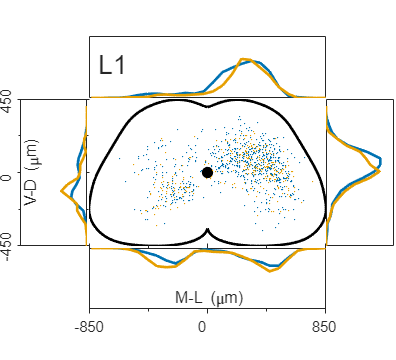

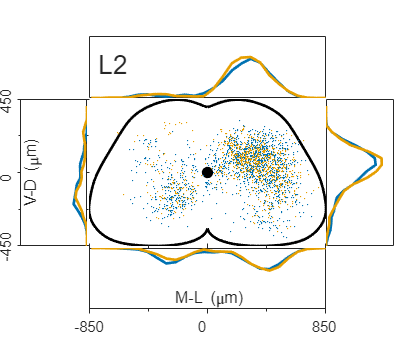

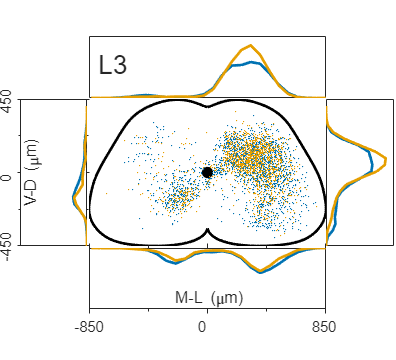

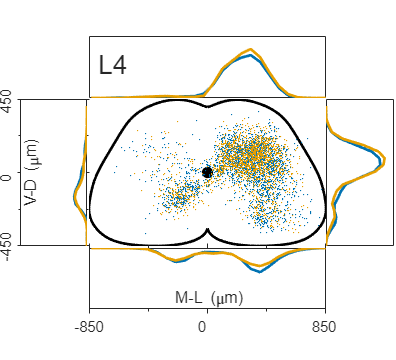

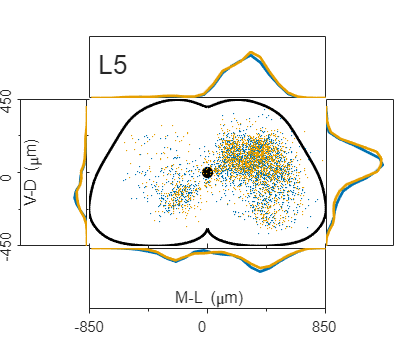

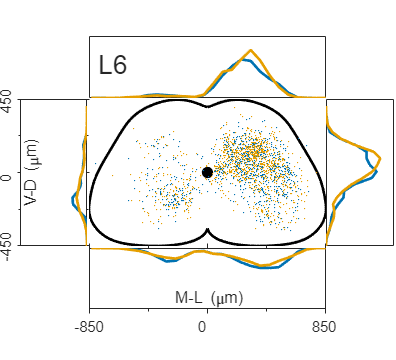

% FIgure 3 figure supplement 1
masterdir = 'F:\documents\master\data\';
masterdir_raw = 'F:\documents\master\data_raw\';
nruns = 50;


    dn = {[masterdir,'lg_high_chat\'],...
        [masterdir,'ta_high_chat\']};%,...

    ndir = length(dn);
    for i = 1:ndir
        labels{i} =  [extractBetween(dn{i},'data\','\xyz'),'--',dn{i}( strlength(dn{i})-2 :strlength(dn{i})-1) ]  ;
    end
 
% these  parameters control the appearance of the plot, with files concateanted,
% with contour, dots and with or without Mns
%%%%%%%%%%%%%%%%%%%%%%%
concat = 1;  % if concat=1 concatenates all files in directory
MNON = 0; % if 1, motoneurons are plotted as dots
MNONPROJ = 0; % if 1, motoneurons distributins are plotted on the transverse section
dotson = 1; % if dotson = 0, contours will be plotted, otherwise dots
%%%%% kernel parameters for longitudinal sections  %%%%%%
ker = [3,3];          % kernel size
res = [25,25];         % kernel resolution
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% loads tab files with sc profiles
scp = readmatrix('halfcordt.txt'); %transverse
scf = readmatrix('halfcordf.txt');  % frontal
sclv = readmatrix('halfcordf.txt');  % lateral ventral, same as frontal
scld = readmatrix('halfcordld.txt');  % lateral dorsal

[ins,mns] = poolfun(dn,concat); % ins and mns have the same dimensions 

for i = 1:ndir
    nfiles(i) = size(ins{i},2);
end

% this block splits Ins into 6 Lumbar segment, 1 being L6 and 6 being L1
segmnt = 800; % height of single segment
nseg = 6; % Number of segments
for i = 1:ndir
    for j = 1:nfiles(i)
           inseg{i}{j}{1} = ins{i}{j}(ins{i}{j}(:,3)>=segmnt,:);
           inseg{i}{j}{2} = ins{i}{j}(ins{i}{j}(:,3)>=0 & ins{i}{j}(:,3)<segmnt,:);
           inseg{i}{j}{3} = ins{i}{j}(ins{i}{j}(:,3)>=-segmnt & ins{i}{j}(:,3)<0,:);
           inseg{i}{j}{4} = ins{i}{j}(ins{i}{j}(:,3)>=-2*segmnt & ins{i}{j}(:,3)<-segmnt,:);
           inseg{i}{j}{5} = ins{i}{j}(ins{i}{j}(:,3)>=-3*segmnt & ins{i}{j}(:,3)<-2*segmnt,:);
           inseg{i}{j}{6} = ins{i}{j}(ins{i}{j}(:,3)<=-3*segmnt ,:);
    end
end

seg_label={'L6','L5','L4','L3','L2','L1',};
for i = 1:ndir
    nfiles(i) = size(ins{i},2);
end

% figure settings
nr1 = 3;               % Number of rows in panel grid
nc1 = 3;               % Number of columns in panel grid
sizex1 = 5.5;           % Absolute width of figure (in cm)
sizey1 = 5;            % Absolute height of figure (in cm)         
margx = 0.1;           % x-margin between and around panels (normalised units)
margy = 0.1;           % y-margin between and around panels (normalised units)
labelalign = 'sw';     % NESW alignment of labels
labelfsize = 18;       % Label font size
contlevlong = 5;       % contour levels for xz and yz plots
contlevtrans = 5;      % contour levels for transverse slice
inmarkersize=2;        % size of Mn marker
mnmarkersize=5;        % size of Mn marker
mnlw = 0.01;            % width of Mn edge marker
contlw =1;             % line width for contours
lwconv = 2;            % line width of convolution plots


if  isempty(mns)
    mns = [0,0,0];
    mnmarkersize=0;
    mnlw = 0;
end

   xl = [-.5,.5]; 
   yl = [-0.5,0.5];

    zl = [-4000,3000];
    plim = [0,0.15];
    plimz = [0,2e-5];
    plimlong = [0,0.2];
    
% color matrix: creates a matrix of colours scaling the primary colors to
% darker shades for increasing n of experiment. First index is directory,
% second is file
% red = [1,0,0];
% green = [0,1,0];
% blu = [0,0,1];
% ALternative set of colour for color blind people

first = [0, 114, 178]/255; %{0, 0.4471, 0.6980}  %blu = 1st directory LG
firstdark = [0, 114, 178]/450; %{0, 0.2533, 0.3956} %dark blu = 2nd directory = MG
second = [230, 159, 0]/255;  %orange = TA inhibitory
seconddark = [180/255, 100/255, 0]; %dark orange = TA excitatory
third = [0,0,1]; %unused


primarycols = {first,second,third}; % standard list, LG = BLU TA=ORANGE
%primarycols = {second,seconddark,blu}; %alternative list for plotting other
%combinations
scalecol = cell(1,ndir);
cols = cell(1,ndir);

for i = 1:ndir
   
    if nfiles(i) == 1
        scalecol{i} = 1;
    else
        scalecol{i} = linspace(1,0.5,nfiles(i));
    end
    
    for j = 1:nfiles(i)
    cols{i}{j} = primarycols{i}*scalecol{i}(j);

    end
end

gckseg = gckernel();
setKernel(gckseg,ker);
setResd(gckseg,res);
%intializes values of bins, so that all bins are the same across segments
% all x and y values can now be called as gckseg.x or gckseg.y for all
% segments

junk = gckseg.convolve([ins{1}{1}(:,1)' ; ins{1}{1}(:,2)']);
x = gckseg.x;
y = gckseg.y;

for i = 1:ndir
    for j = 1:nfiles(i)
        for k = 1:nseg
            conv_result{i}{j}{k} = gckseg.convolve([inseg{i}{j}{k}(:,1)';inseg{i}{j}{k}(:,2)']);
        end
    end
end
  
for k =nseg:-1:1
% OUTPUT FIGURE 1
f1 = figure;
set(f1,'Position',[10 10 f1.Position(3) f1.Position(4)])
h = 0;

Panels = panels([nr1, nc1], [sizex1, sizey1], 1, [margx, margy]); % Initialise panel class instance
Panels.setLabels(Panels.lbl, labelalign, labelfsize);  
Panels.tweak(2,[-0.42,0.095],[2,0.5682]);
Panels.tweak(8,[-0.42,0.36],[2,0.5682]);
Panels.tweak(4,[0.11,-0.17],[0.5682,1.36]);
Panels.tweak(6,[0.47,-0.17],[0.5682,1.36]);
Panels.tweak(5,[-0.42,-0.17],[2,1.36]);


h = 5;
dotxy = Panels.setPanel(h);
cc = plot (0,0,'ko');
    set(cc,'MarkerFaceColor',[0,0,0],'MarkerSize',8)
    hold on
plot(2*xl(2)*scp(:,1),2*yl(2)*scp(:,2),'LineWidth',lwconv,'Color','k'); %right halfcord
plot(-2*xl(2)*scp(:,1),2*yl(2)*scp(:,2),'LineWidth',lwconv,'Color','k'); %left halfcord
 for i = 1:ndir
    for j = 1:nfiles(i)
         P = conv_result{i}{j}{k};
         
         if dotson
             inpl = plot(inseg{i}{j}{k}(:,1),inseg{i}{j}{k}(:,2),'.','MarkerEdgeColor',...
                 cols{i}{j},'MarkerSize',inmarkersize);
         else
             [MM,contu] = contour(x,y,P,contlevtrans);
             set(contu,'LineColor',cols{i}{j},'LineWidth',contlw );
         end
         
         nomn = ~isempty(mns{i}{j});
         if nomn && MNON
             mnpl = plot(mns{i}{j}(:,1),mns{i}{j}(:,2),'r^', 'MarkerSize',mnmarkersize,...
                 'MarkerFaceColor',cols{i}{j},'MarkerEdgeColor','k','LineWidth',mnlw);
         else
             
         end
            ax = gca;
         set (ax, 'xlim',xl, 'ylim',yl,'Visible','off','XTick',[],'YTick',[])
 box off
    end
 end

h = 2;
top = Panels.setPanel(h);
for i = 1:ndir
    for j = 1:nfiles(i)
        P = conv_result{i}{j}{k};

        pt = sum( P(y>=0,:),1);
        topplot = plot(x,pt);
        %sum(pt)
        hold on
        set(topplot,'color',cols{i}{j}, 'LineWidth',lwconv);
        ax = gca;
        set(ax,'xlim', xl,'ylim',plim,'XTick',[],'YTick',[])
        set(ax.XLabel,'Interpreter','tex');
        ax.XLabel.String = seg_label{k};
        ax.XLabel.Position = [0.8*xl(1), 0.8*plim(2)];
        ax.XAxis.FontSize = 18;
        ax.XAxis.FontName = 'arial';

    end
end

h = 6;
right = Panels.setPanel(h);
for i = 1:ndir
    for j = 1:nfiles(i)
         P = conv_result{i}{j}{k};
        
             pr = sum( P(:,x>=0),2);
             rightplot = plot(pr,y);
             hold on
             if MNONPROJ
                 xmn = gckmn{i}{j}.x;
                 ymn = gckmn{i}{j}.y;
                 Pmn = gckmn{i}{j}.P;
                 prmn = sum( Pmn(:,:),2);
                 rightplotmn = plot(prmn,ymn);
                 set(rightplotmn,'color',cols{i}{j}, 'LineStyle',':','LineWidth',lwconv);
             else
             end
             set(rightplot,'color',cols{i}{j}, 'LineWidth',lwconv);
             ax = gca;
             set(ax,'xlim',plim,'ylim', yl,'XTick',[],'YTick',[])   ;
         

    end
end

h = 4;
left = Panels.setPanel(h);
for i = 1:ndir
    for j = 1:nfiles(i)   
         P = conv_result{i}{j}{k};
         
             pl = sum( P(:,x<0),2);
             leftplot = plot(pl,y);
             hold on
             set(leftplot,'color',cols{i}{j}, 'LineWidth',lwconv);
             ax = gca;
             set(ax,'ylim', yl,'xlim',plim,'xdir','reverse','XTick',[],...
             'YTick',[-0.5,0, 0.5],'YTickLabel',[-450,0,450],'YTickLabelRotation',90,...
         'TickLabelInterpreter','tex')   ;
         set(ax.YLabel,'Interpreter','tex');
         ax.YLabel.String = 'V-D (\mum)';
         ax.YLabel.Position = [0.1 4.7684e-07];
         ax.YAxis.FontSize = 11;
         ax.YAxis.FontName = 'arial';
         ax.YAxis.MinorTick = 'on';
         ax.YAxis.MinorTickValues = [-0.5,-0.25,0,0.25,0.5]; 
         ax.YAxis.TickDirection = 'out';
         ax.YAxis.TickLength = [0.0200 0.0250];
         

    end
end

h = 8;
bot = Panels.setPanel(h);
for i = 1:ndir
    for j = 1:nfiles(i)   
         P = conv_result{i}{j}{k};
         
             pb = sum( P(y<0,:),1);
             botplot = plot(x,pb);
             %sum(pb)
             hold on
             
             if MNONPROJ
                 x = gckmn{i}{j}.x;
                 y = gckmn{i}{j}.y;
                 P = gckmn{i}{j}.P;
                 pb = sum( P(:,:),1);
                 botplotmn = plot(x,pb);
                 set(botplotmn,'color',cols{i}{j}, 'LineStyle',':','LineWidth',lwconv);
             else
             end
             
             set(botplot,'color',cols{i}{j}, 'LineWidth',lwconv);
             ax = gca;
             set(ax,'xlim', xl,'ylim',plim,'ydir','reverse',...
             'XTick',[-0.5,0, 0.5],'XTickLabel',[-850,0,850],'YTick',[])   ; 
         set(ax.XLabel,'Interpreter','tex');
         ax.XLabel.String = 'M-L (\mum)';
         ax.XLabel.Position = [0.0065 0.1];
         ax.XAxis.FontSize = 11;
         ax.XAxis.FontName = 'arial';
         ax.XAxis.MinorTick = 'on';
         ax.XAxis.MinorTickValues = [-0.5,-0.25,0,0.25,0.5]; 
         ax.XAxis.TickDirection = 'out';
         ax.XAxis.TickLength = [0.0200 0.0250];

    end
end

Panels.addPanels();
end

**Figure 3 figure supplement 1**: The distribution of premotor interneurons is similar throughout the lumbar spinal cord: data pooled from 18 experiments (11 LG and 7 TA injections) show that within each lumbar segment, from L1 to L6, the distributions of LG and TA premotor interneurons are overlapping.

# Figure 3-figure supplement 2

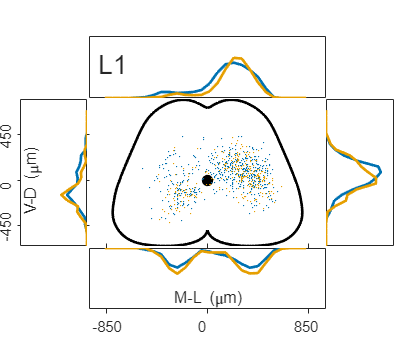

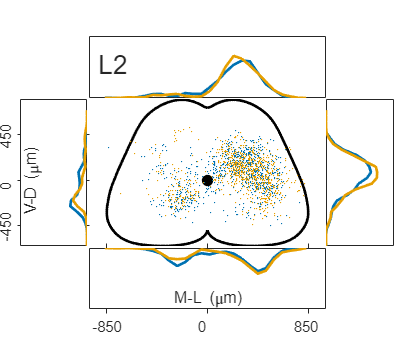

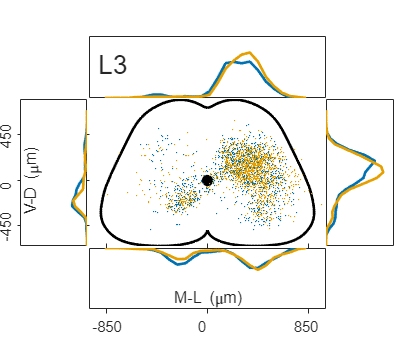

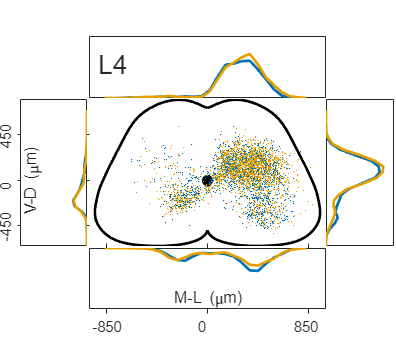

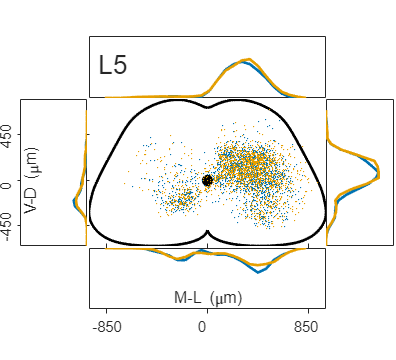

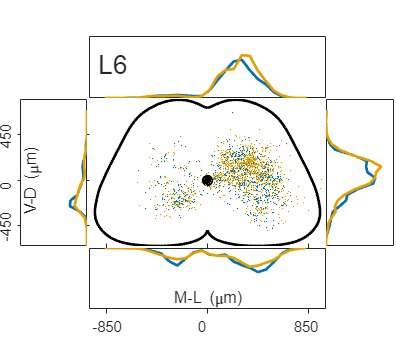


% Figure 3 figure supplement 2

%close all
clearvars -except masterdir masterdir_raw nruns

    dn = {[masterdir_raw,'lg_high_chat\'],...
        [masterdir_raw,'ta_high_chat\']};%,...

    ndir = length(dn);
    for i = 1:ndir
        labels{i} =  [extractBetween(dn{i},'data\','\xyz'),'--',dn{i}( strlength(dn{i})-2 :strlength(dn{i})-1) ]  ;
    end
 
% these  parameters control the appearance of the plot, with files concateanted,
% with contour, dots and with or without Mns
%%%%%%%%%%%%%%%%%%%%%%%
concat = 1;  % if concat=1 concatenates all files in directory
MNON = 0; % if 1, motoneurons are plotted as dots
MNONPROJ = 0; % if 1, motoneurons distributins are plotted on the transverse section
dotson = 1; % if dotson = 0, contours will be plotted, otherwise dots
%%%%% kernel parameters for longitudinal sections  %%%%%%
ker = [3,3];          % kernel size
res = [25,25];         % kernel resolution
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% loads tab files with sc profiles
scp_raw = readmatrix('halfcordt.txt'); %transverse
scf = readmatrix('halfcordf.txt');  % frontal
sclv = readmatrix('halfcordf.txt');  % lateral ventral, same as frontal
scld = readmatrix('halfcordld.txt');  % lateral dorsal

[ins,mns] = poolfun(dn,concat); % ins and mns have the same dimensions 

for i = 1:ndir
    nfiles(i) = size(ins{i},2);
end

% this block splits Ins into 6 Lumbar segment, 1 being L6 and 6 being L1
segmnt = 800; % height of single segment
nseg = 6; % Number of segments
for i = 1:ndir
    for j = 1:nfiles(i)
           inseg{i}{j}{1} = ins{i}{j}(ins{i}{j}(:,3)>=segmnt,:);
           inseg{i}{j}{2} = ins{i}{j}(ins{i}{j}(:,3)>=0 & ins{i}{j}(:,3)<segmnt,:);
           inseg{i}{j}{3} = ins{i}{j}(ins{i}{j}(:,3)>=-segmnt & ins{i}{j}(:,3)<0,:);
           inseg{i}{j}{4} = ins{i}{j}(ins{i}{j}(:,3)>=-2*segmnt & ins{i}{j}(:,3)<-segmnt,:);
           inseg{i}{j}{5} = ins{i}{j}(ins{i}{j}(:,3)>=-3*segmnt & ins{i}{j}(:,3)<-2*segmnt,:);
           inseg{i}{j}{6} = ins{i}{j}(ins{i}{j}(:,3)<=-3*segmnt ,:);
    end
end
seg_label={'L6','L5','L4','L3','L2','L1',};
for i = 1:ndir
    nfiles(i) = size(ins{i},2);
end

% figure settings
nr1 = 3;               % Number of rows in panel grid
nc1 = 3;               % Number of columns in panel grid
sizex1 = 5.5;           % Absolute width of figure (in cm)
sizey1 = 5;            % Absolute height of figure (in cm)         
margx = 0.1;           % x-margin between and around panels (normalised units)
margy = 0.1;           % y-margin between and around panels (normalised units)
labelalign = 'sw';     % NESW alignment of labels
labelfsize = 18;       % Label font size
contlevlong = 5;       % contour levels for xz and yz plots
contlevtrans = 5;      % contour levels for transverse slice
inmarkersize=2;        % size of Mn marker
mnmarkersize=5;        % size of Mn marker
mnlw = 0.01;            % width of Mn edge marker
contlw =1;             % line width for contours
lwconv = 2;            % line width of convolution plots


if  isempty(mns)
    mns = [0,0,0];
    mnmarkersize=0;
    mnlw = 0;
end
scale = contains(dn{1},'norm');
if scale
   xl = [-.5,.5]; 
   yl = [-0.5,0.5];
else
    lseg = [950,1000,950,900,850,800];
    xl = [-1000,1000];
    yl = [-650,800];
    % scale spinal cord profile scp_raw for plotting raw data 
   pp =scp_raw(:,2)>0;
   nn = scp_raw(:,2)<=0;
   y_cord_pos = 2*yl(2)*scp_raw(pp,2);
   y_cord_neg = -2*yl(1)*scp_raw(nn,2);
   y_cord = vertcat(y_cord_pos,y_cord_neg);
   scp = horzcat(scp_raw(:,1),y_cord);

end
    zl = [-4000,3000];
    plim = [0,0.15];
    plimz = [0,2e-5];
    plimlong = [0,0.2];
    
% color matrix: creates a matrix of colours scaling the primary colors to
% darker shades for increasing n of experiment. First index is directory,
% second is file
% red = [1,0,0];
% green = [0,1,0];
% blu = [0,0,1];
% ALternative set of colour for color blind people

first = [0, 114, 178]/255; %{0, 0.4471, 0.6980}  %blu = 1st directory LG
firstdark = [0, 114, 178]/450; %{0, 0.2533, 0.3956} %dark blu = 2nd directory = MG
second = [230, 159, 0]/255;  %orange = TA inhibitory
seconddark = [180/255, 100/255, 0]; %dark orange = TA excitatory
third = [0,0,1]; %unused


primarycols = {first,second,third}; % standard list, LG = BLU TA=ORANGE
%primarycols = {second,seconddark,blu}; %alternative list for plotting other
%combinations
scalecol = cell(1,ndir);
cols = cell(1,ndir);

for i = 1:ndir
   
    if nfiles(i) == 1
        scalecol{i} = 1;
    else
        scalecol{i} = linspace(1,0.5,nfiles(i));
    end
    
    for j = 1:nfiles(i)
    cols{i}{j} = primarycols{i}*scalecol{i}(j);

    end
end

gckseg = gckernel();
setKernel(gckseg,ker);
setResd(gckseg,res);
%intializes values of bins, so that all bins are the same across segments
% all x and y values can now be called as gckseg.x or gckseg.y for all
% segments

junk = gckseg.convolve([ins{1}{1}(:,1)' ; ins{1}{1}(:,2)']);
x = gckseg.x;
y = gckseg.y;

for i = 1:ndir
    for j = 1:nfiles(i)
        for k = 1:nseg
            conv_result{i}{j}{k} = gckseg.convolve([inseg{i}{j}{k}(:,1)';inseg{i}{j}{k}(:,2)']);
        end
    end
end
  
for k =nseg:-1:1
% OUTPUT FIGURE 1
f1 = figure;
set(f1,'Position',[10 10 f1.Position(3) f1.Position(4)])
h = 0;
Panels = panels([nr1, nc1], [sizex1, sizey1], 1, [margx, margy]); % Initialise panel class instance
Panels.setLabels(Panels.lbl, labelalign, labelfsize);  
Panels.tweak(2,[-0.42,0.095],[2,0.5682]);
Panels.tweak(8,[-0.42,0.36],[2,0.5682]);
Panels.tweak(4,[0.11,-0.17],[0.5682,1.36]);
Panels.tweak(6,[0.47,-0.17],[0.5682,1.36]);
Panels.tweak(5,[-0.42,-0.17],[2,1.36]);


h = 5;
dotxy = Panels.setPanel(h);
cc = plot (0,0,'ko');
    set(cc,'MarkerFaceColor',[0,0,0],'MarkerSize',8)
    hold on
plot(2*lseg(k)*scp(:,1),scp(:,2),'LineWidth',lwconv,'Color','k'); %right halfcord
plot(-2*lseg(k)*scp(:,1),scp(:,2),'LineWidth',lwconv,'Color','k'); %left halfcord
 for i = 1:ndir
    for j = 1:nfiles(i)
         P = conv_result{i}{j}{k};
         
         if dotson
             inpl = plot(inseg{i}{j}{k}(:,1),inseg{i}{j}{k}(:,2),'.','MarkerEdgeColor',...
                 cols{i}{j},'MarkerSize',inmarkersize);
         else
             [MM,contu] = contour(x,y,P,contlevtrans);
             set(contu,'LineColor',cols{i}{j},'LineWidth',contlw );
         end
         
         nomn = ~isempty(mns{i}{j});
         if nomn && MNON
             mnpl = plot(mns{i}{j}(:,1),mns{i}{j}(:,2),'r^', 'MarkerSize',mnmarkersize,...
                 'MarkerFaceColor',cols{i}{j},'MarkerEdgeColor','k','LineWidth',mnlw);
         else
             
         end
            ax = gca;
         set (ax, 'xlim',xl, 'ylim',yl,'Visible','off','XTick',[],'YTick',[])
 box off
    end
 end

h = 2;
top = Panels.setPanel(h);
for i = 1:ndir
    for j = 1:nfiles(i)
        P = conv_result{i}{j}{k};

        pt = sum( P(y>=0,:),1);
        topplot = plot(x,pt);
        %sum(pt)
        hold on
        set(topplot,'color',cols{i}{j}, 'LineWidth',lwconv);
        ax = gca;
        set(ax,'xlim', xl,'ylim',plim,'XTick',[],'YTick',[])
        set(ax.XLabel,'Interpreter','tex');
        ax.XLabel.String = seg_label{k};
        ax.XLabel.Position = [0.8*xl(1), 0.8*plim(2)];
        ax.XAxis.FontSize = 18;
        ax.XAxis.FontName = 'arial';


    end
end

h = 6;
right = Panels.setPanel(h);
for i = 1:ndir
    for j = 1:nfiles(i)
         P = conv_result{i}{j}{k};
        
             pr = sum( P(:,x>=0),2);
             rightplot = plot(pr,y);
             hold on
             if MNONPROJ
                 xmn = gckmn{i}{j}.x;
                 ymn = gckmn{i}{j}.y;
                 Pmn = gckmn{i}{j}.P;
                 prmn = sum( Pmn(:,:),2);
                 rightplotmn = plot(prmn,ymn);
                 set(rightplotmn,'color',cols{i}{j}, 'LineStyle',':','LineWidth',lwconv);
             else
             end
             set(rightplot,'color',cols{i}{j}, 'LineWidth',lwconv);
             ax = gca;
             set(ax,'xlim',plim,'ylim', yl,'XTick',[],'YTick',[])   ;
         

    end
end

h = 4;
left = Panels.setPanel(h);
for i = 1:ndir
    for j = 1:nfiles(i)   
         P = conv_result{i}{j}{k};
         
             pl = sum( P(:,x<0),2);
             leftplot = plot(pl,y);
             hold on
             set(leftplot,'color',cols{i}{j}, 'LineWidth',lwconv);
             ax = gca;
             set(ax,'ylim', yl,'xlim',plim,'xdir','reverse','XTick',[],...
             'YTick',[-450,0, 450],'YTickLabel',[-450,0,450],'YTickLabelRotation',90,...
         'TickLabelInterpreter','tex')   ;
         set(ax.YLabel,'Interpreter','tex');
         ax.YLabel.String = 'V-D (\mum)';
         ax.YLabel.Position = [0.1 4.7684e-07];
         ax.YAxis.FontSize = 11;
         ax.YAxis.FontName = 'arial';
         ax.YAxis.MinorTick = 'on';
         ax.YAxis.MinorTickValues = [-0.5,-0.25,0,0.25,0.5]; 
         ax.YAxis.TickDirection = 'out';
         ax.YAxis.TickLength = [0.0200 0.0250];
         

    end
end

h = 8;
bot = Panels.setPanel(h);
for i = 1:ndir
    for j = 1:nfiles(i)   
         P = conv_result{i}{j}{k};
         
             pb = sum( P(y<0,:),1);
             botplot = plot(x,pb);
             %sum(pb)
             hold on
             
             if MNONPROJ
                 x = gckmn{i}{j}.x;
                 y = gckmn{i}{j}.y;
                 P = gckmn{i}{j}.P;
                 pb = sum( P(:,:),1);
                 botplotmn = plot(x,pb);
                 set(botplotmn,'color',cols{i}{j}, 'LineStyle',':','LineWidth',lwconv);
             else
             end
             
             set(botplot,'color',cols{i}{j}, 'LineWidth',lwconv);
             ax = gca;
             set(ax,'xlim', xl,'ylim',plim,'ydir','reverse',...
             'XTick',[-850,0, 850],'XTickLabel',[-850,0,850],'YTick',[])   ; 
         set(ax.XLabel,'Interpreter','tex');
         ax.XLabel.String = 'M-L (\mum)';
         ax.XLabel.Position = [0.0065 0.1];
         ax.XAxis.FontSize = 11;
         ax.XAxis.FontName = 'arial';
         ax.XAxis.MinorTick = 'on';
         ax.XAxis.MinorTickValues = [-0.5,-0.25,0,0.25,0.5]; 
         ax.XAxis.TickDirection = 'out';
         ax.XAxis.TickLength = [0.0200 0.0250];

    end
end

Panels.addPanels();
end

***Figure 3 figure supplement 2****: Same data as in Figure 3-figure supplement 1 shown before normalization procedures, with idealized spinal cord section scaled to the average size of each segment. Using the raw coordinates, the distribution of LG and TA premotor interneurons are consistently overlapping throughout the lumbar segments.*

# Figure 3-figure supplement 3

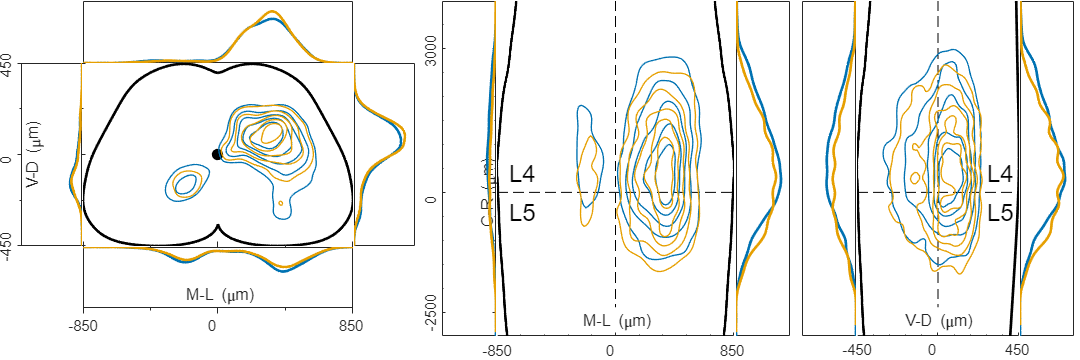

% Figure 3 figure supplement 3
masterdir = 'F:\documents\master\data\';
clearvars -except masterdir masterdir_raw nruns
ExpTypeString = {'chat', 'olig2','aav_wt',...
    'aav_chat','prv'};
MuscleType = {'lg','mg','gs','ta','pl'};
MuscleTypeSecond = {'nil', 'lg','mg','gs','ta','pl'};
ext = 'xlsx';
ExpType = {'chat'}; 
firstmuscle = {'lg'};
secondmuscle = {'ta'};
titer = 'high'; % can be 'high' or 'low'
concat = 1;
% Defines folders for each muscles and number of muscles

firstmuscledir = [masterdir,firstmuscle{1},'_',titer,'_',ExpType{1},'\'];
if ~isfolder(firstmuscledir)
    disp ('Please pick another first muscle: LG, MG and PL were injected only for experiments on ChAT-PhiGT, GS and TA were injected in all other experiments')
    firstfiles = [];
    return
else
    firstfiles = dir([firstmuscledir,'*.',ext]);
end

yes_second = ~contains(secondmuscle,'nil');

if yes_second
    secondmuscledir = [masterdir,secondmuscle{1},'_',titer,'_',ExpType{1},'\'];
    if ~isfolder(secondmuscledir)
        disp ('Please pick another second muscle: LG, MG and PL were injected only for experiments on ChAT-PhiGT, GS and TA were injected in all 9other experiments')
        secondfiles = [];
        return
    else
        secondfiles = dir([secondmuscledir,'*.',ext]);
    end
else
end

% [fnfirst,pathfirst] =  uigetfile([firstmuscledir,'*.xlsx'],'Select One or more files for first muscle', ...
%            'MultiSelect', 'on');
 fnfirst = {firstfiles(:).name}; %picks all files from first directory
 pathfirst = firstmuscledir;

if yes_second
%     [fnsecond,pathsecond] =  uigetfile([secondmuscledir,'*.xlsx'],'Select One or more files for second muscle', ...
%             'MultiSelect', 'on');    
    fnsecond = {secondfiles(:).name}; %picks all files from second directory
    pathsecond = secondmuscledir;
    nfiles_ = [length(string(fnfirst)), length(string(fnsecond))];
    dn = {pathfirst,pathsecond};
else   
    nfiles_ = length(string(fnfirst)); %here and above: string must be used to accommodate for single files
    dn = {pathfirst};
end
ndir = length(dn);

% declares all cell and matrix variables
ins = cell(1,ndir);
mns = cell(1,ndir);
gckin = cell(1,ndir);
gckmn = cell(1,ndir);
gckinxz = cell(1,ndir);
gckmnxz = cell(1,ndir);
gckinyz = cell(1,ndir);
gckmnyz = cell(1,ndir);

nfiles = [];
ptpeak = [];
prpeak = [];
plpeak = [];
pbpeak = [];
peakcontraxz = [];
peakipsixz = [];
peakcontrayz = [];
peakipsiyz = [];

% First index is the directory, second is file the extra i is to
% accommodate for choice of single files in order to keep the string format

if nfiles_(1)==1
    ins_{1}{1} = readmatrix([dn{1},fnfirst], 'Sheet',1);
    mns_{1}{1} = readmatrix([dn{1},fnfirst], 'Sheet',2);
else
    for j = 1:nfiles_(1)
        ins_{1}{j} = readmatrix([dn{1},fnfirst{j}], 'Sheet',1);
        mns_{1}{j} = readmatrix([dn{1},fnfirst{j}], 'Sheet',2);
    end
end

if size(nfiles_,2)==2
    if nfiles_(2) ==1
        ins_{2}{1} = readmatrix([dn{2},fnsecond], 'Sheet',1);
        mns_{2}{1} = readmatrix([dn{2},fnsecond], 'Sheet',2);
    else
        for j = 1:nfiles_(2)
            ins_{2}{j} = readmatrix([dn{2},fnsecond{j}], 'Sheet',1);
            mns_{2}{j} = readmatrix([dn{2},fnsecond{j}], 'Sheet',2);
        end
    end
else
end



if concat == 1
    for  i = 1:ndir
        % the extra {1} is to make it compatible with codes using
        % two indexes if files are not concatenated
        ins{i}{1} = vertcat(ins_{i}{:});
        mns{i}{1} = vertcat(mns_{i}{:});
    end
else
    for i = 1:ndir
        for j = 1:nfiles_(i)
            ins{i}{j} = ins_{i}{j};
            mns{i}{j} = mns_{i}{j};
        end
    end
end

% rewrite nfiles after concatenation
for i = 1:ndir
    nfiles(i) = size(ins{i},2);
end

%[ins,mns] = poolfun(dn,concat); % ins and mns have the same dimensions 

MNON = false; MNONPROJ = false;
qq = 6;
dotson = 0;
contlevlong = 5;
contlevtrans = 5;


% figure settings
autoscale = 1; % Set autoscale on Y axis of interneurons densities
ker = [5,5];          % kernel size
res = [100,100];         % kernel resolution

nr1 = 3;               % Number of rows in panel grid
nc1 = 9;               % Number of columns in panel grid
sizex1 = 15;           % Absolute width of figure (in cm)
sizey1 = 5;            % Absolute height of figure (in cm)         
margx = 0.1;           % x-margin between and around panels (normalised units)
margy = 0.1;           % y-margin between and around panels (normalised units)
labelalign = 'sw';     % NESW alignment of labels
labelfsize = 18;       % Label font size
% contlevlong = 5;       % contour levels for xz and yz plots
% contlevtrans = 5;      % contour levels for transverse slice
inmarkersize=2;        % size of Mn marker
mnmarkersize=5;        % size of Mn marker
mnlw = 0.01;            % width of Mn edge marker
contlw =1;             % line width for contours
lwconv = 2;            % line width of convolution plots

% loads tab files with sc profiles
scp = readmatrix('halfcordt.txt'); %transverse
scf = readmatrix('halfcordf.txt');  % frontal
sclv = readmatrix('halfcordf.txt');  % lateral ventral, same as frontal
scld = readmatrix('halfcordld.txt');  % lateral dorsal

if  isempty(mns)
    mns = [0,0,0];
    mnmarkersize=0;
    mnlw = 0;
end

   xl = [-.5,.5]; 
   yl = [-0.5,0.5];

    zl = [-4000,3000];
    plim = [0,0.01]; % these settings are overridden if autoscale is on
    plimz = [0,2e-5];
    plimlong = [0,0.23];
    
% color matrix: creates a matrix of colours scaling the primary colors to
% darker shades for increasing n of experiment. First index is directory,
% second is file

first = [0, 114, 178]/255; %{0, 0.4471, 0.6980}  %blu = 1st directory LG
firstdark = [0, 114, 178]/450; %{0, 0.2533, 0.3956} %dark blu = 2nd directory = MG
second = [230, 159, 0]/255;  %{0.9020, 0.6235,0} orange = TA inhibitory
seconddark = [180/255, 100/255, 0]; %{0.7059, 0.3922, 0} dark orange = TA excitatory
third = [0,0,1];

switch string(firstmuscle)
    case 'lg'
        primarycols{1} = first;
    case 'mg'
        primarycols{1} = firstdark;
    case 'gs'
        primarycols{1} = first;
    case 'ta'
        primarycols{1} = second;
    case 'pl'
        primarycols{1} = seconddark;
end

if yes_second
    switch string(secondmuscle)
        case 'lg'
            primarycols{2} = first
        case 'mg'
            primarycols{2} = firstdark;
        case 'gs'
            primarycols{2} = first;
        case 'ta'
            primarycols{2} = second;
        case 'pl'
            primarycols{2} = seconddark;
    end
else
    primarycols{2} = second;
end
primarycols{3} = third;

%primarycols = {first,second,third}; % standard list, GS=green, TA=red
scalecol = cell(1,ndir);
cols = cell(1,ndir);

for i = 1:ndir
   
    if nfiles(i) == 1
        scalecol{i} = 1;
    else
        scalecol{i} = linspace(1,0.5,nfiles(i));
    end
    
    for j = 1:nfiles(i)
    cols{i}{j} = primarycols{i}*scalecol{i}(j);

    end
end

for i = 1:ndir
    for j = 1:nfiles(i)
        gckin{i}{j} = gckernel();
        gckmn{i}{j} = gckernel();
        gckinxz{i}{j} = gckernel();
        gckmnxz{i}{j} = gckernel();
        gckinyz{i}{j} = gckernel();
        gckmnyz{i}{j} = gckernel();
      
    end
end
  
for i = 1:ndir
    for j = 1:nfiles(i)
        gckin{i}{j}.setData([ins{i}{j}(:,1)'; ins{i}{j}(:,2)'], [std(ins{i}{j}(:,1))/qq,std(ins{i}{j}(:,1))/qq]);
        gckin{i}{j}.convolve([ins{i}{j}(:,1)'; ins{i}{j}(:,2)']);
        %nomn = ~isempty(mns{i}{j}); %REPLACE NOMN WITH size(mns{i}{j}) for cases with 1 Mn only
        nmn = size(mns{i}{j},1);
        if nmn>1
            gckmn{i}{j}.convolve([mns{i}{j}(:,1)'; mns{i}{j}(:,2)']);
            gckmnxz{i}{j}.convolve([mns{i}{j}(:,1)'; mns{i}{j}(:,3)']);
        else
            
        end
        setKernel(gckin{i}{j},ker);
        setResd(gckin{i}{j},res);
        setKernel(gckinxz{i}{j},ker);
        setResd(gckinxz{i}{j},res);
        setKernel(gckinyz{i}{j},ker);
        setResd(gckinyz{i}{j},res);
        gckinxz{i}{j}.setData([ins{i}{j}(:,1)'; ins{i}{j}(:,3)'],[std(ins{i}{j}(:,1))/qq,std(ins{i}{j}(:,1))/qq]);
        gckinyz{i}{j}.setData([ins{i}{j}(:,2)'; ins{i}{j}(:,3)'],[std(ins{i}{j}(:,1))/qq,std(ins{i}{j}(:,1))/qq]);
        gckinxz{i}{j}.convolve([ins{i}{j}(:,1)'; ins{i}{j}(:,3)']);
        gckinyz{i}{j}.convolve([ins{i}{j}(:,2)'; ins{i}{j}(:,3)']);
        
    end
end

% OUTPUT FIGURE 1
f1 = figure;
%set(f1,'Position',[10 10 f1.Position(3) f1.Position(4)]);
set(f1,'Position',[10 10 1500 500]);
h = 0;
% aa = annotation('line', [0.14,0.25],[0.05,0.05]);
% aa.LineWidth = lwconv;
% annotation('textbox', [0.165,0.11,0.05,0.03],'String','1 mm','LineStyle','none','FontSize',15,'FitBoxToText','on');
% annotation('doublearrow', [0.805,0.935],[0.05,0.05]);
% annotation('textbox', [0.815,0.1,0.03,0.03],'String','V','LineStyle','none','FontSize',15,'FitBoxToText','on');
% annotation('textbox', [0.895,0.1,0.03,0.03],'String','D','LineStyle','none','FontSize',15,'FitBoxToText','on');
Panels = panels([nr1, nc1], [sizex1, sizey1], 1, [margx, margy]); % Initialise panel class instance
Panels.setLabels(Panels.lbl, labelalign, labelfsize);  

Panels.tweak(2,[-0.4,0.42],[2.5,0.5682]);
Panels.tweak(20,[-0.4,0.37],[2.5,0.5682]);
Panels.tweak(10,[0.14,-0.17],[0.5682,1.7]);
Panels.tweak(12,[1.0,-0.17],[0.5682,1.7]);
Panels.tweak(11,[-0.4,-0.17],[2.5,1.7]);
Panels.tweak(14,[0.1,-1.],[2.2,3.1]);
Panels.tweak(13,[0.7,-1.],[0.5,3.1]);
Panels.tweak(15,[1.2,-1.],[0.5,3.1]);
Panels.tweak(17,[0.1,-1.0],[1.5,3.1]);
Panels.tweak(16,[0.7,-1.0],[0.5,3.1]);
Panels.tweak(18,[0.5,-1.0],[0.5,3.1]);


h = 11;
dotxy = Panels.setPanel(h);
cc = plot (0,0,'ko');
    set(cc,'MarkerFaceColor',[0,0,0],'MarkerSize',8)
    hold on
plot(2*xl(2)*scp(:,1),2*yl(2)*scp(:,2),'LineWidth',lwconv,'Color','k'); %right halfcord
plot(-2*xl(2)*scp(:,1),2*yl(2)*scp(:,2),'LineWidth',lwconv,'Color','k'); %left halfcord
 for i = 1:ndir
    for j = 1:nfiles(i)
         x = gckin{i}{j}.x;
         y = gckin{i}{j}.y;
         P = gckin{i}{j}.P;
         
         if dotson
             inpl = plot(ins{i}{j}(:,1),ins{i}{j}(:,2),'.','MarkerEdgeColor',...
                 cols{i}{j},'MarkerSize',inmarkersize);
         else
             [MM,contu] = contour(x,y,P,contlevtrans);
             set(contu,'LineColor',cols{i}{j},'LineWidth',contlw );
         end
         
         nomn = ~isempty(mns{i}{j});
         if nomn && MNON
             mnpl = plot(mns{i}{j}(:,1),mns{i}{j}(:,2),'r^', 'MarkerSize',mnmarkersize,...
                 'MarkerFaceColor',cols{i}{j},'MarkerEdgeColor','k','LineWidth',mnlw);
         else
             
         end
            ax = gca;
         set (ax, 'xlim',xl, 'ylim',yl,'Visible','off','XTick',[],'YTick',[])
 box off
    end
 end

h = 2;
top = Panels.setPanel(h);
for i = 1:ndir
    for j = 1:nfiles(i)
         x = gckin{i}{j}.x;
         y = gckin{i}{j}.y;
         P = gckin{i}{j}.P;
         pt = sum( P(y>=0,:),1);
         ptpeak(i,j) = max(max(pt));
         topplot = plot(x,pt);
         %sum(pt)
         hold on
         set(topplot,'color',cols{i}{j}, 'LineWidth',lwconv);
         ax = gca;
         set(ax,'xlim', xl,'ylim',plim,'XTick',[],'YTick',[])         
 
    end
end

h = 12;
right = Panels.setPanel(h);
for i = 1:ndir
    for j = 1:nfiles(i)
         x = gckin{i}{j}.x;
         y = gckin{i}{j}.y;
         P = gckin{i}{j}.P;
         pr = sum( P(:,x>=0),2);
         prpeak(i,j) = max(max(pr));
         rightplot = plot(pr,y);
         hold on
         if MNONPROJ
             xmn = gckmn{i}{j}.x;
             ymn = gckmn{i}{j}.y;
             Pmn = gckmn{i}{j}.P;
             prmn = sum( Pmn(:,:),2);
             rightplotmn = plot(prmn,ymn);
             set(rightplotmn,'color',cols{i}{j}, 'LineStyle',':','LineWidth',lwconv);
         else
         end
         set(rightplot,'color',cols{i}{j}, 'LineWidth',lwconv);
         ax = gca;
         set(ax,'xlim',plim,'ylim', yl,'XTick',[],'YTick',[])   ;     

    end
end

h = 10;
left = Panels.setPanel(h);
for i = 1:ndir
    for j = 1:nfiles(i)   
         x = gckin{i}{j}.x;
         y = gckin{i}{j}.y;
         P = gckin{i}{j}.P;
         pl = sum( P(:,x<0),2);
         plpeak(i,j) = max(max(pl));
         leftplot = plot(pl,y);
         hold on
         set(leftplot,'color',cols{i}{j}, 'LineWidth',lwconv);
         ax = gca;
         set(ax,'ylim', yl,'xlim',plim,'xdir','reverse','XTick',[],...
             'YTick',[-0.5,0, 0.5],'YTickLabel',[-450,0,450],'YTickLabelRotation',90,...
         'TickLabelInterpreter','tex')   ;
         set(ax.YLabel,'Interpreter','tex');
         ax.YLabel.String = 'V-D (\mum)';
         ax.YLabel.Position = [0.0065 4.7684e-07];
         ax.YAxis.FontSize = 11;
         ax.YAxis.FontName = 'arial';
         ax.YAxis.MinorTick = 'on';
         ax.YAxis.MinorTickValues = [-0.5,-0.25,0,0.25,0.5]; 
         ax.YAxis.TickDirection = 'out';
         ax.YAxis.TickLength = [0.0200 0.0250];
    end
end

h = 20;
bot = Panels.setPanel(h);
for i = 1:ndir
    for j = 1:nfiles(i)   
         x = gckin{i}{j}.x;
         y = gckin{i}{j}.y;
         P = gckin{i}{j}.P;
         pb = sum( P(y<0,:),1);
         pbpeak(i,j) = max(max(pb));
         botplot = plot(x,pb);
         %sum(pb)
         hold on
        
         if MNONPROJ
             x = gckmn{i}{j}.x;
             y = gckmn{i}{j}.y;
             P = gckmn{i}{j}.P;
             pb = sum( P(:,:),1);
             botplotmn = plot(x,pb);
             set(botplotmn,'color',cols{i}{j}, 'LineStyle',':','LineWidth',lwconv);
         else
         end
         
         set(botplot,'color',cols{i}{j}, 'LineWidth',lwconv);
         ax = gca;
         set(ax,'xlim', xl,'ylim',plim,'ydir','reverse',...
             'XTick',[-0.5,0, 0.5],'XTickLabel',[-850,0,850],'YTick',[])   ; 
         set(ax.XLabel,'Interpreter','tex');
         ax.XLabel.String = 'M-L (\mum)';
         ax.XLabel.Position = [0.0065 0.006];
         ax.XAxis.FontSize = 11;
         ax.XAxis.FontName = 'arial';
         ax.XAxis.MinorTick = 'on';
         ax.XAxis.MinorTickValues = [-0.5,-0.25,0,0.25,0.5]; 
         ax.XAxis.TickDirection = 'out';
         ax.XAxis.TickLength = [0.0200 0.0250];

    end
end

% longitudinal xz

h = 13;
 contraxz = Panels.setPanel(h);
 for i = 1:ndir
    for j = 1:nfiles(i)
         x = gckinxz{i}{j}.x;
         y = gckinxz{i}{j}.y;
         P = gckinxz{i}{j}.P;
         pcontraxz = sum( P(:,x<0),2);
         plotcontra = plot(pcontraxz,y);
         peakcontraxz(i,j) = max(max(pcontraxz));
         hold on
         set (plotcontra,'color',cols{i}{j}, 'LineWidth',lwconv)
         ax  = gca;
         set (ax, 'ylim',zl,'xlim',plimlong,'xdir','reverse','ydir','reverse',...
             'XTick',[],'YTick',[-3000,0,2500],'YTickLabel',[3000,0,-2500],...
             'YTickLabelRotation',90)
         set(ax.YLabel,'Interpreter','tex');
         ax.YLabel.String = 'C-R (\mum)';
          ax.YLabel.Position = [-0.0015 4.7684e-07];
%         ax.YLabel.Position = [0.13 4.7684e-07];
         ax.YAxis.FontSize = 11;
         ax.YAxis.FontName = 'arial';
         ax.YAxis.MinorTick = 'on';

    end
 end
 
 
h=14;
dotxz = Panels.setPanel(h);
cc = plot ([0,0],[zl(1),0.8*zl(2)],'k','LineStyle','--');
        set(cc,'MarkerFaceColor',[0,0,0],'MarkerSize',8)
        hold on
plot(2*xl(2)*scf(:,1),-2*zl(2)*scf(:,2),'LineWidth',lwconv,'Color','k'); %right halfcord
plot(-2*xl(2)*scf(:,1),-2*zl(2)*scf(:,2),'LineWidth',lwconv,'Color','k'); %left halfcord 
plot(xl,[0,0],'k','LineStyle','--') 
        text(0.9*xl(1),400,'L5', 'FontSize', 18);
        text(0.9*xl(1),-400,'L4', 'FontSize', 18);
for i = 1:ndir
    for j = 1:nfiles(i)
         x = gckinxz{i}{j}.x;
         y = gckinxz{i}{j}.y;
         P = gckinxz{i}{j}.P;
         if dotson
             dotpl = plot(ins{i}{j}(:,1),ins{i}{j}(:,3),'.','MarkerSize',inmarkersize,...
                 'MarkerEdgeColor',cols{i}{j});
         else
             [MM,contu] = contour(x,y,P,contlevlong);
             set(contu,'LineColor',cols{i}{j},'LineWidth',contlw );
         end
        
         nomn = ~isempty(mns{i}{j});
         if nomn && MNON
             mnpl = plot(mns{i}{j}(:,1),mns{i}{j}(:,3),'r^', 'MarkerSize',mnmarkersize,...
                 'MarkerFaceColor',cols{i}{j},'MarkerEdgeColor','k','LineWidth',mnlw);
         else
         end
         
        ax = gca;
        set (ax, 'xlim',yl, 'ylim',zl,'XTick',[-0.5,0,0.5],'XTickLabels',[-850,0,850],...
            'YTick',[], 'ydir','reverse','YColor', [1 1 1])
         set(ax.XLabel,'Interpreter','tex');
         ax.XLabel.String = 'M-L (\mum)';
         ax.XLabel.Position = [0.0065 2500];
         ax.XAxis.FontSize = 11;
         ax.XAxis.FontName = 'arial';
         ax.XAxis.MinorTick = 'on';
  box off
    end
end


h = 15;
 ipsixz = Panels.setPanel(h);
 for i = 1:ndir
    for j = 1:nfiles(i)  
         x = gckinxz{i}{j}.x;
         y = gckinxz{i}{j}.y;
         P = gckinxz{i}{j}.P;
         pipsixz = sum( P(:,x>=0),2);
         peakipsixz(i,j) = max(max(pipsixz));         
         plotipsi = plot(pipsixz,y);
         hold on
         set (plotipsi,'color',cols{i}{j}, 'LineWidth',lwconv)
         ax  = gca;
         set (ax, 'ylim',zl,'xlim',plimlong,'ydir','reverse','XTick',[],'YTick',[])
    
    end
 end

% longitudinal yz

h = 16;
 contrayz = Panels.setPanel(h);
 for i = 1:ndir
    for j = 1:nfiles(i)
         x = gckinyz{i}{j}.x;
         y = gckinyz{i}{j}.y;
         P = gckinyz{i}{j}.P;
         pcontrayz = sum( P(:,x<0),2);
         peakcontrayz(i,j) = max(max(pcontrayz));
         plotcontra = plot(pcontrayz,y);
         hold on
         set (plotcontra,'color',cols{i}{j}, 'LineWidth',lwconv)
         ax  = gca;
         set (ax, 'ylim',zl,'xlim',plimlong,'xdir','reverse','ydir','reverse','XTick',[],'YTick',[])

    end
 end
 
 
h=17;
dotxz = Panels.setPanel(h);
cc = plot ([0,0],[zl(1),0.8*zl(2)],'k','LineStyle','--');
        set(cc,'MarkerFaceColor',[0,0,0],'MarkerSize',8)
        hold on
plot(-2*yl(2)*sclv(:,1),-2*zl(2)*sclv(:,2),'LineWidth',lwconv,'Color','k'); %ventral halfcord
plot(2*yl(2)*scld(:,1),-2*zl(2)*scld(:,2),'LineWidth',lwconv,'Color','k'); %dorsal halfcord
plot(xl,[0,0],'k','LineStyle','--') 
        text(0.6*yl(2),400,'L5', 'FontSize', 18);
        text(0.6*yl(2),-400,'L4', 'FontSize', 18);
for i = 1:ndir
    for j = 1:nfiles(i)   
         x = gckinyz{i}{j}.x;
         y = gckinyz{i}{j}.y;
         P = gckinyz{i}{j}.P;
         if dotson
             dotpl = plot(ins{i}{j}(:,2),ins{i}{j}(:,3),'.','MarkerSize',inmarkersize,...
                 'MarkerEdgeColor',cols{i}{j});
         else
             [MM,contu] = contour(x,y,P,contlevlong);
             set(contu,'LineColor',cols{i}{j},'LineWidth',contlw );
         end
        
         nomn = ~isempty(mns{i}{j});
         if nomn && MNON
             mnpl = plot(mns{i}{j}(:,2),mns{i}{j}(:,3),'r^', 'MarkerSize',mnmarkersize,...
                 'MarkerFaceColor',cols{i}{j},'MarkerEdgeColor','k','LineWidth',mnlw);
         else
         end
         
        ax = gca;
        set (ax, 'xlim',yl, 'ylim',zl,'XTick',[-0.5,0,0.5],'XTickLabels',[-450,0,450],...
            'YTick',[], 'ydir','reverse','YColor', [1 1 1])
         set(ax.XLabel,'Interpreter','tex');
         ax.XLabel.String = 'V-D (\mum)';
         ax.XLabel.Position = [0.0065 2500];
         ax.XAxis.FontSize = 11;
         ax.XAxis.FontName = 'arial';
         ax.XAxis.MinorTick = 'on';
  box off
    end
end


h = 18;
 ipsiyz = Panels.setPanel(h);
 for i = 1:ndir
    for j = 1:nfiles(i)   
         x = gckinyz{i}{j}.x;
         y = gckinyz{i}{j}.y;
         P = gckinyz{i}{j}.P;
         pipsiyz = sum( P(:,x>=0),2);
         peakipsiyz(i,j) = max(max(pipsiyz));
         plotipsi = plot(pipsiyz,y);
         hold on
         set (plotipsi,'color',cols{i}{j}, 'LineWidth',lwconv)
         ax  = gca;
         set (ax, 'ylim',zl,'xlim',plimlong,'ydir','reverse','XTick',[],'YTick',[])
    
    end
 end

 %%%%%%%%%% final assignment of axes limits to allow autoscale following
%%%%%%%%%% changes in kernel resolution

if autoscale
    %% transverse projection
    set(top, 'YLim',[0,1.2*max(max(max(ptpeak,pbpeak)))]); % pt and pb are row vectors
    set(bot, 'YLim',[0,1.2*max(max(max(ptpeak,pbpeak)))]);
    set(left, 'XLim',[0,1.2*max(max(max(plpeak,prpeak)))]); %pl and pr are column vector
    set(right, 'XLim',[0,1.2*max(max(max(plpeak,prpeak)))]);
    %% xz projection
    set(contraxz, 'XLim',[0,1.2*max(max(max(peakcontraxz,peakipsixz)))]);
    set(ipsixz, 'XLim',[0,1.2*max(max(max(peakcontraxz,peakipsixz)))]);
    %% yz projection
    set(contrayz, 'XLim',[0,1.2*max(max(max(peakcontrayz,peakipsiyz)))]);
    set(ipsiyz, 'XLim',[0,1.2*max(max(max(peakcontrayz,peakipsiyz)))]);
else
end

Panels.addPanels();

***Figure 3 figure supplement 3****: distribution of flexor and extensor premotor interneurons pooled across all LG and TA injections shown in the transverse plane (left) and as front (middle) and lateral (right) view along the rostrocaudal axis.*

# Figure 4-figure supplement 1

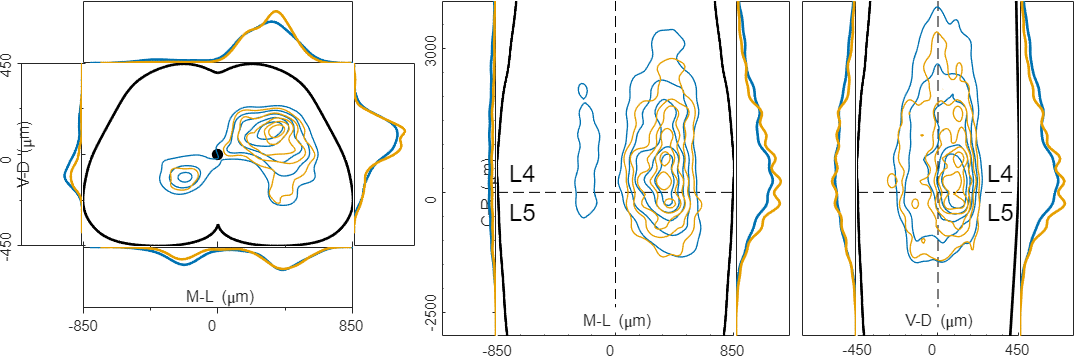

% Figure 4 figure supplement 1
masterdir = 'F:\documents\master\data\';
clearvars -except masterdir masterdir_raw nruns
ExpTypeString = {'chat', 'olig2','aav_wt',...
    'aav_chat','prv'};
MuscleType = {'lg','mg','gs','ta','pl'};
MuscleTypeSecond = {'nil', 'lg','mg','gs','ta','pl'};
ext = 'xlsx';
ExpType = {'chat'}; 
firstmuscle = {'lg'};
secondmuscle = {'ta'};
titer = 'low'; % can be 'high' or 'low'
concat = 1;
% Defines folders for each muscles and number of muscles

firstmuscledir = [masterdir,firstmuscle{1},'_',titer,'_',ExpType{1},'\'];
if ~isfolder(firstmuscledir)
    disp ('Please pick another first muscle: LG, MG and PL were injected only for experiments on ChAT-PhiGT, GS and TA were injected in all other experiments')
    firstfiles = [];
    return
else
    firstfiles = dir([firstmuscledir,'*.',ext]);
end

yes_second = ~contains(secondmuscle,'nil');

if yes_second
    secondmuscledir = [masterdir,secondmuscle{1},'_',titer,'_',ExpType{1},'\'];
    if ~isfolder(secondmuscledir)
        disp ('Please pick another second muscle: LG, MG and PL were injected only for experiments on ChAT-PhiGT, GS and TA were injected in all 9other experiments')
        secondfiles = [];
        return
    else
        secondfiles = dir([secondmuscledir,'*.',ext]);
    end
else
end

% [fnfirst,pathfirst] =  uigetfile([firstmuscledir,'*.xlsx'],'Select One or more files for first muscle', ...
%            'MultiSelect', 'on');
 fnfirst = {firstfiles(:).name}; %picks all files from first directory
 pathfirst = firstmuscledir;

if yes_second
%     [fnsecond,pathsecond] =  uigetfile([secondmuscledir,'*.xlsx'],'Select One or more files for second muscle', ...
%             'MultiSelect', 'on');    
    fnsecond = {secondfiles(:).name}; %picks all files from second directory
    pathsecond = secondmuscledir;
    nfiles_ = [length(string(fnfirst)), length(string(fnsecond))];
    dn = {pathfirst,pathsecond};
else   
    nfiles_ = length(string(fnfirst)); %here and above: string must be used to accommodate for single files
    dn = {pathfirst};
end
ndir = length(dn);

% declares all cell and matrix variables
ins = cell(1,ndir);
mns = cell(1,ndir);
gckin = cell(1,ndir);
gckmn = cell(1,ndir);
gckinxz = cell(1,ndir);
gckmnxz = cell(1,ndir);
gckinyz = cell(1,ndir);
gckmnyz = cell(1,ndir);

nfiles = [];
ptpeak = [];
prpeak = [];
plpeak = [];
pbpeak = [];
peakcontraxz = [];
peakipsixz = [];
peakcontrayz = [];
peakipsiyz = [];

% First index is the directory, second is file the extra i is to
% accommodate for choice of single files in order to keep the string format

if nfiles_(1)==1
    ins_{1}{1} = readmatrix([dn{1},fnfirst], 'Sheet',1);
    mns_{1}{1} = readmatrix([dn{1},fnfirst], 'Sheet',2);
else
    for j = 1:nfiles_(1)
        ins_{1}{j} = readmatrix([dn{1},fnfirst{j}], 'Sheet',1);
        mns_{1}{j} = readmatrix([dn{1},fnfirst{j}], 'Sheet',2);
    end
end

if size(nfiles_,2)==2
    if nfiles_(2) ==1
        ins_{2}{1} = readmatrix([dn{2},fnsecond], 'Sheet',1);
        mns_{2}{1} = readmatrix([dn{2},fnsecond], 'Sheet',2);
    else
        for j = 1:nfiles_(2)
            ins_{2}{j} = readmatrix([dn{2},fnsecond{j}], 'Sheet',1);
            mns_{2}{j} = readmatrix([dn{2},fnsecond{j}], 'Sheet',2);
        end
    end
else
end



if concat == 1
    for  i = 1:ndir
        % the extra {1} is to make it compatible with codes using
        % two indexes if files are not concatenated
        ins{i}{1} = vertcat(ins_{i}{:});
        mns{i}{1} = vertcat(mns_{i}{:});
    end
else
    for i = 1:ndir
        for j = 1:nfiles_(i)
            ins{i}{j} = ins_{i}{j};
            mns{i}{j} = mns_{i}{j};
        end
    end
end

% rewrite nfiles after concatenation
for i = 1:ndir
    nfiles(i) = size(ins{i},2);
end

%[ins,mns] = poolfun(dn,concat); % ins and mns have the same dimensions 

MNON = false; MNONPROJ = false;
qq = 6;
dotson = 0;
contlevlong = 5;
contlevtrans = 5;


% figure settings
autoscale = 1; % Set autoscale on Y axis of interneurons densities
ker = [5,5];          % kernel size
res = [100,100];         % kernel resolution

nr1 = 3;               % Number of rows in panel grid
nc1 = 9;               % Number of columns in panel grid
sizex1 = 15;           % Absolute width of figure (in cm)
sizey1 = 5;            % Absolute height of figure (in cm)         
margx = 0.1;           % x-margin between and around panels (normalised units)
margy = 0.1;           % y-margin between and around panels (normalised units)
labelalign = 'sw';     % NESW alignment of labels
labelfsize = 18;       % Label font size
% contlevlong = 5;       % contour levels for xz and yz plots
% contlevtrans = 5;      % contour levels for transverse slice
inmarkersize=2;        % size of Mn marker
mnmarkersize=5;        % size of Mn marker
mnlw = 0.01;            % width of Mn edge marker
contlw =1;             % line width for contours
lwconv = 2;            % line width of convolution plots

% loads tab files with sc profiles
scp = readmatrix('halfcordt.txt'); %transverse
scf = readmatrix('halfcordf.txt');  % frontal
sclv = readmatrix('halfcordf.txt');  % lateral ventral, same as frontal
scld = readmatrix('halfcordld.txt');  % lateral dorsal

if  isempty(mns)
    mns = [0,0,0];
    mnmarkersize=0;
    mnlw = 0;
end

   xl = [-.5,.5]; 
   yl = [-0.5,0.5];

    zl = [-4000,3000];
    plim = [0,0.01]; % these settings are overridden if autoscale is on
    plimz = [0,2e-5];
    plimlong = [0,0.23];
    
% color matrix: creates a matrix of colours scaling the primary colors to
% darker shades for increasing n of experiment. First index is directory,
% second is file

first = [0, 114, 178]/255; %{0, 0.4471, 0.6980}  %blu = 1st directory LG
firstdark = [0, 114, 178]/450; %{0, 0.2533, 0.3956} %dark blu = 2nd directory = MG
second = [230, 159, 0]/255;  %{0.9020, 0.6235,0} orange = TA inhibitory
seconddark = [180/255, 100/255, 0]; %{0.7059, 0.3922, 0} dark orange = TA excitatory
third = [0,0,1];

switch string(firstmuscle)
    case 'lg'
        primarycols{1} = first;
    case 'mg'
        primarycols{1} = firstdark;
    case 'gs'
        primarycols{1} = first;
    case 'ta'
        primarycols{1} = second;
    case 'pl'
        primarycols{1} = seconddark;
end

if yes_second
    switch string(secondmuscle)
        case 'lg'
            primarycols{2} = first
        case 'mg'
            primarycols{2} = firstdark;
        case 'gs'
            primarycols{2} = first;
        case 'ta'
            primarycols{2} = second;
        case 'pl'
            primarycols{2} = seconddark;
    end
else
    primarycols{2} = second;
end
primarycols{3} = third;

%primarycols = {first,second,third}; % standard list, GS=green, TA=red
scalecol = cell(1,ndir);
cols = cell(1,ndir);

for i = 1:ndir
   
    if nfiles(i) == 1
        scalecol{i} = 1;
    else
        scalecol{i} = linspace(1,0.5,nfiles(i));
    end
    
    for j = 1:nfiles(i)
    cols{i}{j} = primarycols{i}*scalecol{i}(j);

    end
end

for i = 1:ndir
    for j = 1:nfiles(i)
        gckin{i}{j} = gckernel();
        gckmn{i}{j} = gckernel();
        gckinxz{i}{j} = gckernel();
        gckmnxz{i}{j} = gckernel();
        gckinyz{i}{j} = gckernel();
        gckmnyz{i}{j} = gckernel();
      
    end
end
  
for i = 1:ndir
    for j = 1:nfiles(i)
        gckin{i}{j}.setData([ins{i}{j}(:,1)'; ins{i}{j}(:,2)'], [std(ins{i}{j}(:,1))/qq,std(ins{i}{j}(:,1))/qq]);
        gckin{i}{j}.convolve([ins{i}{j}(:,1)'; ins{i}{j}(:,2)']);
        %nomn = ~isempty(mns{i}{j}); %REPLACE NOMN WITH size(mns{i}{j}) for cases with 1 Mn only
        nmn = size(mns{i}{j},1);
        if nmn>1
            gckmn{i}{j}.convolve([mns{i}{j}(:,1)'; mns{i}{j}(:,2)']);
            gckmnxz{i}{j}.convolve([mns{i}{j}(:,1)'; mns{i}{j}(:,3)']);
        else
            
        end
        setKernel(gckin{i}{j},ker);
        setResd(gckin{i}{j},res);
        setKernel(gckinxz{i}{j},ker);
        setResd(gckinxz{i}{j},res);
        setKernel(gckinyz{i}{j},ker);
        setResd(gckinyz{i}{j},res);
        gckinxz{i}{j}.setData([ins{i}{j}(:,1)'; ins{i}{j}(:,3)'],[std(ins{i}{j}(:,1))/qq,std(ins{i}{j}(:,1))/qq]);
        gckinyz{i}{j}.setData([ins{i}{j}(:,2)'; ins{i}{j}(:,3)'],[std(ins{i}{j}(:,1))/qq,std(ins{i}{j}(:,1))/qq]);
        gckinxz{i}{j}.convolve([ins{i}{j}(:,1)'; ins{i}{j}(:,3)']);
        gckinyz{i}{j}.convolve([ins{i}{j}(:,2)'; ins{i}{j}(:,3)']);
        
    end
end

% OUTPUT FIGURE 1
f1 = figure;
%set(f1,'Position',[10 10 f1.Position(3) f1.Position(4)]);
set(f1,'Position',[10 10 1500 500]);
h = 0;
% aa = annotation('line', [0.14,0.25],[0.05,0.05]);
% aa.LineWidth = lwconv;
% annotation('textbox', [0.165,0.11,0.05,0.03],'String','1 mm','LineStyle','none','FontSize',15,'FitBoxToText','on');
% annotation('doublearrow', [0.805,0.935],[0.05,0.05]);
% annotation('textbox', [0.815,0.1,0.03,0.03],'String','V','LineStyle','none','FontSize',15,'FitBoxToText','on');
% annotation('textbox', [0.895,0.1,0.03,0.03],'String','D','LineStyle','none','FontSize',15,'FitBoxToText','on');
Panels = panels([nr1, nc1], [sizex1, sizey1], 1, [margx, margy]); % Initialise panel class instance
Panels.setLabels(Panels.lbl, labelalign, labelfsize);  

Panels.tweak(2,[-0.4,0.42],[2.5,0.5682]);
Panels.tweak(20,[-0.4,0.37],[2.5,0.5682]);
Panels.tweak(10,[0.14,-0.17],[0.5682,1.7]);
Panels.tweak(12,[1.0,-0.17],[0.5682,1.7]);
Panels.tweak(11,[-0.4,-0.17],[2.5,1.7]);
Panels.tweak(14,[0.1,-1.],[2.2,3.1]);
Panels.tweak(13,[0.7,-1.],[0.5,3.1]);
Panels.tweak(15,[1.2,-1.],[0.5,3.1]);
Panels.tweak(17,[0.1,-1.0],[1.5,3.1]);
Panels.tweak(16,[0.7,-1.0],[0.5,3.1]);
Panels.tweak(18,[0.5,-1.0],[0.5,3.1]);


h = 11;
dotxy = Panels.setPanel(h);
cc = plot (0,0,'ko');
    set(cc,'MarkerFaceColor',[0,0,0],'MarkerSize',8)
    hold on
plot(2*xl(2)*scp(:,1),2*yl(2)*scp(:,2),'LineWidth',lwconv,'Color','k'); %right halfcord
plot(-2*xl(2)*scp(:,1),2*yl(2)*scp(:,2),'LineWidth',lwconv,'Color','k'); %left halfcord
 for i = 1:ndir
    for j = 1:nfiles(i)
         x = gckin{i}{j}.x;
         y = gckin{i}{j}.y;
         P = gckin{i}{j}.P;
         
         if dotson
             inpl = plot(ins{i}{j}(:,1),ins{i}{j}(:,2),'.','MarkerEdgeColor',...
                 cols{i}{j},'MarkerSize',inmarkersize);
         else
             [MM,contu] = contour(x,y,P,contlevtrans);
             set(contu,'LineColor',cols{i}{j},'LineWidth',contlw );
         end
         
         nomn = ~isempty(mns{i}{j});
         if nomn && MNON
             mnpl = plot(mns{i}{j}(:,1),mns{i}{j}(:,2),'r^', 'MarkerSize',mnmarkersize,...
                 'MarkerFaceColor',cols{i}{j},'MarkerEdgeColor','k','LineWidth',mnlw);
         else
             
         end
            ax = gca;
         set (ax, 'xlim',xl, 'ylim',yl,'Visible','off','XTick',[],'YTick',[])
 box off
    end
 end

h = 2;
top = Panels.setPanel(h);
for i = 1:ndir
    for j = 1:nfiles(i)
         x = gckin{i}{j}.x;
         y = gckin{i}{j}.y;
         P = gckin{i}{j}.P;
         pt = sum( P(y>=0,:),1);
         ptpeak(i,j) = max(max(pt));
         topplot = plot(x,pt);
         %sum(pt)
         hold on
         set(topplot,'color',cols{i}{j}, 'LineWidth',lwconv);
         ax = gca;
         set(ax,'xlim', xl,'ylim',plim,'XTick',[],'YTick',[])         
 
    end
end

h = 12;
right = Panels.setPanel(h);
for i = 1:ndir
    for j = 1:nfiles(i)
         x = gckin{i}{j}.x;
         y = gckin{i}{j}.y;
         P = gckin{i}{j}.P;
         pr = sum( P(:,x>=0),2);
         prpeak(i,j) = max(max(pr));
         rightplot = plot(pr,y);
         hold on
         if MNONPROJ
             xmn = gckmn{i}{j}.x;
             ymn = gckmn{i}{j}.y;
             Pmn = gckmn{i}{j}.P;
             prmn = sum( Pmn(:,:),2);
             rightplotmn = plot(prmn,ymn);
             set(rightplotmn,'color',cols{i}{j}, 'LineStyle',':','LineWidth',lwconv);
         else
         end
         set(rightplot,'color',cols{i}{j}, 'LineWidth',lwconv);
         ax = gca;
         set(ax,'xlim',plim,'ylim', yl,'XTick',[],'YTick',[])   ;     

    end
end

h = 10;
left = Panels.setPanel(h);
for i = 1:ndir
    for j = 1:nfiles(i)   
         x = gckin{i}{j}.x;
         y = gckin{i}{j}.y;
         P = gckin{i}{j}.P;
         pl = sum( P(:,x<0),2);
         plpeak(i,j) = max(max(pl));
         leftplot = plot(pl,y);
         hold on
         set(leftplot,'color',cols{i}{j}, 'LineWidth',lwconv);
         ax = gca;
         set(ax,'ylim', yl,'xlim',plim,'xdir','reverse','XTick',[],...
             'YTick',[-0.5,0, 0.5],'YTickLabel',[-450,0,450],'YTickLabelRotation',90,...
         'TickLabelInterpreter','tex')   ;
         set(ax.YLabel,'Interpreter','tex');
         ax.YLabel.String = 'V-D (\mum)';
         ax.YLabel.Position = [0.0065 4.7684e-07];
         ax.YAxis.FontSize = 11;
         ax.YAxis.FontName = 'arial';
         ax.YAxis.MinorTick = 'on';
         ax.YAxis.MinorTickValues = [-0.5,-0.25,0,0.25,0.5]; 
         ax.YAxis.TickDirection = 'out';
         ax.YAxis.TickLength = [0.0200 0.0250];
    end
end

h = 20;
bot = Panels.setPanel(h);
for i = 1:ndir
    for j = 1:nfiles(i)   
         x = gckin{i}{j}.x;
         y = gckin{i}{j}.y;
         P = gckin{i}{j}.P;
         pb = sum( P(y<0,:),1);
         pbpeak(i,j) = max(max(pb));
         botplot = plot(x,pb);
         %sum(pb)
         hold on
        
         if MNONPROJ
             x = gckmn{i}{j}.x;
             y = gckmn{i}{j}.y;
             P = gckmn{i}{j}.P;
             pb = sum( P(:,:),1);
             botplotmn = plot(x,pb);
             set(botplotmn,'color',cols{i}{j}, 'LineStyle',':','LineWidth',lwconv);
         else
         end
         
         set(botplot,'color',cols{i}{j}, 'LineWidth',lwconv);
         ax = gca;
         set(ax,'xlim', xl,'ylim',plim,'ydir','reverse',...
             'XTick',[-0.5,0, 0.5],'XTickLabel',[-850,0,850],'YTick',[])   ; 
         set(ax.XLabel,'Interpreter','tex');
         ax.XLabel.String = 'M-L (\mum)';
         ax.XLabel.Position = [0.0065 0.006];
         ax.XAxis.FontSize = 11;
         ax.XAxis.FontName = 'arial';
         ax.XAxis.MinorTick = 'on';
         ax.XAxis.MinorTickValues = [-0.5,-0.25,0,0.25,0.5]; 
         ax.XAxis.TickDirection = 'out';
         ax.XAxis.TickLength = [0.0200 0.0250];

    end
end

% longitudinal xz

h = 13;
 contraxz = Panels.setPanel(h);
 for i = 1:ndir
    for j = 1:nfiles(i)
         x = gckinxz{i}{j}.x;
         y = gckinxz{i}{j}.y;
         P = gckinxz{i}{j}.P;
         pcontraxz = sum( P(:,x<0),2);
         plotcontra = plot(pcontraxz,y);
         peakcontraxz(i,j) = max(max(pcontraxz));
         hold on
         set (plotcontra,'color',cols{i}{j}, 'LineWidth',lwconv)
         ax  = gca;
         set (ax, 'ylim',zl,'xlim',plimlong,'xdir','reverse','ydir','reverse',...
             'XTick',[],'YTick',[-3000,0,2500],'YTickLabel',[3000,0,-2500],...
             'YTickLabelRotation',90)
         set(ax.YLabel,'Interpreter','tex');
         ax.YLabel.String = 'C-R (\mum)';
          ax.YLabel.Position = [-0.0015 4.7684e-07];
%         ax.YLabel.Position = [0.13 4.7684e-07];
         ax.YAxis.FontSize = 11;
         ax.YAxis.FontName = 'arial';
         ax.YAxis.MinorTick = 'on';

    end
 end
 
 
h=14;
dotxz = Panels.setPanel(h);
cc = plot ([0,0],[zl(1),0.8*zl(2)],'k','LineStyle','--');
        set(cc,'MarkerFaceColor',[0,0,0],'MarkerSize',8)
        hold on
plot(2*xl(2)*scf(:,1),-2*zl(2)*scf(:,2),'LineWidth',lwconv,'Color','k'); %right halfcord
plot(-2*xl(2)*scf(:,1),-2*zl(2)*scf(:,2),'LineWidth',lwconv,'Color','k'); %left halfcord 
plot(xl,[0,0],'k','LineStyle','--') 
        text(0.9*xl(1),400,'L5', 'FontSize', 18);
        text(0.9*xl(1),-400,'L4', 'FontSize', 18);
for i = 1:ndir
    for j = 1:nfiles(i)
         x = gckinxz{i}{j}.x;
         y = gckinxz{i}{j}.y;
         P = gckinxz{i}{j}.P;
         if dotson
             dotpl = plot(ins{i}{j}(:,1),ins{i}{j}(:,3),'.','MarkerSize',inmarkersize,...
                 'MarkerEdgeColor',cols{i}{j});
         else
             [MM,contu] = contour(x,y,P,contlevlong);
             set(contu,'LineColor',cols{i}{j},'LineWidth',contlw );
         end
        
         nomn = ~isempty(mns{i}{j});
         if nomn && MNON
             mnpl = plot(mns{i}{j}(:,1),mns{i}{j}(:,3),'r^', 'MarkerSize',mnmarkersize,...
                 'MarkerFaceColor',cols{i}{j},'MarkerEdgeColor','k','LineWidth',mnlw);
         else
         end
         
        ax = gca;
        set (ax, 'xlim',yl, 'ylim',zl,'XTick',[-0.5,0,0.5],'XTickLabels',[-850,0,850],...
            'YTick',[], 'ydir','reverse','YColor', [1 1 1])
         set(ax.XLabel,'Interpreter','tex');
         ax.XLabel.String = 'M-L (\mum)';
         ax.XLabel.Position = [0.0065 2500];
         ax.XAxis.FontSize = 11;
         ax.XAxis.FontName = 'arial';
         ax.XAxis.MinorTick = 'on';
  box off
    end
end


h = 15;
 ipsixz = Panels.setPanel(h);
 for i = 1:ndir
    for j = 1:nfiles(i)  
         x = gckinxz{i}{j}.x;
         y = gckinxz{i}{j}.y;
         P = gckinxz{i}{j}.P;
         pipsixz = sum( P(:,x>=0),2);
         peakipsixz(i,j) = max(max(pipsixz));         
         plotipsi = plot(pipsixz,y);
         hold on
         set (plotipsi,'color',cols{i}{j}, 'LineWidth',lwconv)
         ax  = gca;
         set (ax, 'ylim',zl,'xlim',plimlong,'ydir','reverse','XTick',[],'YTick',[])
    
    end
 end

% longitudinal yz

h = 16;
 contrayz = Panels.setPanel(h);
 for i = 1:ndir
    for j = 1:nfiles(i)
         x = gckinyz{i}{j}.x;
         y = gckinyz{i}{j}.y;
         P = gckinyz{i}{j}.P;
         pcontrayz = sum( P(:,x<0),2);
         peakcontrayz(i,j) = max(max(pcontrayz));
         plotcontra = plot(pcontrayz,y);
         hold on
         set (plotcontra,'color',cols{i}{j}, 'LineWidth',lwconv)
         ax  = gca;
         set (ax, 'ylim',zl,'xlim',plimlong,'xdir','reverse','ydir','reverse','XTick',[],'YTick',[])

    end
 end
 
 
h=17;
dotxz = Panels.setPanel(h);
cc = plot ([0,0],[zl(1),0.8*zl(2)],'k','LineStyle','--');
        set(cc,'MarkerFaceColor',[0,0,0],'MarkerSize',8)
        hold on
plot(-2*yl(2)*sclv(:,1),-2*zl(2)*sclv(:,2),'LineWidth',lwconv,'Color','k'); %ventral halfcord
plot(2*yl(2)*scld(:,1),-2*zl(2)*scld(:,2),'LineWidth',lwconv,'Color','k'); %dorsal halfcord
plot(xl,[0,0],'k','LineStyle','--') 
        text(0.6*yl(2),400,'L5', 'FontSize', 18);
        text(0.6*yl(2),-400,'L4', 'FontSize', 18);
for i = 1:ndir
    for j = 1:nfiles(i)   
         x = gckinyz{i}{j}.x;
         y = gckinyz{i}{j}.y;
         P = gckinyz{i}{j}.P;
         if dotson
             dotpl = plot(ins{i}{j}(:,2),ins{i}{j}(:,3),'.','MarkerSize',inmarkersize,...
                 'MarkerEdgeColor',cols{i}{j});
         else
             [MM,contu] = contour(x,y,P,contlevlong);
             set(contu,'LineColor',cols{i}{j},'LineWidth',contlw );
         end
        
         nomn = ~isempty(mns{i}{j});
         if nomn && MNON
             mnpl = plot(mns{i}{j}(:,2),mns{i}{j}(:,3),'r^', 'MarkerSize',mnmarkersize,...
                 'MarkerFaceColor',cols{i}{j},'MarkerEdgeColor','k','LineWidth',mnlw);
         else
         end
         
        ax = gca;
        set (ax, 'xlim',yl, 'ylim',zl,'XTick',[-0.5,0,0.5],'XTickLabels',[-450,0,450],...
            'YTick',[], 'ydir','reverse','YColor', [1 1 1])
         set(ax.XLabel,'Interpreter','tex');
         ax.XLabel.String = 'V-D (\mum)';
         ax.XLabel.Position = [0.0065 2500];
         ax.XAxis.FontSize = 11;
         ax.XAxis.FontName = 'arial';
         ax.XAxis.MinorTick = 'on';
  box off
    end
end


h = 18;
 ipsiyz = Panels.setPanel(h);
 for i = 1:ndir
    for j = 1:nfiles(i)   
         x = gckinyz{i}{j}.x;
         y = gckinyz{i}{j}.y;
         P = gckinyz{i}{j}.P;
         pipsiyz = sum( P(:,x>=0),2);
         peakipsiyz(i,j) = max(max(pipsiyz));
         plotipsi = plot(pipsiyz,y);
         hold on
         set (plotipsi,'color',cols{i}{j}, 'LineWidth',lwconv)
         ax  = gca;
         set (ax, 'ylim',zl,'xlim',plimlong,'ydir','reverse','XTick',[],'YTick',[])
    
    end
 end

 %%%%%%%%%% final assignment of axes limits to allow autoscale following
%%%%%%%%%% changes in kernel resolution

if autoscale
    %% transverse projection
    set(top, 'YLim',[0,1.2*max(max(max(ptpeak,pbpeak)))]); % pt and pb are row vectors
    set(bot, 'YLim',[0,1.2*max(max(max(ptpeak,pbpeak)))]);
    set(left, 'XLim',[0,1.2*max(max(max(plpeak,prpeak)))]); %pl and pr are column vector
    set(right, 'XLim',[0,1.2*max(max(max(plpeak,prpeak)))]);
    %% xz projection
    set(contraxz, 'XLim',[0,1.2*max(max(max(peakcontraxz,peakipsixz)))]);
    set(ipsixz, 'XLim',[0,1.2*max(max(max(peakcontraxz,peakipsixz)))]);
    %% yz projection
    set(contrayz, 'XLim',[0,1.2*max(max(max(peakcontrayz,peakipsiyz)))]);
    set(ipsiyz, 'XLim',[0,1.2*max(max(max(peakcontrayz,peakipsiyz)))]);
else
end

Panels.addPanels();

# Figure 4-figure supplement 2

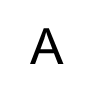

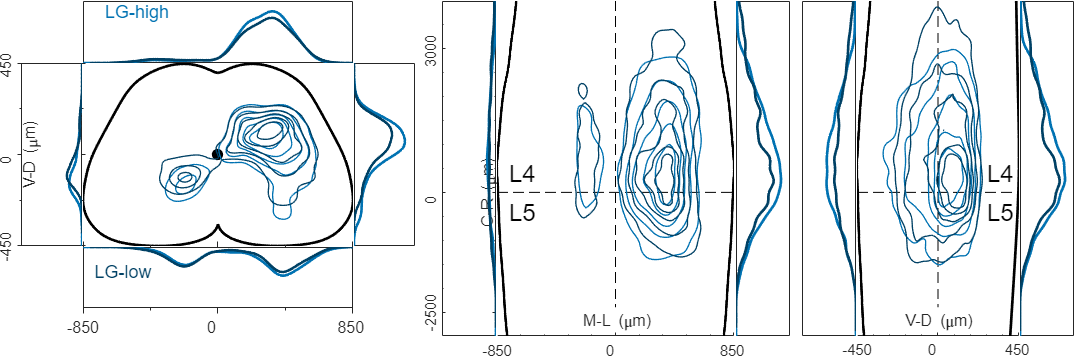

% Figure 4 figure supplement 2A
masterdir = 'F:\documents\master\data\';
clearvars -except masterdir masterdir_raw nruns
ExpTypeString = {'chat', 'olig2','aav_wt',...
    'aav_chat','prv'};
MuscleType = {'lg','mg','gs','ta','pl'};
MuscleTypeSecond = {'nil', 'lg','mg','gs','ta','pl'};
ext = 'xlsx';
ExpType = {'chat'}; 
firstmuscle = {'lg'};
secondmuscle = {'lg'};
titer = 'high'; % can be 'high' or 'low'
concat = 1;
% Defines folders for each muscles and number of muscles

firstmuscledir = [masterdir,firstmuscle{1},'_','high','_',ExpType{1},'\'];
if ~isfolder(firstmuscledir)
    disp ('Please pick another first muscle: LG, MG and PL were injected only for experiments on ChAT-PhiGT, GS and TA were injected in all other experiments')
    firstfiles = [];
    return
else
    firstfiles = dir([firstmuscledir,'*.',ext]);
end

yes_second = ~contains(secondmuscle,'nil');

if yes_second
    secondmuscledir = [masterdir,secondmuscle{1},'_','low','_',ExpType{1},'\'];
    if ~isfolder(secondmuscledir)
        disp ('Please pick another second muscle: LG, MG and PL were injected only for experiments on ChAT-PhiGT, GS and TA were injected in all 9other experiments')
        secondfiles = [];
        return
    else
        secondfiles = dir([secondmuscledir,'*.',ext]);
    end
else
end

% [fnfirst,pathfirst] =  uigetfile([firstmuscledir,'*.xlsx'],'Select One or more files for first muscle', ...
%            'MultiSelect', 'on');
 fnfirst = {firstfiles(:).name}; %picks all files from first directory
 pathfirst = firstmuscledir;

if yes_second
%     [fnsecond,pathsecond] =  uigetfile([secondmuscledir,'*.xlsx'],'Select One or more files for second muscle', ...
%             'MultiSelect', 'on');    
    fnsecond = {secondfiles(:).name}; %picks all files from second directory
    pathsecond = secondmuscledir;
    nfiles_ = [length(string(fnfirst)), length(string(fnsecond))];
    dn = {pathfirst,pathsecond};
else   
    nfiles_ = length(string(fnfirst)); %here and above: string must be used to accommodate for single files
    dn = {pathfirst};
end
ndir = length(dn);

% declares all cell and matrix variables
ins = cell(1,ndir);
mns = cell(1,ndir);
gckin = cell(1,ndir);
gckmn = cell(1,ndir);
gckinxz = cell(1,ndir);
gckmnxz = cell(1,ndir);
gckinyz = cell(1,ndir);
gckmnyz = cell(1,ndir);

nfiles = [];
ptpeak = [];
prpeak = [];
plpeak = [];
pbpeak = [];
peakcontraxz = [];
peakipsixz = [];
peakcontrayz = [];
peakipsiyz = [];

% First index is the directory, second is file the extra i is to
% accommodate for choice of single files in order to keep the string format

if nfiles_(1)==1
    ins_{1}{1} = readmatrix([dn{1},fnfirst], 'Sheet',1);
    mns_{1}{1} = readmatrix([dn{1},fnfirst], 'Sheet',2);
else
    for j = 1:nfiles_(1)
        ins_{1}{j} = readmatrix([dn{1},fnfirst{j}], 'Sheet',1);
        mns_{1}{j} = readmatrix([dn{1},fnfirst{j}], 'Sheet',2);
    end
end

if size(nfiles_,2)==2
    if nfiles_(2) ==1
        ins_{2}{1} = readmatrix([dn{2},fnsecond], 'Sheet',1);
        mns_{2}{1} = readmatrix([dn{2},fnsecond], 'Sheet',2);
    else
        for j = 1:nfiles_(2)
            ins_{2}{j} = readmatrix([dn{2},fnsecond{j}], 'Sheet',1);
            mns_{2}{j} = readmatrix([dn{2},fnsecond{j}], 'Sheet',2);
        end
    end
else
end



if concat == 1
    for  i = 1:ndir
        % the extra {1} is to make it compatible with codes using
        % two indexes if files are not concatenated
        ins{i}{1} = vertcat(ins_{i}{:});
        mns{i}{1} = vertcat(mns_{i}{:});
    end
else
    for i = 1:ndir
        for j = 1:nfiles_(i)
            ins{i}{j} = ins_{i}{j};
            mns{i}{j} = mns_{i}{j};
        end
    end
end

% rewrite nfiles after concatenation
for i = 1:ndir
    nfiles(i) = size(ins{i},2);
end

%[ins,mns] = poolfun(dn,concat); % ins and mns have the same dimensions 

MNON = false; MNONPROJ = false;
qq = 6;
dotson = 0;
contlevlong = 5;
contlevtrans = 5;


% figure settings
autoscale = 1; % Set autoscale on Y axis of interneurons densities
ker = [5,5];          % kernel size
res = [100,100];         % kernel resolution

nr1 = 3;               % Number of rows in panel grid
nc1 = 9;               % Number of columns in panel grid
sizex1 = 15;           % Absolute width of figure (in cm)
sizey1 = 5;            % Absolute height of figure (in cm)         
margx = 0.1;           % x-margin between and around panels (normalised units)
margy = 0.1;           % y-margin between and around panels (normalised units)
labelalign = 'sw';     % NESW alignment of labels
labelfsize = 18;       % Label font size
% contlevlong = 5;       % contour levels for xz and yz plots
% contlevtrans = 5;      % contour levels for transverse slice
inmarkersize=2;        % size of Mn marker
mnmarkersize=5;        % size of Mn marker
mnlw = 0.01;            % width of Mn edge marker
contlw =1;             % line width for contours
lwconv = 2;            % line width of convolution plots

% loads tab files with sc profiles
scp = readmatrix('halfcordt.txt'); %transverse
scf = readmatrix('halfcordf.txt');  % frontal
sclv = readmatrix('halfcordf.txt');  % lateral ventral, same as frontal
scld = readmatrix('halfcordld.txt');  % lateral dorsal

if  isempty(mns)
    mns = [0,0,0];
    mnmarkersize=0;
    mnlw = 0;
end

   xl = [-.5,.5]; 
   yl = [-0.5,0.5];

    zl = [-4000,3000];
    plim = [0,0.01]; % these settings are overridden if autoscale is on
    plimz = [0,2e-5];
    plimlong = [0,0.23];
    
% color matrix: creates a matrix of colours scaling the primary colors to
% darker shades for increasing n of experiment. First index is directory,
% second is file

first = [0, 114, 178]/255; %{0, 0.4471, 0.6980}  %blu = 1st directory LG
firstdark = [0, 114, 178]/450; %{0, 0.2533, 0.3956} %dark blu = 2nd directory = MG
second = [230, 159, 0]/255;  %{0.9020, 0.6235,0} orange = TA inhibitory
seconddark = [180/255, 100/255, 0]; %{0.7059, 0.3922, 0} dark orange = TA excitatory
third = [0,0,1];
 
primarycols{1} = first;
primarycols{2} = firstdark;

% switch string(firstmuscle)
%     case 'lg'
%         primarycols{1} = first;
%     case 'mg'
%         primarycols{1} = firstdark;
%     case 'gs'
%         primarycols{1} = first;
%     case 'ta'
%         primarycols{1} = second;
%     case 'pl'
%         primarycols{1} = seconddark;
% end
% 
% if yes_second
%     switch string(secondmuscle)
%         case 'lg'
%             primarycols{2} = first
%         case 'mg'
%             primarycols{2} = firstdark;
%         case 'gs'
%             primarycols{2} = first;
%         case 'ta'
%             primarycols{2} = second;
%         case 'pl'
%             primarycols{2} = seconddark;
%     end
% else
%     primarycols{2} = second;
% end
primarycols{3} = third;

%primarycols = {first,second,third}; % standard list, GS=green, TA=red
scalecol = cell(1,ndir);
cols = cell(1,ndir);

for i = 1:ndir
   
    if nfiles(i) == 1
        scalecol{i} = 1;
    else
        scalecol{i} = linspace(1,0.5,nfiles(i));
    end
    
    for j = 1:nfiles(i)
    cols{i}{j} = primarycols{i}*scalecol{i}(j);

    end
end

for i = 1:ndir
    for j = 1:nfiles(i)
        gckin{i}{j} = gckernel();
        gckmn{i}{j} = gckernel();
        gckinxz{i}{j} = gckernel();
        gckmnxz{i}{j} = gckernel();
        gckinyz{i}{j} = gckernel();
        gckmnyz{i}{j} = gckernel();
      
    end
end
  
for i = 1:ndir
    for j = 1:nfiles(i)
        gckin{i}{j}.setData([ins{i}{j}(:,1)'; ins{i}{j}(:,2)'], [std(ins{i}{j}(:,1))/qq,std(ins{i}{j}(:,1))/qq]);
        gckin{i}{j}.convolve([ins{i}{j}(:,1)'; ins{i}{j}(:,2)']);
        %nomn = ~isempty(mns{i}{j}); %REPLACE NOMN WITH size(mns{i}{j}) for cases with 1 Mn only
        nmn = size(mns{i}{j},1);
        if nmn>1
            gckmn{i}{j}.convolve([mns{i}{j}(:,1)'; mns{i}{j}(:,2)']);
            gckmnxz{i}{j}.convolve([mns{i}{j}(:,1)'; mns{i}{j}(:,3)']);
        else
            
        end
        setKernel(gckin{i}{j},ker);
        setResd(gckin{i}{j},res);
        setKernel(gckinxz{i}{j},ker);
        setResd(gckinxz{i}{j},res);
        setKernel(gckinyz{i}{j},ker);
        setResd(gckinyz{i}{j},res);
        gckinxz{i}{j}.setData([ins{i}{j}(:,1)'; ins{i}{j}(:,3)'],[std(ins{i}{j}(:,1))/qq,std(ins{i}{j}(:,1))/qq]);
        gckinyz{i}{j}.setData([ins{i}{j}(:,2)'; ins{i}{j}(:,3)'],[std(ins{i}{j}(:,1))/qq,std(ins{i}{j}(:,1))/qq]);
        gckinxz{i}{j}.convolve([ins{i}{j}(:,1)'; ins{i}{j}(:,3)']);
        gckinyz{i}{j}.convolve([ins{i}{j}(:,2)'; ins{i}{j}(:,3)']);
        
    end
end

% OUTPUT FIGURE 1
f1 = figure;
%set(f1,'Position',[10 10 f1.Position(3) f1.Position(4)]);
set(f1,'Position',[10 10 1500 500]);
h = 0;
% aa = annotation('line', [0.14,0.25],[0.05,0.05]);
% aa.LineWidth = lwconv;
% annotation('textbox', [0.165,0.11,0.05,0.03],'String','1 mm','LineStyle','none','FontSize',15,'FitBoxToText','on');
% annotation('doublearrow', [0.805,0.935],[0.05,0.05]);
% annotation('textbox', [0.815,0.1,0.03,0.03],'String','V','LineStyle','none','FontSize',15,'FitBoxToText','on');
% annotation('textbox', [0.895,0.1,0.03,0.03],'String','D','LineStyle','none','FontSize',15,'FitBoxToText','on');
Panels = panels([nr1, nc1], [sizex1, sizey1], 1, [margx, margy]); % Initialise panel class instance
Panels.setLabels(Panels.lbl, labelalign, labelfsize);  

Panels.tweak(2,[-0.4,0.42],[2.5,0.5682]);
Panels.tweak(20,[-0.4,0.37],[2.5,0.5682]);
Panels.tweak(10,[0.14,-0.17],[0.5682,1.7]);
Panels.tweak(12,[1.0,-0.17],[0.5682,1.7]);
Panels.tweak(11,[-0.4,-0.17],[2.5,1.7]);
Panels.tweak(14,[0.1,-1.],[2.2,3.1]);
Panels.tweak(13,[0.7,-1.],[0.5,3.1]);
Panels.tweak(15,[1.2,-1.],[0.5,3.1]);
Panels.tweak(17,[0.1,-1.0],[1.5,3.1]);
Panels.tweak(16,[0.7,-1.0],[0.5,3.1]);
Panels.tweak(18,[0.5,-1.0],[0.5,3.1]);


h = 11;
dotxy = Panels.setPanel(h);
cc = plot (0,0,'ko');
    set(cc,'MarkerFaceColor',[0,0,0],'MarkerSize',8)
    hold on
plot(2*xl(2)*scp(:,1),2*yl(2)*scp(:,2),'LineWidth',lwconv,'Color','k'); %right halfcord
plot(-2*xl(2)*scp(:,1),2*yl(2)*scp(:,2),'LineWidth',lwconv,'Color','k'); %left halfcord
 for i = 1:ndir
    for j = 1:nfiles(i)
         x = gckin{i}{j}.x;
         y = gckin{i}{j}.y;
         P = gckin{i}{j}.P;
         
         if dotson
             inpl = plot(ins{i}{j}(:,1),ins{i}{j}(:,2),'.','MarkerEdgeColor',...
                 cols{i}{j},'MarkerSize',inmarkersize);
         else
             [MM,contu] = contour(x,y,P,contlevtrans);
             set(contu,'LineColor',cols{i}{j},'LineWidth',contlw );
         end
         
         nomn = ~isempty(mns{i}{j});
         if nomn && MNON
             mnpl = plot(mns{i}{j}(:,1),mns{i}{j}(:,2),'r^', 'MarkerSize',mnmarkersize,...
                 'MarkerFaceColor',cols{i}{j},'MarkerEdgeColor','k','LineWidth',mnlw);
         else
             
         end
            ax = gca;
         set (ax, 'xlim',xl, 'ylim',yl,'Visible','off','XTick',[],'YTick',[])
 box off
    end
 end

h = 2;
top = Panels.setPanel(h);
for i = 1:ndir
    for j = 1:nfiles(i)
         x = gckin{i}{j}.x;
         y = gckin{i}{j}.y;
         P = gckin{i}{j}.P;
         pt = sum( P(y>=0,:),1);
         ptpeak(i,j) = max(max(pt));
         topplot = plot(x,pt);
         %sum(pt)
         hold on
         set(topplot,'color',cols{i}{j}, 'LineWidth',lwconv);
         ax = gca;
         set(ax,'xlim', xl,'ylim',plim,'XTick',[],'YTick',[])    
         set(ax.XLabel,'Interpreter','tex');
         ax.XLabel.String = '\color[rgb]{0, 0.4471, 0.6980}LG-high';
         ax.XLabel.Position = [0.6*xl(1), 0.8*plim(2)];
         ax.XAxis.FontSize = 12;
         ax.XAxis.FontName = 'arial';
 
    end
end

h = 12;
right = Panels.setPanel(h);
for i = 1:ndir
    for j = 1:nfiles(i)
         x = gckin{i}{j}.x;
         y = gckin{i}{j}.y;
         P = gckin{i}{j}.P;
         pr = sum( P(:,x>=0),2);
         prpeak(i,j) = max(max(pr));
         rightplot = plot(pr,y);
         hold on
         if MNONPROJ
             xmn = gckmn{i}{j}.x;
             ymn = gckmn{i}{j}.y;
             Pmn = gckmn{i}{j}.P;
             prmn = sum( Pmn(:,:),2);
             rightplotmn = plot(prmn,ymn);
             set(rightplotmn,'color',cols{i}{j}, 'LineStyle',':','LineWidth',lwconv);
         else
         end
         set(rightplot,'color',cols{i}{j}, 'LineWidth',lwconv);
         ax = gca;
         set(ax,'xlim',plim,'ylim', yl,'XTick',[],'YTick',[])   ;     

    end
end

h = 10;
left = Panels.setPanel(h);
for i = 1:ndir
    for j = 1:nfiles(i)   
         x = gckin{i}{j}.x;
         y = gckin{i}{j}.y;
         P = gckin{i}{j}.P;
         pl = sum( P(:,x<0),2);
         plpeak(i,j) = max(max(pl));
         leftplot = plot(pl,y);
         hold on
         set(leftplot,'color',cols{i}{j}, 'LineWidth',lwconv);
         ax = gca;
         set(ax,'ylim', yl,'xlim',plim,'xdir','reverse','XTick',[],...
             'YTick',[-0.5,0, 0.5],'YTickLabel',[-450,0,450],'YTickLabelRotation',90,...
         'TickLabelInterpreter','tex')   ;
         set(ax.YLabel,'Interpreter','tex');
         ax.YLabel.String = 'V-D (\mum)';
         ax.YLabel.Position = [0.0065 4.7684e-07];
         ax.YAxis.FontSize = 11;
         ax.YAxis.FontName = 'arial';
         ax.YAxis.MinorTick = 'on';
         ax.YAxis.MinorTickValues = [-0.5,-0.25,0,0.25,0.5]; 
         ax.YAxis.TickDirection = 'out';
         ax.YAxis.TickLength = [0.0200 0.0250];
    end
end

h = 20;
bot = Panels.setPanel(h);
for i = 1:ndir
    for j = 1:nfiles(i)   
         x = gckin{i}{j}.x;
         y = gckin{i}{j}.y;
         P = gckin{i}{j}.P;
         pb = sum( P(y<0,:),1);
         pbpeak(i,j) = max(max(pb));
         botplot = plot(x,pb);
         %sum(pb)
         hold on
        
         if MNONPROJ
             x = gckmn{i}{j}.x;
             y = gckmn{i}{j}.y;
             P = gckmn{i}{j}.P;
             pb = sum( P(:,:),1);
             botplotmn = plot(x,pb);
             set(botplotmn,'color',cols{i}{j}, 'LineStyle',':','LineWidth',lwconv);
         else
         end
         
         set(botplot,'color',cols{i}{j}, 'LineWidth',lwconv);
         ax = gca;
         set(ax,'xlim', xl,'ylim',plim,'ydir','reverse',...
             'XTick',[-0.5,0, 0.5],'XTickLabel',[-850,0,850],'YTick',[])   ; 
         set(ax.XLabel,'Interpreter','tex');
         ax.XLabel.String = 'M-L (\mum)';
         ax.XLabel.Position = [0.0065 0.006];
         ax.XAxis.FontSize = 11;
         ax.XAxis.FontName = 'arial';
         ax.XAxis.MinorTick = 'on';
         ax.XAxis.MinorTickValues = [-0.5,-0.25,0,0.25,0.5]; 
         ax.XAxis.TickDirection = 'out';
         ax.XAxis.TickLength = [0.0200 0.0250];
         set(ax.XLabel,'Interpreter','tex');
         ax.XLabel.String = '\color[rgb]{0, 0.2533, 0.3956}LG-low';
         ax.XLabel.Position = [0.7*xl(1), 0.2*plim(2)];
         ax.XAxis.FontSize = 12;
         ax.XAxis.FontName = 'arial';

    end
end

% longitudinal xz

h = 13;
 contraxz = Panels.setPanel(h);
 for i = 1:ndir
    for j = 1:nfiles(i)
         x = gckinxz{i}{j}.x;
         y = gckinxz{i}{j}.y;
         P = gckinxz{i}{j}.P;
         pcontraxz = sum( P(:,x<0),2);
         plotcontra = plot(pcontraxz,y);
         peakcontraxz(i,j) = max(max(pcontraxz));
         hold on
         set (plotcontra,'color',cols{i}{j}, 'LineWidth',lwconv)
         ax  = gca;
         set (ax, 'ylim',zl,'xlim',plimlong,'xdir','reverse','ydir','reverse',...
             'XTick',[],'YTick',[-3000,0,2500],'YTickLabel',[3000,0,-2500],...
             'YTickLabelRotation',90)
         set(ax.YLabel,'Interpreter','tex');
         ax.YLabel.String = 'C-R (\mum)';
          ax.YLabel.Position = [-0.0015 4.7684e-07];
%         ax.YLabel.Position = [0.13 4.7684e-07];
         ax.YAxis.FontSize = 11;
         ax.YAxis.FontName = 'arial';
         ax.YAxis.MinorTick = 'on';

    end
 end
 
 
h=14;
dotxz = Panels.setPanel(h);
cc = plot ([0,0],[zl(1),0.8*zl(2)],'k','LineStyle','--');
        set(cc,'MarkerFaceColor',[0,0,0],'MarkerSize',8)
        hold on
plot(2*xl(2)*scf(:,1),-2*zl(2)*scf(:,2),'LineWidth',lwconv,'Color','k'); %right halfcord
plot(-2*xl(2)*scf(:,1),-2*zl(2)*scf(:,2),'LineWidth',lwconv,'Color','k'); %left halfcord 
plot(xl,[0,0],'k','LineStyle','--') 
        text(0.9*xl(1),400,'L5', 'FontSize', 18);
        text(0.9*xl(1),-400,'L4', 'FontSize', 18);
for i = 1:ndir
    for j = 1:nfiles(i)
         x = gckinxz{i}{j}.x;
         y = gckinxz{i}{j}.y;
         P = gckinxz{i}{j}.P;
         if dotson
             dotpl = plot(ins{i}{j}(:,1),ins{i}{j}(:,3),'.','MarkerSize',inmarkersize,...
                 'MarkerEdgeColor',cols{i}{j});
         else
             [MM,contu] = contour(x,y,P,contlevlong);
             set(contu,'LineColor',cols{i}{j},'LineWidth',contlw );
         end
        
         nomn = ~isempty(mns{i}{j});
         if nomn && MNON
             mnpl = plot(mns{i}{j}(:,1),mns{i}{j}(:,3),'r^', 'MarkerSize',mnmarkersize,...
                 'MarkerFaceColor',cols{i}{j},'MarkerEdgeColor','k','LineWidth',mnlw);
         else
         end
         
        ax = gca;
        set (ax, 'xlim',yl, 'ylim',zl,'XTick',[-0.5,0,0.5],'XTickLabels',[-850,0,850],...
            'YTick',[], 'ydir','reverse','YColor', [1 1 1])
         set(ax.XLabel,'Interpreter','tex');
         ax.XLabel.String = 'M-L (\mum)';
         ax.XLabel.Position = [0.0065 2500];
         ax.XAxis.FontSize = 11;
         ax.XAxis.FontName = 'arial';
         ax.XAxis.MinorTick = 'on';
  box off
    end
end


h = 15;
 ipsixz = Panels.setPanel(h);
 for i = 1:ndir
    for j = 1:nfiles(i)  
         x = gckinxz{i}{j}.x;
         y = gckinxz{i}{j}.y;
         P = gckinxz{i}{j}.P;
         pipsixz = sum( P(:,x>=0),2);
         peakipsixz(i,j) = max(max(pipsixz));         
         plotipsi = plot(pipsixz,y);
         hold on
         set (plotipsi,'color',cols{i}{j}, 'LineWidth',lwconv)
         ax  = gca;
         set (ax, 'ylim',zl,'xlim',plimlong,'ydir','reverse','XTick',[],'YTick',[])
    
    end
 end

% longitudinal yz

h = 16;
 contrayz = Panels.setPanel(h);
 for i = 1:ndir
    for j = 1:nfiles(i)
         x = gckinyz{i}{j}.x;
         y = gckinyz{i}{j}.y;
         P = gckinyz{i}{j}.P;
         pcontrayz = sum( P(:,x<0),2);
         peakcontrayz(i,j) = max(max(pcontrayz));
         plotcontra = plot(pcontrayz,y);
         hold on
         set (plotcontra,'color',cols{i}{j}, 'LineWidth',lwconv)
         ax  = gca;
         set (ax, 'ylim',zl,'xlim',plimlong,'xdir','reverse','ydir','reverse','XTick',[],'YTick',[])

    end
 end
 
 
h=17;
dotxz = Panels.setPanel(h);
cc = plot ([0,0],[zl(1),0.8*zl(2)],'k','LineStyle','--');
        set(cc,'MarkerFaceColor',[0,0,0],'MarkerSize',8)
        hold on
plot(-2*yl(2)*sclv(:,1),-2*zl(2)*sclv(:,2),'LineWidth',lwconv,'Color','k'); %ventral halfcord
plot(2*yl(2)*scld(:,1),-2*zl(2)*scld(:,2),'LineWidth',lwconv,'Color','k'); %dorsal halfcord
plot(xl,[0,0],'k','LineStyle','--') 
        text(0.6*yl(2),400,'L5', 'FontSize', 18);
        text(0.6*yl(2),-400,'L4', 'FontSize', 18);
for i = 1:ndir
    for j = 1:nfiles(i)   
         x = gckinyz{i}{j}.x;
         y = gckinyz{i}{j}.y;
         P = gckinyz{i}{j}.P;
         if dotson
             dotpl = plot(ins{i}{j}(:,2),ins{i}{j}(:,3),'.','MarkerSize',inmarkersize,...
                 'MarkerEdgeColor',cols{i}{j});
         else
             [MM,contu] = contour(x,y,P,contlevlong);
             set(contu,'LineColor',cols{i}{j},'LineWidth',contlw );
         end
        
         nomn = ~isempty(mns{i}{j});
         if nomn && MNON
             mnpl = plot(mns{i}{j}(:,2),mns{i}{j}(:,3),'r^', 'MarkerSize',mnmarkersize,...
                 'MarkerFaceColor',cols{i}{j},'MarkerEdgeColor','k','LineWidth',mnlw);
         else
         end
         
        ax = gca;
        set (ax, 'xlim',yl, 'ylim',zl,'XTick',[-0.5,0,0.5],'XTickLabels',[-450,0,450],...
            'YTick',[], 'ydir','reverse','YColor', [1 1 1])
         set(ax.XLabel,'Interpreter','tex');
         ax.XLabel.String = 'V-D (\mum)';
         ax.XLabel.Position = [0.0065 2500];
         ax.XAxis.FontSize = 11;
         ax.XAxis.FontName = 'arial';
         ax.XAxis.MinorTick = 'on';
  box off
    end
end


h = 18;
 ipsiyz = Panels.setPanel(h);
 for i = 1:ndir
    for j = 1:nfiles(i)   
         x = gckinyz{i}{j}.x;
         y = gckinyz{i}{j}.y;
         P = gckinyz{i}{j}.P;
         pipsiyz = sum( P(:,x>=0),2);
         peakipsiyz(i,j) = max(max(pipsiyz));
         plotipsi = plot(pipsiyz,y);
         hold on
         set (plotipsi,'color',cols{i}{j}, 'LineWidth',lwconv)
         ax  = gca;
         set (ax, 'ylim',zl,'xlim',plimlong,'ydir','reverse','XTick',[],'YTick',[])
    
    end
 end

 %%%%%%%%%% final assignment of axes limits to allow autoscale following
%%%%%%%%%% changes in kernel resolution

if autoscale
    %% transverse projection
    set(top, 'YLim',[0,1.2*max(max(max(ptpeak,pbpeak)))]); % pt and pb are row vectors
    set(bot, 'YLim',[0,1.2*max(max(max(ptpeak,pbpeak)))]);
    set(left, 'XLim',[0,1.2*max(max(max(plpeak,prpeak)))]); %pl and pr are column vector
    set(right, 'XLim',[0,1.2*max(max(max(plpeak,prpeak)))]);
    %% xz projection
    set(contraxz, 'XLim',[0,1.2*max(max(max(peakcontraxz,peakipsixz)))]);
    set(ipsixz, 'XLim',[0,1.2*max(max(max(peakcontraxz,peakipsixz)))]);
    %% yz projection
    set(contrayz, 'XLim',[0,1.2*max(max(max(peakcontrayz,peakipsiyz)))]);
    set(ipsiyz, 'XLim',[0,1.2*max(max(max(peakcontrayz,peakipsiyz)))]);
else
end

Panels.addPanels();

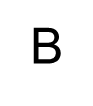                                                    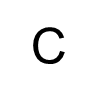                                                  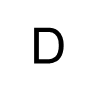

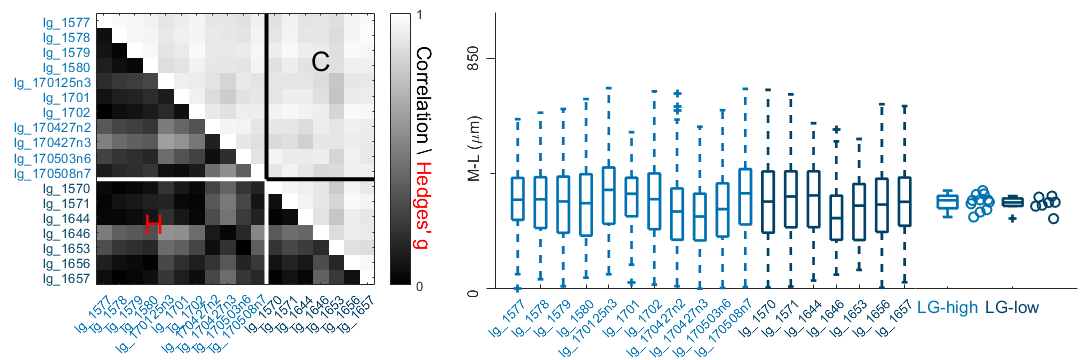

% figure 4 figure supplement 2 B,C,D

clearvars -except masterdir masterdir_raw nruns

    dn = {'F:\documents\master\data\lg_high_chat\',...
        'F:\documents\master\data\lg_low_chat\'};%,...
    ndir = length(dn);
    for i = 1:ndir
        labels{i} =  [extractBetween(dn{i},'data\','\xyz'),'--',dn{i}( strlength(dn{i})-2 :strlength(dn{i})-1) ]  ;
    end



%%%%%%%%%%%%%%% switch to go straight to figure, rather than redoing
%%%%%%%%%%%%%%% calculations
readdata = 1;
%%%%%%%%%%%%%%%%

% figure settings
nr1 = 1;               % Number of rows in panel grid
nc1 = 3;               % Number of columns in panel grid
sizex1 = 15;           % Absolute width of figure (in cm)
sizey1 = 5;            % Absolute height of figure (in cm)         
margx = 0.1;           % x-margin between and around panels (normalised units)
margy = 0.1;           % y-margin between and around panels (normalised units)
labelalign = 'sw';     % NESW alignment of labels
labelfsize = 18;       % Label font size



% these  parameters control the appearance of the plot, with files concateanted,
% with contour, dots and with or without Mns
%%%%%%%%%%%%%%%%%%%%%%%
concat = 0;  % if concat=1 concatenates all files in directory
%%%%% kernel parameters for longitudinal sections  %%%%%%
ker = [5,5];          % kernel size
res = [20,20]; % kernel resolution
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

if readdata

[ins,mns] = poolfun(dn,concat); % ins and mns have the same dimensions 
[allins,allmns] = poolfun(dn,1); % ins and mns have the same dimensions 


for i = 1:ndir
    nfiles(i) = size(ins{i},2);
end

% color settings
% firstcolor = [0, 114, 178]/255;  %blu = GS
% secondcolor = [230, 159, 0]/255;% {0.9020, 0.6235,0}%orange = TA
% firstdark = [0, 114, 178]/450; %{0, 0.2533, 0.3956} %dark blu = 2nd directory = MG
% seconddark = [180/255, 100/255, 0]; %dark orange %{0.7059, 0.3922, 0} dark orange= TA excitatory or PL

firstcolor = [0, 114, 178]/255;  %blu = GS
secondcolor = [0, 114, 178]/450; %{0, 0.2533, 0.3956} %dark blu = 2nd directory = MG
%  firstcolor = [0, 114, 178]/255;  %blu = GS
%  secondcolor = [0, 114, 178]/450; %{0, 0.2533, 0.3956} %dark blu = 2nd directory = MG

%allcolor = vertcat(repmat(firstcolor,nfiles(1),1), repmat(secondcolor,nfiles(2),1)); % for GS and TA
allcolor = vertcat(repmat(firstcolor,nfiles(1),1), repmat(secondcolor,nfiles(2),1)); % for other pairs of muscles

ndir = length(dn);
ext = 'xlsx';

for i = 1:ndir
files_{i} = dir([dn{i},'*.',ext]);
end
gsins = [];
for i = 1:nfiles(1)
        gsname{i} = files_{1}(i).name;
        gsname{i} = extractBefore(gsname{i},'_n');
        gsname{i} = strrep(gsname{i},'gs','lg');
        gsname{i} = insertBefore(gsname{i}, 'lg','\color[rgb]{0.0,0.4471,0.6980}'); %= [0, 114, 178]/255;  %blu = 2nd directory = GS
        gsins = vertcat(gsins,ins{1}{i});
end
tains = [];
for i = 1:nfiles(2)
        taname{i} = files_{2}(i).name;
        taname{i} = extractBefore(taname{i},'_n');
        taname{i} = strrep(taname{i},'gs','lg');
        taname{i} = insertBefore(taname{i}, 'lg','\color[rgb]{0, 0.2533, 0.3956}'); % =[230, 159, 0]/255; %dark blue = 1st directory = TA
        tains = vertcat(tains,ins{2}{i});
end
names = horzcat(gsname, taname);
names = insertBefore(names,'_','\');


for i = 1:ndir
    for j = 1:nfiles(i)
       median_ml{i}(j) = median(ins{i}{j}(ins{i}{j}(:,2)>0 & ins{i}{j}(:,1)>0,1));
    end
end

gck = gckernel();
setKernel(gck,ker);
setResd(gck,res);
junk = gck.convolve([allins{1}{1}(:,1)' ; allins{1}{1}(:,2)']); %intializes values of bins


% method 1
for i = 1:ndir
    for j = 1:nfiles(i)
        conv_result1{i}{j} = gck.convolve ([ins{i}{j}(:,1)';ins{i}{j}(:,2)']);
    end
end

% Lines up the files from the two direcotries to give a single matrix
for  i = 1:ndir
    for j = 1:nfiles(i)
        j+(i-1)*nfiles(ndir-1);
        conv_result_all{j+(i-1)*nfiles(ndir-1)} =conv_result1{i}{j};
        conv_result_ml{j+(i-1)*nfiles(ndir-1)} =sum(conv_result1{i}{j},1);
        ins_all{j+(i-1)*nfiles(ndir-1)} = ins{i}{j};
    end
end

ins_all_mat=[];
for i = 1:size(ins_all,2)
    ins_all_mat = nanhcat(ins_all_mat,ins_all{i}(ins_all{i}(:,2)>0 & ins_all{i}(:,1)>0 ,1));
    ins_all_d_ipsi{i} = ins_all{i}(ins_all{i}(:,2)>0 & ins_all{i}(:,1)>0 ,1); %selects x coordinates for neurons in the ipsi dorsal quaadrant
end

for i = 1: size(conv_result_all,2)
    for j = 1:size(conv_result_all,2)
       
     %CXYconv(i,j) = corr2(conv_result_all{i},conv_result_all{j}); % uses the mean as center of distributions
     CXYconv(i,j) = corr2median(conv_result_all{i},conv_result_all{j}); % uses the median as center of distributions
%      [HKS(i,j), pKS(i,j), KSstatistic] = kstest2(conv_result_ml{i}, conv_result_ml{j});  
%      [pperm(i,j), observeddifference, effectsize] = permutationTest(ins_all{i}(ins_all{i}(:,2)>0 & ins_all{i}(:,1)>0 ,1), ins_all{j}(ins_all{j}(:,2)>0 & ins_all{j}(:,1)>0 ,1),1000);
     [pranksum_x(i,j), Hranksum_x(i,j),ranksumstatistic_x(i,j)] = ranksum(ins_all{i}(ins_all{i}(:,2)>0 & ins_all{i}(:,1)>0 ,1), ins_all{j}(ins_all{j}(:,2)>0 & ins_all{j}(:,1)>0 ,1));  
     hedges(i,j) = hedges_fun(ins_all_d_ipsi{i},ins_all_d_ipsi{j});
     
    end
end

else
end

f1 = figure;
%set(f1,'Position',[1 1 f1.Position(3) f1.Position(4)])
h = 0;
Panels = panels([nr1, nc1], [sizex1, sizey1], 1, [margx, margy]); % Initialise panel class instance
Panels.setLabels(Panels.lbl, labelalign, labelfsize);  
Panels.tweak(1,[0.24,0.12],[1.05,0.84]);
Panels.tweak(2,[0.36,0.],[1.3,0.95]);
Panels.tweak(3,[0.55,0.108],[0.5,0.85]);

% correlation panel;
%hmap =heatmap(CXYHIST,'XDisplayLabels',names, 'YDisplayLabels',names, 'CellLabelColor','r');
h =1;
corr_fig = Panels.setPanel(h);
%define rectangular matrix. the 'skip varaible adds whites on the digaonal
%to separate Hedges and correlation
skip = 0;
frame = zeros(size(conv_result_all,2),size(conv_result_all,2)+skip);
frame_corr = frame+ horzcat(zeros(size(conv_result_all,2),skip),triu(CXYconv));
frame_corr_hedges = frame_corr + horzcat(tril(hedges),zeros(size(conv_result_all,2),skip));

%defines colormap (0 is white, -1 and 1 are black)

bl_to_white = find(frame_corr_hedges==0);
frame_corr_hedges(bl_to_white)=1;
mapcorr = imagesc(abs(frame_corr_hedges),[0,1]);
hh = colormap(gray);
cmap = vertcat(hh,flipud(hh));
colormap(gray);
%cbcorr = colorbar;

ax = gca;
 set (ax,'YTick',1:sum(nfiles),'YTickLabel',names,'XTick',1:sum(nfiles),'XTickLabel',names,...
     'XTickLabelRotation', 45);
hold on
cbcorr = colorbar;
set(cbcorr,'FontSize',10, 'Ticks',[0,1] );
cbcorr.Label.String = {'\color[rgb]{0,0,0}Correlation \\ \color[rgb]{1,0,0}Hedges'' g'};
cbcorr.Label.FontSize = 15;
cbcorr.Label.Rotation = -90;
cbcorr.Label.Position = [2.2879 0.5000 0];
%left bottom
ph = plot([nfiles(1)+0.5,nfiles(1)+0.5],[nfiles(1)-0.5,sum(nfiles)+0.5],'w','LineWidth',3); %vertical
plot([1-0.5,nfiles(1)+0.5], [nfiles(1)+0.5,nfiles(1)+0.5],'w','LineWidth',3); %horizontal
%caxis([0,1]);
%top right
ph = plot([nfiles(1)+skip+0.5,nfiles(1)+skip+0.5],[1-0.5,nfiles(1)+0.5],'k','LineWidth',3); %vertical
plot([nfiles(1)+skip+0.5,sum(nfiles)+skip+0.5], [nfiles(1)+0.5,nfiles(1)+0.5],'k','LineWidth',3); %horizontal
colormap(gray)
caxis([0,1]);
txtshift = 0.8;
text( (1-txtshift)*sum(nfiles),txtshift*sum(nfiles),'\fontname{arial}\color[rgb]{1,0,0}H','FontSize',20)
text(txtshift*sum(nfiles),(1-txtshift)*sum(nfiles),'\fontname{arial}\color[rgb]{0,0,0}C','FontSize',20)


h =2;
allins_fig = Panels.setPanel(h);
bpall = boxplot(ins_all_mat,'Color',allcolor, 'Symbol','+');
set(bpall,{'linew'},{2})
axall=gca;
set(axall,'XLim',[0,nfiles(1)+nfiles(2)+0.5],'YLim',[0,0.6],'TickLabelInterpreter','tex',...
    'XTick',1:sum(nfiles),'XTickLabel',names, 'XTickLabelRotation', 45,...
    'YTick', [0,0.5], 'YTickLabels',  [0,850],...
    'YTickLabelRotation', 90);
          set(axall.YLabel,'Interpreter','tex');
         axall.YLabel.String = 'M-L (\mum)';
         axall.YLabel.Position = [-0.5165 0.306];
         axall.YAxis.FontSize = 11;
         axall.YAxis.FontName = 'arial';
         axall.YAxis.MinorTick = 'on';
         axall.YAxis.MinorTickValues = [-0.5,-0.25,0,0.25,0.5]; 
         axall.YAxis.TickDirection = 'out';
         axall.YAxis.TickLength = [0.0200 .3250];

box off


h =3;
summary_fig = Panels.setPanel(h);
bp = boxplot(nanhcat(median_ml{1}', median_ml{2}'),'Color',[firstcolor;secondcolor],'Symbol','+');
set(bp,{'linew'},{2})
ax3 = gca;
set(ax3,'XLim',[0.5,3],'YLim',[0,0.6],'TickLabelInterpreter','tex',...
    'XTickLabel',{'\color[rgb]{0.0,0.4471,0.6980}LG-high', '\color[rgb]{0, 0.2533, 0.3956}LG-low'},...
    'FontSize',13);
ax3.YAxis.Visible = 'off';
hold on
ps = dischart(nanhcat(median_ml{1}', median_ml{2}'),[1.5,2.5],0.4,[],'','','o');
set(ps{1},'MarkerEdgeColor',firstcolor,'LineWidth',1.5, 'MarkerSize',7);
set(ps{2},'MarkerEdgeColor',secondcolor,'LineWidth',1.5, 'MarkerSize',7);
box off




Panels.addPanels();

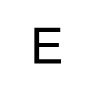

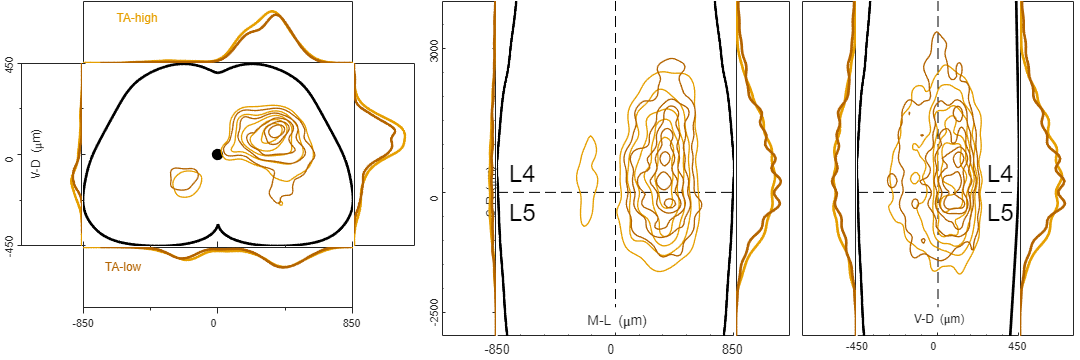

% Figure 4 figure supplement 2E
masterdir = 'F:\documents\master\data\';
clearvars -except masterdir masterdir_raw nruns
ExpTypeString = {'chat', 'olig2','aav_wt',...
    'aav_chat','prv'};
MuscleType = {'lg','mg','gs','ta','pl'};
MuscleTypeSecond = {'nil', 'lg','mg','gs','ta','pl'};
ext = 'xlsx';
ExpType = {'chat'}; 
firstmuscle = {'ta'};
secondmuscle = {'ta'};
titer = 'high'; % can be 'high' or 'low'
concat = 1;
% Defines folders for each muscles and number of muscles

firstmuscledir = [masterdir,firstmuscle{1},'_','high','_',ExpType{1},'\'];
if ~isfolder(firstmuscledir)
    disp ('Please pick another first muscle: LG, MG and PL were injected only for experiments on ChAT-PhiGT, GS and TA were injected in all other experiments')
    firstfiles = [];
    return
else
    firstfiles = dir([firstmuscledir,'*.',ext]);
end

yes_second = ~contains(secondmuscle,'nil');

if yes_second
    secondmuscledir = [masterdir,secondmuscle{1},'_','low','_',ExpType{1},'\'];
    if ~isfolder(secondmuscledir)
        disp ('Please pick another second muscle: LG, MG and PL were injected only for experiments on ChAT-PhiGT, GS and TA were injected in all 9other experiments')
        secondfiles = [];
        return
    else
        secondfiles = dir([secondmuscledir,'*.',ext]);
    end
else
end

% [fnfirst,pathfirst] =  uigetfile([firstmuscledir,'*.xlsx'],'Select One or more files for first muscle', ...
%            'MultiSelect', 'on');
 fnfirst = {firstfiles(:).name}; %picks all files from first directory
 pathfirst = firstmuscledir;

if yes_second
%     [fnsecond,pathsecond] =  uigetfile([secondmuscledir,'*.xlsx'],'Select One or more files for second muscle', ...
%             'MultiSelect', 'on');    
    fnsecond = {secondfiles(:).name}; %picks all files from second directory
    pathsecond = secondmuscledir;
    nfiles_ = [length(string(fnfirst)), length(string(fnsecond))];
    dn = {pathfirst,pathsecond};
else   
    nfiles_ = length(string(fnfirst)); %here and above: string must be used to accommodate for single files
    dn = {pathfirst};
end
ndir = length(dn);

% declares all cell and matrix variables
ins = cell(1,ndir);
mns = cell(1,ndir);
gckin = cell(1,ndir);
gckmn = cell(1,ndir);
gckinxz = cell(1,ndir);
gckmnxz = cell(1,ndir);
gckinyz = cell(1,ndir);
gckmnyz = cell(1,ndir);

nfiles = [];
ptpeak = [];
prpeak = [];
plpeak = [];
pbpeak = [];
peakcontraxz = [];
peakipsixz = [];
peakcontrayz = [];
peakipsiyz = [];

% First index is the directory, second is file the extra i is to
% accommodate for choice of single files in order to keep the string format

if nfiles_(1)==1
    ins_{1}{1} = readmatrix([dn{1},fnfirst], 'Sheet',1);
    mns_{1}{1} = readmatrix([dn{1},fnfirst], 'Sheet',2);
else
    for j = 1:nfiles_(1)
        ins_{1}{j} = readmatrix([dn{1},fnfirst{j}], 'Sheet',1);
        mns_{1}{j} = readmatrix([dn{1},fnfirst{j}], 'Sheet',2);
    end
end

if size(nfiles_,2)==2
    if nfiles_(2) ==1
        ins_{2}{1} = readmatrix([dn{2},fnsecond], 'Sheet',1);
        mns_{2}{1} = readmatrix([dn{2},fnsecond], 'Sheet',2);
    else
        for j = 1:nfiles_(2)
            ins_{2}{j} = readmatrix([dn{2},fnsecond{j}], 'Sheet',1);
            mns_{2}{j} = readmatrix([dn{2},fnsecond{j}], 'Sheet',2);
        end
    end
else
end



if concat == 1
    for  i = 1:ndir
        % the extra {1} is to make it compatible with codes using
        % two indexes if files are not concatenated
        ins{i}{1} = vertcat(ins_{i}{:});
        mns{i}{1} = vertcat(mns_{i}{:});
    end
else
    for i = 1:ndir
        for j = 1:nfiles_(i)
            ins{i}{j} = ins_{i}{j};
            mns{i}{j} = mns_{i}{j};
        end
    end
end

% rewrite nfiles after concatenation
for i = 1:ndir
    nfiles(i) = size(ins{i},2);
end

%[ins,mns] = poolfun(dn,concat); % ins and mns have the same dimensions 

MNON = false; MNONPROJ = false;
qq = 6;
dotson = 0;
contlevlong = 5;
contlevtrans = 5;


% figure settings
autoscale = 1; % Set autoscale on Y axis of interneurons densities
ker = [5,5];          % kernel size
res = [100,100];         % kernel resolution

nr1 = 3;               % Number of rows in panel grid
nc1 = 9;               % Number of columns in panel grid
sizex1 = 15;           % Absolute width of figure (in cm)
sizey1 = 5;            % Absolute height of figure (in cm)         
margx = 0.1;           % x-margin between and around panels (normalised units)
margy = 0.1;           % y-margin between and around panels (normalised units)
labelalign = 'sw';     % NESW alignment of labels
labelfsize = 18;       % Label font size
% contlevlong = 5;       % contour levels for xz and yz plots
% contlevtrans = 5;      % contour levels for transverse slice
inmarkersize=2;        % size of Mn marker
mnmarkersize=5;        % size of Mn marker
mnlw = 0.01;            % width of Mn edge marker
contlw =1;             % line width for contours
lwconv = 2;            % line width of convolution plots

% loads tab files with sc profiles
scp = readmatrix('halfcordt.txt'); %transverse
scf = readmatrix('halfcordf.txt');  % frontal
sclv = readmatrix('halfcordf.txt');  % lateral ventral, same as frontal
scld = readmatrix('halfcordld.txt');  % lateral dorsal

if  isempty(mns)
    mns = [0,0,0];
    mnmarkersize=0;
    mnlw = 0;
end

   xl = [-.5,.5]; 
   yl = [-0.5,0.5];

    zl = [-4000,3000];
    plim = [0,0.01]; % these settings are overridden if autoscale is on
    plimz = [0,2e-5];
    plimlong = [0,0.23];
    
% color matrix: creates a matrix of colours scaling the primary colors to
% darker shades for increasing n of experiment. First index is directory,
% second is file

first = [0, 114, 178]/255; %{0, 0.4471, 0.6980}  %blu = 1st directory LG
firstdark = [0, 114, 178]/450; %{0, 0.2533, 0.3956} %dark blu = 2nd directory = MG
second = [230, 159, 0]/255;  %{0.9020, 0.6235,0} orange = TA inhibitory
seconddark = [180/255, 100/255, 0]; %{0.7059, 0.3922, 0} dark orange = TA excitatory
third = [0,0,1];
 
primarycols{1} = second;
primarycols{2} = seconddark;

% switch string(firstmuscle)
%     case 'lg'
%         primarycols{1} = first;
%     case 'mg'
%         primarycols{1} = firstdark;
%     case 'gs'
%         primarycols{1} = first;
%     case 'ta'
%         primarycols{1} = second;
%     case 'pl'
%         primarycols{1} = seconddark;
% end
% 
% if yes_second
%     switch string(secondmuscle)
%         case 'lg'
%             primarycols{2} = first
%         case 'mg'
%             primarycols{2} = firstdark;
%         case 'gs'
%             primarycols{2} = first;
%         case 'ta'
%             primarycols{2} = second;
%         case 'pl'
%             primarycols{2} = seconddark;
%     end
% else
%     primarycols{2} = second;
% end
primarycols{3} = third;

%primarycols = {first,second,third}; % standard list, GS=green, TA=red
scalecol = cell(1,ndir);
cols = cell(1,ndir);

for i = 1:ndir
   
    if nfiles(i) == 1
        scalecol{i} = 1;
    else
        scalecol{i} = linspace(1,0.5,nfiles(i));
    end
    
    for j = 1:nfiles(i)
    cols{i}{j} = primarycols{i}*scalecol{i}(j);

    end
end

for i = 1:ndir
    for j = 1:nfiles(i)
        gckin{i}{j} = gckernel();
        gckmn{i}{j} = gckernel();
        gckinxz{i}{j} = gckernel();
        gckmnxz{i}{j} = gckernel();
        gckinyz{i}{j} = gckernel();
        gckmnyz{i}{j} = gckernel();
      
    end
end
  
for i = 1:ndir
    for j = 1:nfiles(i)
        gckin{i}{j}.setData([ins{i}{j}(:,1)'; ins{i}{j}(:,2)'], [std(ins{i}{j}(:,1))/qq,std(ins{i}{j}(:,1))/qq]);
        gckin{i}{j}.convolve([ins{i}{j}(:,1)'; ins{i}{j}(:,2)']);
        %nomn = ~isempty(mns{i}{j}); %REPLACE NOMN WITH size(mns{i}{j}) for cases with 1 Mn only
        nmn = size(mns{i}{j},1);
        if nmn>1
            gckmn{i}{j}.convolve([mns{i}{j}(:,1)'; mns{i}{j}(:,2)']);
            gckmnxz{i}{j}.convolve([mns{i}{j}(:,1)'; mns{i}{j}(:,3)']);
        else
            
        end
        setKernel(gckin{i}{j},ker);
        setResd(gckin{i}{j},res);
        setKernel(gckinxz{i}{j},ker);
        setResd(gckinxz{i}{j},res);
        setKernel(gckinyz{i}{j},ker);
        setResd(gckinyz{i}{j},res);
        gckinxz{i}{j}.setData([ins{i}{j}(:,1)'; ins{i}{j}(:,3)'],[std(ins{i}{j}(:,1))/qq,std(ins{i}{j}(:,1))/qq]);
        gckinyz{i}{j}.setData([ins{i}{j}(:,2)'; ins{i}{j}(:,3)'],[std(ins{i}{j}(:,1))/qq,std(ins{i}{j}(:,1))/qq]);
        gckinxz{i}{j}.convolve([ins{i}{j}(:,1)'; ins{i}{j}(:,3)']);
        gckinyz{i}{j}.convolve([ins{i}{j}(:,2)'; ins{i}{j}(:,3)']);
        
    end
end

% OUTPUT FIGURE 1
f1 = figure;
%set(f1,'Position',[10 10 f1.Position(3) f1.Position(4)]);
set(f1,'Position',[10 10 1500 500]);
h = 0;
% aa = annotation('line', [0.14,0.25],[0.05,0.05]);
% aa.LineWidth = lwconv;
% annotation('textbox', [0.165,0.11,0.05,0.03],'String','1 mm','LineStyle','none','FontSize',15,'FitBoxToText','on');
% annotation('doublearrow', [0.805,0.935],[0.05,0.05]);
% annotation('textbox', [0.815,0.1,0.03,0.03],'String','V','LineStyle','none','FontSize',15,'FitBoxToText','on');
% annotation('textbox', [0.895,0.1,0.03,0.03],'String','D','LineStyle','none','FontSize',15,'FitBoxToText','on');
Panels = panels([nr1, nc1], [sizex1, sizey1], 1, [margx, margy]); % Initialise panel class instance
Panels.setLabels(Panels.lbl, labelalign, labelfsize);  

Panels.tweak(2,[-0.4,0.42],[2.5,0.5682]);
Panels.tweak(20,[-0.4,0.37],[2.5,0.5682]);
Panels.tweak(10,[0.14,-0.17],[0.5682,1.7]);
Panels.tweak(12,[1.0,-0.17],[0.5682,1.7]);
Panels.tweak(11,[-0.4,-0.17],[2.5,1.7]);
Panels.tweak(14,[0.1,-1.],[2.2,3.1]);
Panels.tweak(13,[0.7,-1.],[0.5,3.1]);
Panels.tweak(15,[1.2,-1.],[0.5,3.1]);
Panels.tweak(17,[0.1,-1.0],[1.5,3.1]);
Panels.tweak(16,[0.7,-1.0],[0.5,3.1]);
Panels.tweak(18,[0.5,-1.0],[0.5,3.1]);


h = 11;
dotxy = Panels.setPanel(h);
cc = plot (0,0,'ko');
    set(cc,'MarkerFaceColor',[0,0,0],'MarkerSize',8)
    hold on
plot(2*xl(2)*scp(:,1),2*yl(2)*scp(:,2),'LineWidth',lwconv,'Color','k'); %right halfcord
plot(-2*xl(2)*scp(:,1),2*yl(2)*scp(:,2),'LineWidth',lwconv,'Color','k'); %left halfcord
 for i = 1:ndir
    for j = 1:nfiles(i)
         x = gckin{i}{j}.x;
         y = gckin{i}{j}.y;
         P = gckin{i}{j}.P;
         
         if dotson
             inpl = plot(ins{i}{j}(:,1),ins{i}{j}(:,2),'.','MarkerEdgeColor',...
                 cols{i}{j},'MarkerSize',inmarkersize);
         else
             [MM,contu] = contour(x,y,P,contlevtrans);
             set(contu,'LineColor',cols{i}{j},'LineWidth',contlw );
         end
         
         nomn = ~isempty(mns{i}{j});
         if nomn && MNON
             mnpl = plot(mns{i}{j}(:,1),mns{i}{j}(:,2),'r^', 'MarkerSize',mnmarkersize,...
                 'MarkerFaceColor',cols{i}{j},'MarkerEdgeColor','k','LineWidth',mnlw);
         else
             
         end
            ax = gca;
         set (ax, 'xlim',xl, 'ylim',yl,'Visible','off','XTick',[],'YTick',[])
 box off
    end
 end

h = 2;
top = Panels.setPanel(h);
for i = 1:ndir
    for j = 1:nfiles(i)
         x = gckin{i}{j}.x;
         y = gckin{i}{j}.y;
         P = gckin{i}{j}.P;
         pt = sum( P(y>=0,:),1);
         ptpeak(i,j) = max(max(pt));
         topplot = plot(x,pt);
         %sum(pt)
         hold on
         set(topplot,'color',cols{i}{j}, 'LineWidth',lwconv);
         ax = gca;
         set(ax,'xlim', xl,'ylim',plim,'XTick',[],'YTick',[])
         set(ax.XLabel,'Interpreter','tex');
         ax.XLabel.String = '\color[rgb]{0.9020, 0.6235,0}TA-high';
         ax.XLabel.Position = [0.6*xl(1), 0.8*plim(2)];
         ax.XAxis.FontSize = 12;
         ax.XAxis.FontName = 'arial';
 
    end
end

h = 12;
right = Panels.setPanel(h);
for i = 1:ndir
    for j = 1:nfiles(i)
         x = gckin{i}{j}.x;
         y = gckin{i}{j}.y;
         P = gckin{i}{j}.P;
         pr = sum( P(:,x>=0),2);
         prpeak(i,j) = max(max(pr));
         rightplot = plot(pr,y);
         hold on
         if MNONPROJ
             xmn = gckmn{i}{j}.x;
             ymn = gckmn{i}{j}.y;
             Pmn = gckmn{i}{j}.P;
             prmn = sum( Pmn(:,:),2);
             rightplotmn = plot(prmn,ymn);
             set(rightplotmn,'color',cols{i}{j}, 'LineStyle',':','LineWidth',lwconv);
         else
         end
         set(rightplot,'color',cols{i}{j}, 'LineWidth',lwconv);
         ax = gca;
         set(ax,'xlim',plim,'ylim', yl,'XTick',[],'YTick',[])   ;     

    end
end

h = 10;
left = Panels.setPanel(h);
for i = 1:ndir
    for j = 1:nfiles(i)   
         x = gckin{i}{j}.x;
         y = gckin{i}{j}.y;
         P = gckin{i}{j}.P;
         pl = sum( P(:,x<0),2);
         plpeak(i,j) = max(max(pl));
         leftplot = plot(pl,y);
         hold on
         set(leftplot,'color',cols{i}{j}, 'LineWidth',lwconv);
         ax = gca;
         set(ax,'ylim', yl,'xlim',plim,'xdir','reverse','XTick',[],...
             'YTick',[-0.5,0, 0.5],'YTickLabel',[-450,0,450],'YTickLabelRotation',90,...
         'TickLabelInterpreter','tex')   ;
         set(ax.YLabel,'Interpreter','tex');
         ax.YLabel.String = 'V-D (\mum)';
         ax.YLabel.Position = [0.0065 4.7684e-07];
         ax.YAxis.FontSize = 11;
         ax.YAxis.FontName = 'arial';
         ax.YAxis.MinorTick = 'on';
         ax.YAxis.MinorTickValues = [-0.5,-0.25,0,0.25,0.5]; 
         ax.YAxis.TickDirection = 'out';
         ax.YAxis.TickLength = [0.0200 0.0250];
    end
end

h = 20;
bot = Panels.setPanel(h);
for i = 1:ndir
    for j = 1:nfiles(i)   
         x = gckin{i}{j}.x;
         y = gckin{i}{j}.y;
         P = gckin{i}{j}.P;
         pb = sum( P(y<0,:),1);
         pbpeak(i,j) = max(max(pb));
         botplot = plot(x,pb);
         %sum(pb)
         hold on
        
         if MNONPROJ
             x = gckmn{i}{j}.x;
             y = gckmn{i}{j}.y;
             P = gckmn{i}{j}.P;
             pb = sum( P(:,:),1);
             botplotmn = plot(x,pb);
             set(botplotmn,'color',cols{i}{j}, 'LineStyle',':','LineWidth',lwconv);
         else
         end
         
         set(botplot,'color',cols{i}{j}, 'LineWidth',lwconv);
         ax = gca;
         set(ax,'xlim', xl,'ylim',plim,'ydir','reverse',...
             'XTick',[-0.5,0, 0.5],'XTickLabel',[-850,0,850],'YTick',[])   ; 
         set(ax.XLabel,'Interpreter','tex');
         ax.XLabel.String = 'M-L (\mum)';
         ax.XLabel.Position = [0.0065 0.006];
         ax.XAxis.FontSize = 11;
         ax.XAxis.FontName = 'arial';
         ax.XAxis.MinorTick = 'on';
         ax.XAxis.MinorTickValues = [-0.5,-0.25,0,0.25,0.5]; 
         ax.XAxis.TickDirection = 'out';
         ax.XAxis.TickLength = [0.0200 0.0250];
         set(ax.XLabel,'Interpreter','tex');
         ax.XLabel.String = '\color[rgb]{0.7059, 0.3922, 0}TA-low';
         ax.XLabel.Position = [0.7*xl(1), 0.2*plim(2)];
         ax.XAxis.FontSize = 12;
         ax.XAxis.FontName = 'arial';

    end
end

% longitudinal xz

h = 13;
 contraxz = Panels.setPanel(h);
 for i = 1:ndir
    for j = 1:nfiles(i)
         x = gckinxz{i}{j}.x;
         y = gckinxz{i}{j}.y;
         P = gckinxz{i}{j}.P;
         pcontraxz = sum( P(:,x<0),2);
         plotcontra = plot(pcontraxz,y);
         peakcontraxz(i,j) = max(max(pcontraxz));
         hold on
         set (plotcontra,'color',cols{i}{j}, 'LineWidth',lwconv)
         ax  = gca;
         set (ax, 'ylim',zl,'xlim',plimlong,'xdir','reverse','ydir','reverse',...
             'XTick',[],'YTick',[-3000,0,2500],'YTickLabel',[3000,0,-2500],...
             'YTickLabelRotation',90)
         set(ax.YLabel,'Interpreter','tex');
         ax.YLabel.String = 'C-R (\mum)';
          ax.YLabel.Position = [-0.0015 4.7684e-07];
%         ax.YLabel.Position = [0.13 4.7684e-07];
         ax.YAxis.FontSize = 11;
         ax.YAxis.FontName = 'arial';
         ax.YAxis.MinorTick = 'on';

    end
 end
 
 
h=14;
dotxz = Panels.setPanel(h);
cc = plot ([0,0],[zl(1),0.8*zl(2)],'k','LineStyle','--');
        set(cc,'MarkerFaceColor',[0,0,0],'MarkerSize',8)
        hold on
plot(2*xl(2)*scf(:,1),-2*zl(2)*scf(:,2),'LineWidth',lwconv,'Color','k'); %right halfcord
plot(-2*xl(2)*scf(:,1),-2*zl(2)*scf(:,2),'LineWidth',lwconv,'Color','k'); %left halfcord 
plot(xl,[0,0],'k','LineStyle','--') 
        text(0.9*xl(1),400,'L5', 'FontSize', 18);
        text(0.9*xl(1),-400,'L4', 'FontSize', 18);
for i = 1:ndir
    for j = 1:nfiles(i)
         x = gckinxz{i}{j}.x;
         y = gckinxz{i}{j}.y;
         P = gckinxz{i}{j}.P;
         if dotson
             dotpl = plot(ins{i}{j}(:,1),ins{i}{j}(:,3),'.','MarkerSize',inmarkersize,...
                 'MarkerEdgeColor',cols{i}{j});
         else
             [MM,contu] = contour(x,y,P,contlevlong);
             set(contu,'LineColor',cols{i}{j},'LineWidth',contlw );
         end
        
         nomn = ~isempty(mns{i}{j});
         if nomn && MNON
             mnpl = plot(mns{i}{j}(:,1),mns{i}{j}(:,3),'r^', 'MarkerSize',mnmarkersize,...
                 'MarkerFaceColor',cols{i}{j},'MarkerEdgeColor','k','LineWidth',mnlw);
         else
         end
         
        ax = gca;
        set (ax, 'xlim',yl, 'ylim',zl,'XTick',[-0.5,0,0.5],'XTickLabels',[-850,0,850],...
            'YTick',[], 'ydir','reverse','YColor', [1 1 1])
         set(ax.XLabel,'Interpreter','tex');
         ax.XLabel.String = 'M-L (\mum)';
         ax.XLabel.Position = [0.0065 2500];
         ax.XAxis.FontSize = 11;
         ax.XAxis.FontName = 'arial';
         ax.XAxis.MinorTick = 'on';
  box off
    end
end


h = 15;
 ipsixz = Panels.setPanel(h);
 for i = 1:ndir
    for j = 1:nfiles(i)  
         x = gckinxz{i}{j}.x;
         y = gckinxz{i}{j}.y;
         P = gckinxz{i}{j}.P;
         pipsixz = sum( P(:,x>=0),2);
         peakipsixz(i,j) = max(max(pipsixz));         
         plotipsi = plot(pipsixz,y);
         hold on
         set (plotipsi,'color',cols{i}{j}, 'LineWidth',lwconv)
         ax  = gca;
         set (ax, 'ylim',zl,'xlim',plimlong,'ydir','reverse','XTick',[],'YTick',[])
    
    end
 end

% longitudinal yz

h = 16;
 contrayz = Panels.setPanel(h);
 for i = 1:ndir
    for j = 1:nfiles(i)
         x = gckinyz{i}{j}.x;
         y = gckinyz{i}{j}.y;
         P = gckinyz{i}{j}.P;
         pcontrayz = sum( P(:,x<0),2);
         peakcontrayz(i,j) = max(max(pcontrayz));
         plotcontra = plot(pcontrayz,y);
         hold on
         set (plotcontra,'color',cols{i}{j}, 'LineWidth',lwconv)
         ax  = gca;
         set (ax, 'ylim',zl,'xlim',plimlong,'xdir','reverse','ydir','reverse','XTick',[],'YTick',[])

    end
 end
 
 
h=17;
dotxz = Panels.setPanel(h);
cc = plot ([0,0],[zl(1),0.8*zl(2)],'k','LineStyle','--');
        set(cc,'MarkerFaceColor',[0,0,0],'MarkerSize',8)
        hold on
plot(-2*yl(2)*sclv(:,1),-2*zl(2)*sclv(:,2),'LineWidth',lwconv,'Color','k'); %ventral halfcord
plot(2*yl(2)*scld(:,1),-2*zl(2)*scld(:,2),'LineWidth',lwconv,'Color','k'); %dorsal halfcord
plot(xl,[0,0],'k','LineStyle','--') 
        text(0.6*yl(2),400,'L5', 'FontSize', 18);
        text(0.6*yl(2),-400,'L4', 'FontSize', 18);
for i = 1:ndir
    for j = 1:nfiles(i)   
         x = gckinyz{i}{j}.x;
         y = gckinyz{i}{j}.y;
         P = gckinyz{i}{j}.P;
         if dotson
             dotpl = plot(ins{i}{j}(:,2),ins{i}{j}(:,3),'.','MarkerSize',inmarkersize,...
                 'MarkerEdgeColor',cols{i}{j});
         else
             [MM,contu] = contour(x,y,P,contlevlong);
             set(contu,'LineColor',cols{i}{j},'LineWidth',contlw );
         end
        
         nomn = ~isempty(mns{i}{j});
         if nomn && MNON
             mnpl = plot(mns{i}{j}(:,2),mns{i}{j}(:,3),'r^', 'MarkerSize',mnmarkersize,...
                 'MarkerFaceColor',cols{i}{j},'MarkerEdgeColor','k','LineWidth',mnlw);
         else
         end
         
        ax = gca;
        set (ax, 'xlim',yl, 'ylim',zl,'XTick',[-0.5,0,0.5],'XTickLabels',[-450,0,450],...
            'YTick',[], 'ydir','reverse','YColor', [1 1 1])
         set(ax.XLabel,'Interpreter','tex');
         ax.XLabel.String = 'V-D (\mum)';
         ax.XLabel.Position = [0.0065 2500];
         ax.XAxis.FontSize = 11;
         ax.XAxis.FontName = 'arial';
         ax.XAxis.MinorTick = 'on';
  box off
    end
end


h = 18;
 ipsiyz = Panels.setPanel(h);
 for i = 1:ndir
    for j = 1:nfiles(i)   
         x = gckinyz{i}{j}.x;
         y = gckinyz{i}{j}.y;
         P = gckinyz{i}{j}.P;
         pipsiyz = sum( P(:,x>=0),2);
         peakipsiyz(i,j) = max(max(pipsiyz));
         plotipsi = plot(pipsiyz,y);
         hold on
         set (plotipsi,'color',cols{i}{j}, 'LineWidth',lwconv)
         ax  = gca;
         set (ax, 'ylim',zl,'xlim',plimlong,'ydir','reverse','XTick',[],'YTick',[])
    
    end
 end

 %%%%%%%%%% final assignment of axes limits to allow autoscale following
%%%%%%%%%% changes in kernel resolution

if autoscale
    %% transverse projection
    set(top, 'YLim',[0,1.2*max(max(max(ptpeak,pbpeak)))]); % pt and pb are row vectors
    set(bot, 'YLim',[0,1.2*max(max(max(ptpeak,pbpeak)))]);
    set(left, 'XLim',[0,1.2*max(max(max(plpeak,prpeak)))]); %pl and pr are column vector
    set(right, 'XLim',[0,1.2*max(max(max(plpeak,prpeak)))]);
    %% xz projection
    set(contraxz, 'XLim',[0,1.2*max(max(max(peakcontraxz,peakipsixz)))]);
    set(ipsixz, 'XLim',[0,1.2*max(max(max(peakcontraxz,peakipsixz)))]);
    %% yz projection
    set(contrayz, 'XLim',[0,1.2*max(max(max(peakcontrayz,peakipsiyz)))]);
    set(ipsiyz, 'XLim',[0,1.2*max(max(max(peakcontrayz,peakipsiyz)))]);
else
end

Panels.addPanels();

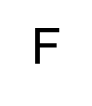                                                  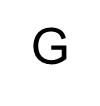                                                  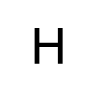

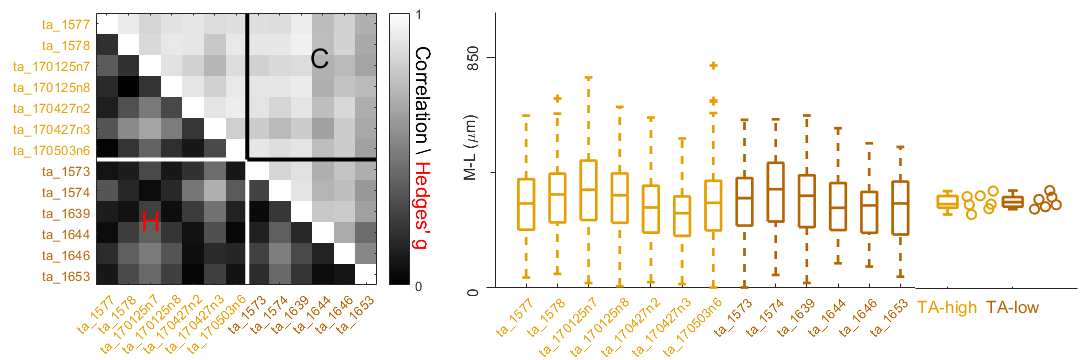

% figure 4 figure supplement 2 F,G,H

clearvars -except masterdir masterdir_raw nruns

    dn = {'F:\documents\master\data\ta_high_chat\',...
        'F:\documents\master\data\ta_low_chat\'};%,...
    ndir = length(dn);
    for i = 1:ndir
        labels{i} =  [extractBetween(dn{i},'data\','\xyz'),'--',dn{i}( strlength(dn{i})-2 :strlength(dn{i})-1) ]  ;
    end



%%%%%%%%%%%%%%% switch to go straight to figure, rather than redoing
%%%%%%%%%%%%%%% calculations
readdata = 1;
%%%%%%%%%%%%%%%%

% figure settings
nr1 = 1;               % Number of rows in panel grid
nc1 = 3;               % Number of columns in panel grid
sizex1 = 15;           % Absolute width of figure (in cm)
sizey1 = 5;            % Absolute height of figure (in cm)         
margx = 0.1;           % x-margin between and around panels (normalised units)
margy = 0.1;           % y-margin between and around panels (normalised units)
labelalign = 'sw';     % NESW alignment of labels
labelfsize = 18;       % Label font size



% these  parameters control the appearance of the plot, with files concateanted,
% with contour, dots and with or without Mns
%%%%%%%%%%%%%%%%%%%%%%%
concat = 0;  % if concat=1 concatenates all files in directory
%%%%% kernel parameters for longitudinal sections  %%%%%%
ker = [5,5];          % kernel size
res = [20,20]; % kernel resolution
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

if readdata

[ins,mns] = poolfun(dn,concat); % ins and mns have the same dimensions 
[allins,allmns] = poolfun(dn,1); % ins and mns have the same dimensions 


for i = 1:ndir
    nfiles(i) = size(ins{i},2);
end

% color settings
% firstcolor = [0, 114, 178]/255;  %blu = GS
% secondcolor = [230, 159, 0]/255;% {0.9020, 0.6235,0}%orange = TA
% firstdark = [0, 114, 178]/450; %{0, 0.2533, 0.3956} %dark blu = 2nd directory = MG
% seconddark = [180/255, 100/255, 0]; %dark orange %{0.7059, 0.3922, 0} dark orange= TA excitatory or PL

firstcolor = [230, 159, 0]/255;% {0.9020, 0.6235,0}%orange = TA
secondcolor = [180/255, 100/255, 0]; %dark orange %{0.7059, 0.3922, 0} dark orange=
%  firstcolor = [0, 114, 178]/255;  %blu = GS
%  secondcolor = [0, 114, 178]/450; %{0, 0.2533, 0.3956} %dark blu = 2nd directory = MG

%allcolor = vertcat(repmat(firstcolor,nfiles(1),1), repmat(secondcolor,nfiles(2),1)); % for GS and TA
allcolor = vertcat(repmat(firstcolor,nfiles(1),1), repmat(secondcolor,nfiles(2),1)); % for other pairs of muscles

ndir = length(dn);
ext = 'xlsx';

for i = 1:ndir
files_{i} = dir([dn{i},'*.',ext]);
end
gsins = [];
for i = 1:nfiles(1)
        gsname{i} = files_{1}(i).name;
        gsname{i} = extractBefore(gsname{i},'_n');
       % gsname{i} = strrep(gsname{i},'gs','lg');
        gsname{i} = insertBefore(gsname{i}, 'ta','\color[rgb]{0.9020, 0.6235,0}'); %= [0, 114, 178]/255;  %blu = 2nd directory = GS
        gsins = vertcat(gsins,ins{1}{i});
end
tains = [];
for i = 1:nfiles(2)
        taname{i} = files_{2}(i).name;
        taname{i} = extractBefore(taname{i},'_n');
        %taname{i} = strrep(taname{i},'gs','lg');
        taname{i} = insertBefore(taname{i}, 'ta','\color[rgb]{0.7059, 0.3922, 0}'); % =[230, 159, 0]/255; %dark blue = 1st directory = TA
        tains = vertcat(tains,ins{2}{i});
end
names = horzcat(gsname, taname);
names = insertBefore(names,'_','\');


for i = 1:ndir
    for j = 1:nfiles(i)
       median_ml{i}(j) = median(ins{i}{j}(ins{i}{j}(:,2)>0 & ins{i}{j}(:,1)>0,1));
    end
end

gck = gckernel();
setKernel(gck,ker);
setResd(gck,res);
junk = gck.convolve([allins{1}{1}(:,1)' ; allins{1}{1}(:,2)']); %intializes values of bins


% method 1
for i = 1:ndir
    for j = 1:nfiles(i)
        conv_result1{i}{j} = gck.convolve ([ins{i}{j}(:,1)';ins{i}{j}(:,2)']);
    end
end

% Lines up the files from the two direcotries to give a single matrix
for  i = 1:ndir
    for j = 1:nfiles(i)
        j+(i-1)*nfiles(ndir-1);
        conv_result_all{j+(i-1)*nfiles(ndir-1)} =conv_result1{i}{j};
        conv_result_ml{j+(i-1)*nfiles(ndir-1)} =sum(conv_result1{i}{j},1);
        ins_all{j+(i-1)*nfiles(ndir-1)} = ins{i}{j};
    end
end

ins_all_mat=[];
for i = 1:size(ins_all,2)
    ins_all_mat = nanhcat(ins_all_mat,ins_all{i}(ins_all{i}(:,2)>0 & ins_all{i}(:,1)>0 ,1));
    ins_all_d_ipsi{i} = ins_all{i}(ins_all{i}(:,2)>0 & ins_all{i}(:,1)>0 ,1); %selects x coordinates for neurons in the ipsi dorsal quaadrant
end

for i = 1: size(conv_result_all,2)
    for j = 1:size(conv_result_all,2)
       
     %CXYconv(i,j) = corr2(conv_result_all{i},conv_result_all{j}); % uses the mean as center of distributions
     CXYconv(i,j) = corr2median(conv_result_all{i},conv_result_all{j}); % uses the median as center of distributions
%      [HKS(i,j), pKS(i,j), KSstatistic] = kstest2(conv_result_ml{i}, conv_result_ml{j});  
%      [pperm(i,j), observeddifference, effectsize] = permutationTest(ins_all{i}(ins_all{i}(:,2)>0 & ins_all{i}(:,1)>0 ,1), ins_all{j}(ins_all{j}(:,2)>0 & ins_all{j}(:,1)>0 ,1),1000);
     [pranksum_x(i,j), Hranksum_x(i,j),ranksumstatistic_x(i,j)] = ranksum(ins_all{i}(ins_all{i}(:,2)>0 & ins_all{i}(:,1)>0 ,1), ins_all{j}(ins_all{j}(:,2)>0 & ins_all{j}(:,1)>0 ,1));  
     hedges(i,j) = hedges_fun(ins_all_d_ipsi{i},ins_all_d_ipsi{j});
     
    end
end

else
end

f1 = figure;
%set(f1,'Position',[1 1 f1.Position(3) f1.Position(4)])
h = 0;
Panels = panels([nr1, nc1], [sizex1, sizey1], 1, [margx, margy]); % Initialise panel class instance
Panels.setLabels(Panels.lbl, labelalign, labelfsize);  
Panels.tweak(1,[0.24,0.12],[1.05,0.84]);
Panels.tweak(2,[0.36,0.],[1.3,0.95]);
Panels.tweak(3,[0.55,0.108],[0.5,0.85]);

% correlation panel;
%hmap =heatmap(CXYHIST,'XDisplayLabels',names, 'YDisplayLabels',names, 'CellLabelColor','r');
h =1;
corr_fig = Panels.setPanel(h);
%define rectangular matrix. the 'skip varaible adds whites on the digaonal
%to separate Hedges and correlation
skip = 0;
frame = zeros(size(conv_result_all,2),size(conv_result_all,2)+skip);
frame_corr = frame+ horzcat(zeros(size(conv_result_all,2),skip),triu(CXYconv));
frame_corr_hedges = frame_corr + horzcat(tril(hedges),zeros(size(conv_result_all,2),skip));

%defines colormap (0 is white, -1 and 1 are black)

bl_to_white = find(frame_corr_hedges==0);
frame_corr_hedges(bl_to_white)=1;
mapcorr = imagesc(abs(frame_corr_hedges),[0,1]);
hh = colormap(gray);
cmap = vertcat(hh,flipud(hh));
colormap(gray);
%cbcorr = colorbar;

ax = gca;
 set (ax,'YTick',1:sum(nfiles),'YTickLabel',names,'XTick',1:sum(nfiles),'XTickLabel',names,...
     'XTickLabelRotation', 45);
hold on
cbcorr = colorbar;
set(cbcorr,'FontSize',10, 'Ticks',[0,1] );
cbcorr.Label.String = {'\color[rgb]{0,0,0}Correlation \\ \color[rgb]{1,0,0}Hedges'' g'};
cbcorr.Label.FontSize = 15;
cbcorr.Label.Rotation = -90;
cbcorr.Label.Position = [2.2879 0.5000 0];
%left bottom
ph = plot([nfiles(1)+0.5,nfiles(1)+0.5],[nfiles(1)-0.5,sum(nfiles)+0.5],'w','LineWidth',3); %vertical
plot([1-0.5,nfiles(1)+0.5], [nfiles(1)+0.5,nfiles(1)+0.5],'w','LineWidth',3); %horizontal
%caxis([0,1]);
%top right
ph = plot([nfiles(1)+skip+0.5,nfiles(1)+skip+0.5],[1-0.5,nfiles(1)+0.5],'k','LineWidth',3); %vertical
plot([nfiles(1)+skip+0.5,sum(nfiles)+skip+0.5], [nfiles(1)+0.5,nfiles(1)+0.5],'k','LineWidth',3); %horizontal
colormap(gray)
caxis([0,1]);
txtshift = 0.8;
text( (1-txtshift)*sum(nfiles),txtshift*sum(nfiles),'\fontname{arial}\color[rgb]{1,0,0}H','FontSize',20)
text(txtshift*sum(nfiles),(1-txtshift)*sum(nfiles),'\fontname{arial}\color[rgb]{0,0,0}C','FontSize',20)


h =2;
allins_fig = Panels.setPanel(h);
bpall = boxplot(ins_all_mat,'Color',allcolor, 'Symbol','+');
set(bpall,{'linew'},{2})
axall=gca;
set(axall,'XLim',[0,nfiles(1)+nfiles(2)+0.5],'YLim',[0,0.6],'TickLabelInterpreter','tex',...
    'XTick',1:sum(nfiles),'XTickLabel',names, 'XTickLabelRotation', 45,...
    'YTick', [0,0.5], 'YTickLabels',  [0,850],...
    'YTickLabelRotation', 90);
          set(axall.YLabel,'Interpreter','tex');
         axall.YLabel.String = 'M-L (\mum)';
         axall.YLabel.Position = [-0.5165 0.306];
         axall.YAxis.FontSize = 11;
         axall.YAxis.FontName = 'arial';
         axall.YAxis.MinorTick = 'on';
         axall.YAxis.MinorTickValues = [-0.5,-0.25,0,0.25,0.5]; 
         axall.YAxis.TickDirection = 'out';
         axall.YAxis.TickLength = [0.0200 .3250];

box off


h =3;
summary_fig = Panels.setPanel(h);
bp = boxplot(nanhcat(median_ml{1}', median_ml{2}'),'Color',[firstcolor;secondcolor],'Symbol','+');
set(bp,{'linew'},{2})
ax3 = gca;
set(ax3,'XLim',[0.5,3],'YLim',[0,0.6],'TickLabelInterpreter','tex',...
    'XTickLabel',{'\color[rgb]{0.9020, 0.6235,0}TA-high', '\color[rgb]{0.7059, 0.3922, 0}TA-low'},...
    'FontSize',13);
ax3.YAxis.Visible = 'off';
hold on
ps = dischart(nanhcat(median_ml{1}', median_ml{2}'),[1.5,2.5],0.4,[],'','','o');
set(ps{1},'MarkerEdgeColor',firstcolor,'LineWidth',1.5, 'MarkerSize',7);
set(ps{2},'MarkerEdgeColor',secondcolor,'LineWidth',1.5, 'MarkerSize',7);
box off




Panels.addPanels();

***Figure 4 figure supplement 2****: High and low efficiency infections give rise to the same premotor interneurons distributions. Comparison of high and low titre injections are shown in A and E for LG and TA respectively. For each section the data are scaled to the reference points indicated in the methods in order to account for size differences along the segments. Correlations between high and low titre experiments are high and effect sizes are low for both LG and TA muscles (B and F) The distributions are similar across experiments for both muscles (B and E) and the median values of the distributions in the ipsilateral dorsal quadrant are not different for high and low efficiency of infection (C and F).*

# Figure 4-figure supplement 3

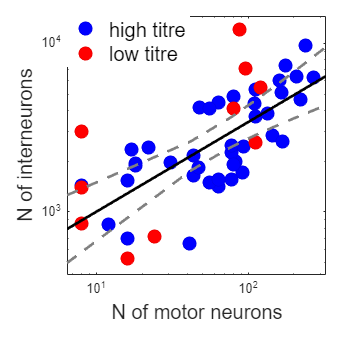

% Figure 4 figure supplement 3
masterdir = 'F:\documents\master\data\';
clearvars -except masterdir masterdir_raw nruns

filename = 'rab_counts_scaled';

datatable = readtable([masterdir,filename],'Sheet','Sheet2');

all_mn_log = vertcat( log10(datatable.mnhigh(~isnan(datatable.mnhigh))),log10(datatable.mnlow(~isnan(datatable.mnlow))));
all_in_log = vertcat( log10(datatable.inhigh(~isnan(datatable.inhigh))),log10(datatable.inlow(~isnan(datatable.inlow))));

xl = [0.8*10^min(all_mn_log), 1.2*10^max(all_mn_log)];
yl = [0.8*10^min(all_in_log), 1.2*10^max(all_in_log)];

% figure settings
lwconv = 2;   %line weidth  
inmarkersize= 10;
nr1 = 1;               % Number of rows in panel grid
nc1 = 1;               % Number of columns in panel grid
sizex1 = 5;           % Absolute width of figure (in cm)
sizey1 = 5;            % Absolute height of figure (in cm)         
margx = 0.1;           % x-margin between and around panels (normalised units)
margy = 0.1;           % y-margin between and around panels (normalised units)
labelalign = 'sw';     % NESW alignment of labels
labelfsize = 18;       % Label font size


[ff, gof, fitoutput] = fit(all_mn_log,all_in_log,'poly1' );
ci = confint(ff);
xx = linspace(xl(1),xl(2),10);
yy = 10^ff.p2*xx.^ff.p1;
yylin = ff.p2 + ff.p1*log10(xx);
yyplus = predint(ff,log10(xx),0.95,'functional','on');

f1 = figure;
set(f1,'Position',[10 10 f1.Position(3) f1.Position(4)])
h = 0;

Panels = panels([nr1, nc1], [sizex1, sizey1], 1, [margx, margy]); % Initialise panel class instance
Panels.setLabels(Panels.lbl, labelalign, labelfsize); 
Panels.tweak(1,[0.15,0.15],[0.8,0.8]);




h = 1;
in_vs_mn = Panels.setPanel(h);

highplot = plot ((datatable.mnhigh),(datatable.inhigh),'o');
set(highplot,'MarkerSize',inmarkersize,'MarkerFaceColor',[0,0,1],'MarkerEdgeColor',[0,0,0.9])
hold on
lowplot = plot ((datatable.mnlow),(datatable.inlow),'o');
set(lowplot,'MarkerSize',inmarkersize,'MarkerFaceColor',[1,0,0],'MarkerEdgeColor',[0.9,0,0])
fitplot = plot(xx,yy,'-');
set(fitplot,'LineWidth',lwconv, 'Color', [0,0,0],'LineStyle','-')
confplot = plot((xx),10.^yyplus);
set(confplot,'LineWidth',lwconv, 'Color', [0.5,0.5,0.5],'LineStyle','--')

ax = gca;
set(ax,'Xscal','log','YScale','log','XLim',xl,'YLim',yl);
set(ax.XLabel, 'String','N of motor neurons','FontName','Arial','FontSize',15);
set(ax.YLabel, 'String','N of interneurons','FontName','Arial','FontSize',15);

 ll = legend([highplot, lowplot],{'high titre','low titre'});
         set (ll, 'Position',[0.3 0.83 0.1 0.1119], 'Box','off', 'FOntSize',15,'FontName','Arial' )

 Panels.addPanels();

***Figure 4 figure supplement 3****: the relation between the number of primary infected motor neurons and premotor interneurons follow a power law y = axb with a = 295 (155, 561 confidence intervals) and b = 0.53 (0.37, 0.69 confidence intervals), R2 = 0.48. Motor neuron and interneuron numbers in each experiment are shown for high (red) and low (black) titre experiments. The fitted line represents a power law. *

# Figure 7-figure supplement 1

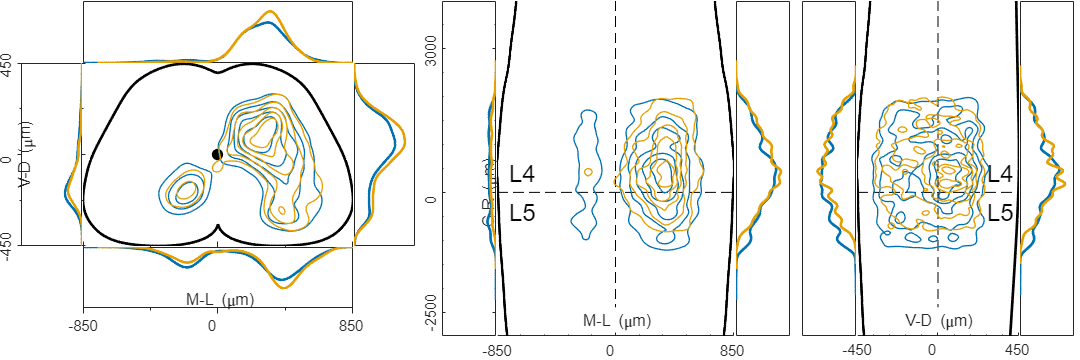

masterdir = 'F:\documents\master\data\';
clearvars -except masterdir
ExpTypeString = {'chat', 'olig2','aav_wt',...
    'aav_chat','prv'};
MuscleType = {'lg','mg','gs','ta','pl'};
MuscleTypeSecond = {'nil', 'lg','mg','gs','ta','pl'};
ext = 'xlsx';
ExpType = {'olig2'}; 
firstmuscle = {'gs'};
secondmuscle = {'ta'};
titer = 'high'; % can be 'high' or 'low'
concat = 1;
% Defines folders for each muscles and number of muscles

firstmuscledir = [masterdir,firstmuscle{1},'_',ExpType{1},'\'];
if ~isfolder(firstmuscledir)
    disp ('Please pick another first muscle: LG, MG and PL were injected only for experiments on ChAT-PhiGT, GS and TA were injected in all other experiments')
    firstfiles = [];
    return
else
    firstfiles = dir([firstmuscledir,'*.',ext]);
end

yes_second = ~contains(secondmuscle,'nil');

if yes_second
    secondmuscledir = [masterdir,secondmuscle{1},'_',ExpType{1},'\'];
    if ~isfolder(secondmuscledir)
        disp ('Please pick another second muscle: LG, MG and PL were injected only for experiments on ChAT-PhiGT, GS and TA were injected in all 9other experiments')
        secondfiles = [];
        return
    else
        secondfiles = dir([secondmuscledir,'*.',ext]);
    end
else
end

% [fnfirst,pathfirst] =  uigetfile([firstmuscledir,'*.xlsx'],'Select One or more files for first muscle', ...
%            'MultiSelect', 'on');
 fnfirst = {firstfiles(:).name}; %picks all files from first directory
 pathfirst = firstmuscledir;

if yes_second
%     [fnsecond,pathsecond] =  uigetfile([secondmuscledir,'*.xlsx'],'Select One or more files for second muscle', ...
%             'MultiSelect', 'on');    
    fnsecond = {secondfiles(:).name}; %picks all files from second directory
    pathsecond = secondmuscledir;
    nfiles_ = [length(string(fnfirst)), length(string(fnsecond))];
    dn = {pathfirst,pathsecond};
else   
    nfiles_ = length(string(fnfirst)); %here and above: string must be used to accommodate for single files
    dn = {pathfirst};
end
ndir = length(dn);

% declares all cell and matrix variables
ins = cell(1,ndir);
mns = cell(1,ndir);
gckin = cell(1,ndir);
gckmn = cell(1,ndir);
gckinxz = cell(1,ndir);
gckmnxz = cell(1,ndir);
gckinyz = cell(1,ndir);
gckmnyz = cell(1,ndir);

nfiles = [];
ptpeak = [];
prpeak = [];
plpeak = [];
pbpeak = [];
peakcontraxz = [];
peakipsixz = [];
peakcontrayz = [];
peakipsiyz = [];

% First index is the directory, second is file the extra i is to
% accommodate for choice of single files in order to keep the string format

if nfiles_(1)==1
    ins_{1}{1} = readmatrix([dn{1},fnfirst], 'Sheet',1);
    mns_{1}{1} = readmatrix([dn{1},fnfirst], 'Sheet',2);
else
    for j = 1:nfiles_(1)
        ins_{1}{j} = readmatrix([dn{1},fnfirst{j}], 'Sheet',1);
        mns_{1}{j} = readmatrix([dn{1},fnfirst{j}], 'Sheet',2);
    end
end

if size(nfiles_,2)==2
    if nfiles_(2) ==1
        ins_{2}{1} = readmatrix([dn{2},fnsecond], 'Sheet',1);
        mns_{2}{1} = readmatrix([dn{2},fnsecond], 'Sheet',2);
    else
        for j = 1:nfiles_(2)
            ins_{2}{j} = readmatrix([dn{2},fnsecond{j}], 'Sheet',1);
            mns_{2}{j} = readmatrix([dn{2},fnsecond{j}], 'Sheet',2);
        end
    end
else
end



if concat == 1
    for  i = 1:ndir
        % the extra {1} is to make it compatible with codes using
        % two indexes if files are not concatenated
        ins{i}{1} = vertcat(ins_{i}{:});
        mns{i}{1} = vertcat(mns_{i}{:});
    end
else
    for i = 1:ndir
        for j = 1:nfiles_(i)
            ins{i}{j} = ins_{i}{j};
            mns{i}{j} = mns_{i}{j};
        end
    end
end

% rewrite nfiles after concatenation
for i = 1:ndir
    nfiles(i) = size(ins{i},2);
end

%[ins,mns] = poolfun(dn,concat); % ins and mns have the same dimensions 

MNON = false; MNONPROJ = false;
qq = 6;
dotson = 0;
contlevlong = 5;
contlevtrans = 5;


% figure settings
autoscale = 1; % Set autoscale on Y axis of interneurons densities
ker = [5,5];          % kernel size
res = [100,100];         % kernel resolution

nr1 = 3;               % Number of rows in panel grid
nc1 = 9;               % Number of columns in panel grid
sizex1 = 15;           % Absolute width of figure (in cm)
sizey1 = 5;            % Absolute height of figure (in cm)         
margx = 0.1;           % x-margin between and around panels (normalised units)
margy = 0.1;           % y-margin between and around panels (normalised units)
labelalign = 'sw';     % NESW alignment of labels
labelfsize = 18;       % Label font size
% contlevlong = 5;       % contour levels for xz and yz plots
% contlevtrans = 5;      % contour levels for transverse slice
inmarkersize=2;        % size of Mn marker
mnmarkersize=5;        % size of Mn marker
mnlw = 0.01;            % width of Mn edge marker
contlw =1;             % line width for contours
lwconv = 2;            % line width of convolution plots

% loads tab files with sc profiles
scp = readmatrix('halfcordt.txt'); %transverse
scf = readmatrix('halfcordf.txt');  % frontal
sclv = readmatrix('halfcordf.txt');  % lateral ventral, same as frontal
scld = readmatrix('halfcordld.txt');  % lateral dorsal

if  isempty(mns)
    mns = [0,0,0];
    mnmarkersize=0;
    mnlw = 0;
end

   xl = [-.5,.5]; 
   yl = [-0.5,0.5];

    zl = [-4000,3000];
    plim = [0,0.01]; % these settings are overridden if autoscale is on
    plimz = [0,2e-5];
    plimlong = [0,0.23];
    
% color matrix: creates a matrix of colours scaling the primary colors to
% darker shades for increasing n of experiment. First index is directory,
% second is file

first = [0, 114, 178]/255; %{0, 0.4471, 0.6980}  %blu = 1st directory LG
firstdark = [0, 114, 178]/450; %{0, 0.2533, 0.3956} %dark blu = 2nd directory = MG
second = [230, 159, 0]/255;  %{0.9020, 0.6235,0} orange = TA inhibitory
seconddark = [180/255, 100/255, 0]; %{0.7059, 0.3922, 0} dark orange = TA excitatory
third = [0,0,1];

switch string(firstmuscle)
    case 'lg'
        primarycols{1} = first;
    case 'mg'
        primarycols{1} = firstdark;
    case 'gs'
        primarycols{1} = first;
    case 'ta'
        primarycols{1} = second;
    case 'pl'
        primarycols{1} = seconddark;
end

if yes_second
    switch string(secondmuscle)
        case 'lg'
            primarycols{2} = first
        case 'mg'
            primarycols{2} = firstdark;
        case 'gs'
            primarycols{2} = first;
        case 'ta'
            primarycols{2} = second;
        case 'pl'
            primarycols{2} = seconddark;
    end
else
    primarycols{2} = second;
end
primarycols{3} = third;

%primarycols = {first,second,third}; % standard list, GS=green, TA=red
scalecol = cell(1,ndir);
cols = cell(1,ndir);

for i = 1:ndir
   
    if nfiles(i) == 1
        scalecol{i} = 1;
    else
        scalecol{i} = linspace(1,0.5,nfiles(i));
    end
    
    for j = 1:nfiles(i)
    cols{i}{j} = primarycols{i}*scalecol{i}(j);

    end
end

for i = 1:ndir
    for j = 1:nfiles(i)
        gckin{i}{j} = gckernel();
        gckmn{i}{j} = gckernel();
        gckinxz{i}{j} = gckernel();
        gckmnxz{i}{j} = gckernel();
        gckinyz{i}{j} = gckernel();
        gckmnyz{i}{j} = gckernel();
      
    end
end
  
for i = 1:ndir
    for j = 1:nfiles(i)
        gckin{i}{j}.setData([ins{i}{j}(:,1)'; ins{i}{j}(:,2)'], [std(ins{i}{j}(:,1))/qq,std(ins{i}{j}(:,1))/qq]);
        gckin{i}{j}.convolve([ins{i}{j}(:,1)'; ins{i}{j}(:,2)']);
        %nomn = ~isempty(mns{i}{j}); %REPLACE NOMN WITH size(mns{i}{j}) for cases with 1 Mn only
        nmn = size(mns{i}{j},1);
        if nmn>1
            gckmn{i}{j}.convolve([mns{i}{j}(:,1)'; mns{i}{j}(:,2)']);
            gckmnxz{i}{j}.convolve([mns{i}{j}(:,1)'; mns{i}{j}(:,3)']);
        else
            
        end
        setKernel(gckin{i}{j},ker);
        setResd(gckin{i}{j},res);
        setKernel(gckinxz{i}{j},ker);
        setResd(gckinxz{i}{j},res);
        setKernel(gckinyz{i}{j},ker);
        setResd(gckinyz{i}{j},res);
        gckinxz{i}{j}.setData([ins{i}{j}(:,1)'; ins{i}{j}(:,3)'],[std(ins{i}{j}(:,1))/qq,std(ins{i}{j}(:,1))/qq]);
        gckinyz{i}{j}.setData([ins{i}{j}(:,2)'; ins{i}{j}(:,3)'],[std(ins{i}{j}(:,1))/qq,std(ins{i}{j}(:,1))/qq]);
        gckinxz{i}{j}.convolve([ins{i}{j}(:,1)'; ins{i}{j}(:,3)']);
        gckinyz{i}{j}.convolve([ins{i}{j}(:,2)'; ins{i}{j}(:,3)']);
        
    end
end

% OUTPUT FIGURE 1
f1 = figure;
%set(f1,'Position',[10 10 f1.Position(3) f1.Position(4)]);
set(f1,'Position',[10 10 1500 500]);
h = 0;
% aa = annotation('line', [0.14,0.25],[0.05,0.05]);
% aa.LineWidth = lwconv;
% annotation('textbox', [0.165,0.11,0.05,0.03],'String','1 mm','LineStyle','none','FontSize',15,'FitBoxToText','on');
% annotation('doublearrow', [0.805,0.935],[0.05,0.05]);
% annotation('textbox', [0.815,0.1,0.03,0.03],'String','V','LineStyle','none','FontSize',15,'FitBoxToText','on');
% annotation('textbox', [0.895,0.1,0.03,0.03],'String','D','LineStyle','none','FontSize',15,'FitBoxToText','on');
Panels = panels([nr1, nc1], [sizex1, sizey1], 1, [margx, margy]); % Initialise panel class instance
Panels.setLabels(Panels.lbl, labelalign, labelfsize);  

Panels.tweak(2,[-0.4,0.42],[2.5,0.5682]);
Panels.tweak(20,[-0.4,0.37],[2.5,0.5682]);
Panels.tweak(10,[0.14,-0.17],[0.5682,1.7]);
Panels.tweak(12,[1.0,-0.17],[0.5682,1.7]);
Panels.tweak(11,[-0.4,-0.17],[2.5,1.7]);
Panels.tweak(14,[0.1,-1.],[2.2,3.1]);
Panels.tweak(13,[0.7,-1.],[0.5,3.1]);
Panels.tweak(15,[1.2,-1.],[0.5,3.1]);
Panels.tweak(17,[0.1,-1.0],[1.5,3.1]);
Panels.tweak(16,[0.7,-1.0],[0.5,3.1]);
Panels.tweak(18,[0.5,-1.0],[0.5,3.1]);


h = 11;
dotxy = Panels.setPanel(h);
cc = plot (0,0,'ko');
    set(cc,'MarkerFaceColor',[0,0,0],'MarkerSize',8)
    hold on
plot(2*xl(2)*scp(:,1),2*yl(2)*scp(:,2),'LineWidth',lwconv,'Color','k'); %right halfcord
plot(-2*xl(2)*scp(:,1),2*yl(2)*scp(:,2),'LineWidth',lwconv,'Color','k'); %left halfcord
 for i = 1:ndir
    for j = 1:nfiles(i)
         x = gckin{i}{j}.x;
         y = gckin{i}{j}.y;
         P = gckin{i}{j}.P;
         
         if dotson
             inpl = plot(ins{i}{j}(:,1),ins{i}{j}(:,2),'.','MarkerEdgeColor',...
                 cols{i}{j},'MarkerSize',inmarkersize);
         else
             [MM,contu] = contour(x,y,P,contlevtrans);
             set(contu,'LineColor',cols{i}{j},'LineWidth',contlw );
         end
         
         nomn = ~isempty(mns{i}{j});
         if nomn && MNON
             mnpl = plot(mns{i}{j}(:,1),mns{i}{j}(:,2),'r^', 'MarkerSize',mnmarkersize,...
                 'MarkerFaceColor',cols{i}{j},'MarkerEdgeColor','k','LineWidth',mnlw);
         else
             
         end
            ax = gca;
         set (ax, 'xlim',xl, 'ylim',yl,'Visible','off','XTick',[],'YTick',[])
 box off
    end
 end

h = 2;
top = Panels.setPanel(h);
for i = 1:ndir
    for j = 1:nfiles(i)
         x = gckin{i}{j}.x;
         y = gckin{i}{j}.y;
         P = gckin{i}{j}.P;
         pt = sum( P(y>=0,:),1);
         ptpeak(i,j) = max(max(pt));
         topplot = plot(x,pt);
         %sum(pt)
         hold on
         set(topplot,'color',cols{i}{j}, 'LineWidth',lwconv);
         ax = gca;
         set(ax,'xlim', xl,'ylim',plim,'XTick',[],'YTick',[])         
 
    end
end

h = 12;
right = Panels.setPanel(h);
for i = 1:ndir
    for j = 1:nfiles(i)
         x = gckin{i}{j}.x;
         y = gckin{i}{j}.y;
         P = gckin{i}{j}.P;
         pr = sum( P(:,x>=0),2);
         prpeak(i,j) = max(max(pr));
         rightplot = plot(pr,y);
         hold on
         if MNONPROJ
             xmn = gckmn{i}{j}.x;
             ymn = gckmn{i}{j}.y;
             Pmn = gckmn{i}{j}.P;
             prmn = sum( Pmn(:,:),2);
             rightplotmn = plot(prmn,ymn);
             set(rightplotmn,'color',cols{i}{j}, 'LineStyle',':','LineWidth',lwconv);
         else
         end
         set(rightplot,'color',cols{i}{j}, 'LineWidth',lwconv);
         ax = gca;
         set(ax,'xlim',plim,'ylim', yl,'XTick',[],'YTick',[])   ;     

    end
end

h = 10;
left = Panels.setPanel(h);
for i = 1:ndir
    for j = 1:nfiles(i)   
         x = gckin{i}{j}.x;
         y = gckin{i}{j}.y;
         P = gckin{i}{j}.P;
         pl = sum( P(:,x<0),2);
         plpeak(i,j) = max(max(pl));
         leftplot = plot(pl,y);
         hold on
         set(leftplot,'color',cols{i}{j}, 'LineWidth',lwconv);
         ax = gca;
         set(ax,'ylim', yl,'xlim',plim,'xdir','reverse','XTick',[],...
             'YTick',[-0.5,0, 0.5],'YTickLabel',[-450,0,450],'YTickLabelRotation',90,...
         'TickLabelInterpreter','tex')   ;
         set(ax.YLabel,'Interpreter','tex');
         ax.YLabel.String = 'V-D (\mum)';
         ax.YLabel.Position = [0.0065 4.7684e-07];
         ax.YAxis.FontSize = 11;
         ax.YAxis.FontName = 'arial';
         ax.YAxis.MinorTick = 'on';
         ax.YAxis.MinorTickValues = [-0.5,-0.25,0,0.25,0.5]; 
         ax.YAxis.TickDirection = 'out';
         ax.YAxis.TickLength = [0.0200 0.0250];
    end
end

h = 20;
bot = Panels.setPanel(h);
for i = 1:ndir
    for j = 1:nfiles(i)   
         x = gckin{i}{j}.x;
         y = gckin{i}{j}.y;
         P = gckin{i}{j}.P;
         pb = sum( P(y<0,:),1);
         pbpeak(i,j) = max(max(pb));
         botplot = plot(x,pb);
         %sum(pb)
         hold on
        
         if MNONPROJ
             x = gckmn{i}{j}.x;
             y = gckmn{i}{j}.y;
             P = gckmn{i}{j}.P;
             pb = sum( P(:,:),1);
             botplotmn = plot(x,pb);
             set(botplotmn,'color',cols{i}{j}, 'LineStyle',':','LineWidth',lwconv);
         else
         end
         
         set(botplot,'color',cols{i}{j}, 'LineWidth',lwconv);
         ax = gca;
         set(ax,'xlim', xl,'ylim',plim,'ydir','reverse',...
             'XTick',[-0.5,0, 0.5],'XTickLabel',[-850,0,850],'YTick',[])   ; 
         set(ax.XLabel,'Interpreter','tex');
         ax.XLabel.String = 'M-L (\mum)';
         ax.XLabel.Position = [0.0065 0.006];
         ax.XAxis.FontSize = 11;
         ax.XAxis.FontName = 'arial';
         ax.XAxis.MinorTick = 'on';
         ax.XAxis.MinorTickValues = [-0.5,-0.25,0,0.25,0.5]; 
         ax.XAxis.TickDirection = 'out';
         ax.XAxis.TickLength = [0.0200 0.0250];

    end
end

% longitudinal xz

h = 13;
 contraxz = Panels.setPanel(h);
 for i = 1:ndir
    for j = 1:nfiles(i)
         x = gckinxz{i}{j}.x;
         y = gckinxz{i}{j}.y;
         P = gckinxz{i}{j}.P;
         pcontraxz = sum( P(:,x<0),2);
         plotcontra = plot(pcontraxz,y);
         peakcontraxz(i,j) = max(max(pcontraxz));
         hold on
         set (plotcontra,'color',cols{i}{j}, 'LineWidth',lwconv)
         ax  = gca;
         set (ax, 'ylim',zl,'xlim',plimlong,'xdir','reverse','ydir','reverse',...
             'XTick',[],'YTick',[-3000,0,2500],'YTickLabel',[3000,0,-2500],...
             'YTickLabelRotation',90)
         set(ax.YLabel,'Interpreter','tex');
         ax.YLabel.String = 'C-R (\mum)';
          ax.YLabel.Position = [-0.0015 4.7684e-07];
%         ax.YLabel.Position = [0.13 4.7684e-07];
         ax.YAxis.FontSize = 11;
         ax.YAxis.FontName = 'arial';
         ax.YAxis.MinorTick = 'on';

    end
 end
 
 
h=14;
dotxz = Panels.setPanel(h);
cc = plot ([0,0],[zl(1),0.8*zl(2)],'k','LineStyle','--');
        set(cc,'MarkerFaceColor',[0,0,0],'MarkerSize',8)
        hold on
plot(2*xl(2)*scf(:,1),-2*zl(2)*scf(:,2),'LineWidth',lwconv,'Color','k'); %right halfcord
plot(-2*xl(2)*scf(:,1),-2*zl(2)*scf(:,2),'LineWidth',lwconv,'Color','k'); %left halfcord 
plot(xl,[0,0],'k','LineStyle','--') 
        text(0.9*xl(1),400,'L5', 'FontSize', 18);
        text(0.9*xl(1),-400,'L4', 'FontSize', 18);
for i = 1:ndir
    for j = 1:nfiles(i)
         x = gckinxz{i}{j}.x;
         y = gckinxz{i}{j}.y;
         P = gckinxz{i}{j}.P;
         if dotson
             dotpl = plot(ins{i}{j}(:,1),ins{i}{j}(:,3),'.','MarkerSize',inmarkersize,...
                 'MarkerEdgeColor',cols{i}{j});
         else
             [MM,contu] = contour(x,y,P,contlevlong);
             set(contu,'LineColor',cols{i}{j},'LineWidth',contlw );
         end
        
         nomn = ~isempty(mns{i}{j});
         if nomn && MNON
             mnpl = plot(mns{i}{j}(:,1),mns{i}{j}(:,3),'r^', 'MarkerSize',mnmarkersize,...
                 'MarkerFaceColor',cols{i}{j},'MarkerEdgeColor','k','LineWidth',mnlw);
         else
         end
         
        ax = gca;
        set (ax, 'xlim',yl, 'ylim',zl,'XTick',[-0.5,0,0.5],'XTickLabels',[-850,0,850],...
            'YTick',[], 'ydir','reverse','YColor', [1 1 1])
         set(ax.XLabel,'Interpreter','tex');
         ax.XLabel.String = 'M-L (\mum)';
         ax.XLabel.Position = [0.0065 2500];
         ax.XAxis.FontSize = 11;
         ax.XAxis.FontName = 'arial';
         ax.XAxis.MinorTick = 'on';
  box off
    end
end


h = 15;
 ipsixz = Panels.setPanel(h);
 for i = 1:ndir
    for j = 1:nfiles(i)  
         x = gckinxz{i}{j}.x;
         y = gckinxz{i}{j}.y;
         P = gckinxz{i}{j}.P;
         pipsixz = sum( P(:,x>=0),2);
         peakipsixz(i,j) = max(max(pipsixz));         
         plotipsi = plot(pipsixz,y);
         hold on
         set (plotipsi,'color',cols{i}{j}, 'LineWidth',lwconv)
         ax  = gca;
         set (ax, 'ylim',zl,'xlim',plimlong,'ydir','reverse','XTick',[],'YTick',[])
    
    end
 end

% longitudinal yz

h = 16;
 contrayz = Panels.setPanel(h);
 for i = 1:ndir
    for j = 1:nfiles(i)
         x = gckinyz{i}{j}.x;
         y = gckinyz{i}{j}.y;
         P = gckinyz{i}{j}.P;
         pcontrayz = sum( P(:,x<0),2);
         peakcontrayz(i,j) = max(max(pcontrayz));
         plotcontra = plot(pcontrayz,y);
         hold on
         set (plotcontra,'color',cols{i}{j}, 'LineWidth',lwconv)
         ax  = gca;
         set (ax, 'ylim',zl,'xlim',plimlong,'xdir','reverse','ydir','reverse','XTick',[],'YTick',[])

    end
 end
 
 
h=17;
dotxz = Panels.setPanel(h);
cc = plot ([0,0],[zl(1),0.8*zl(2)],'k','LineStyle','--');
        set(cc,'MarkerFaceColor',[0,0,0],'MarkerSize',8)
        hold on
plot(-2*yl(2)*sclv(:,1),-2*zl(2)*sclv(:,2),'LineWidth',lwconv,'Color','k'); %ventral halfcord
plot(2*yl(2)*scld(:,1),-2*zl(2)*scld(:,2),'LineWidth',lwconv,'Color','k'); %dorsal halfcord
plot(xl,[0,0],'k','LineStyle','--') 
        text(0.6*yl(2),400,'L5', 'FontSize', 18);
        text(0.6*yl(2),-400,'L4', 'FontSize', 18);
for i = 1:ndir
    for j = 1:nfiles(i)   
         x = gckinyz{i}{j}.x;
         y = gckinyz{i}{j}.y;
         P = gckinyz{i}{j}.P;
         if dotson
             dotpl = plot(ins{i}{j}(:,2),ins{i}{j}(:,3),'.','MarkerSize',inmarkersize,...
                 'MarkerEdgeColor',cols{i}{j});
         else
             [MM,contu] = contour(x,y,P,contlevlong);
             set(contu,'LineColor',cols{i}{j},'LineWidth',contlw );
         end
        
         nomn = ~isempty(mns{i}{j});
         if nomn && MNON
             mnpl = plot(mns{i}{j}(:,2),mns{i}{j}(:,3),'r^', 'MarkerSize',mnmarkersize,...
                 'MarkerFaceColor',cols{i}{j},'MarkerEdgeColor','k','LineWidth',mnlw);
         else
         end
         
        ax = gca;
        set (ax, 'xlim',yl, 'ylim',zl,'XTick',[-0.5,0,0.5],'XTickLabels',[-450,0,450],...
            'YTick',[], 'ydir','reverse','YColor', [1 1 1])
         set(ax.XLabel,'Interpreter','tex');
         ax.XLabel.String = 'V-D (\mum)';
         ax.XLabel.Position = [0.0065 2500];
         ax.XAxis.FontSize = 11;
         ax.XAxis.FontName = 'arial';
         ax.XAxis.MinorTick = 'on';
  box off
    end
end


h = 18;
 ipsiyz = Panels.setPanel(h);
 for i = 1:ndir
    for j = 1:nfiles(i)   
         x = gckinyz{i}{j}.x;
         y = gckinyz{i}{j}.y;
         P = gckinyz{i}{j}.P;
         pipsiyz = sum( P(:,x>=0),2);
         peakipsiyz(i,j) = max(max(pipsiyz));
         plotipsi = plot(pipsiyz,y);
         hold on
         set (plotipsi,'color',cols{i}{j}, 'LineWidth',lwconv)
         ax  = gca;
         set (ax, 'ylim',zl,'xlim',plimlong,'ydir','reverse','XTick',[],'YTick',[])
    
    end
 end

 %%%%%%%%%% final assignment of axes limits to allow autoscale following
%%%%%%%%%% changes in kernel resolution

if autoscale
    %% transverse projection
    set(top, 'YLim',[0,1.2*max(max(max(ptpeak,pbpeak)))]); % pt and pb are row vectors
    set(bot, 'YLim',[0,1.2*max(max(max(ptpeak,pbpeak)))]);
    set(left, 'XLim',[0,1.2*max(max(max(plpeak,prpeak)))]); %pl and pr are column vector
    set(right, 'XLim',[0,1.2*max(max(max(plpeak,prpeak)))]);
    %% xz projection
    set(contraxz, 'XLim',[0,1.2*max(max(max(peakcontraxz,peakipsixz)))]);
    set(ipsixz, 'XLim',[0,1.2*max(max(max(peakcontraxz,peakipsixz)))]);
    %% yz projection
    set(contrayz, 'XLim',[0,1.2*max(max(max(peakcontrayz,peakipsiyz)))]);
    set(ipsiyz, 'XLim',[0,1.2*max(max(max(peakcontrayz,peakipsiyz)))]);
else
end

Panels.addPanels();

***Figure 7 figure supplement 1****: distribution of flexor and extensor premotor interneurons pooled across GS and TA injections performed in Olig2::Cre; RFGT mice. Distributions are shown in the transverse plane (left) and as front (middle) and lateral (right) view along the rostrocaudal axis*

# Figure 12, all figure supplements

The code below allows to plot indivdual or multiple experiments. Once the type of experiment is chosen, there is a choice of plotting one or two muscles simultaneously. Experiments can be either pooled or shown individually in different shades of colours. The colour code for each muscle mirrors the one in the paper

masterdir = 'F:\documents\master\data\';
clearvars -except masterdir
ExpTypeString = {'chat', 'olig2','aav_wt',...
    'aav_chat','prv'};
MuscleType = {'lg','mg','gs','ta','pl'};
MuscleTypeSecond = {'nil', 'lg','mg','gs','ta','pl'};

ext = 'xlsx';
ExpType = ExpTypeString(1);
firstmuscle = MuscleType(1);
secondmuscle = MuscleTypeSecond(5);
concat = false;
labpos =0.35; % set position of file name label
% Defines folders for each muscles and number of muscles

firstmuscledir = [masterdir,firstmuscle{1},'_',ExpType{1},'\'];
if ~isfolder(firstmuscledir)
    disp ('Please pick another first muscle: LG, MG and PL were injected only for experiments on ChAT-PhiGT, GS and TA were injected in all other experiments')
    firstfiles = [];
    return
else
    firstfiles = dir([firstmuscledir,'*.',ext]);
end

yes_second = ~contains(secondmuscle,'nil');

if yes_second
    secondmuscledir = [masterdir,secondmuscle{1},'_',ExpType{1},'\'];
    if ~isfolder(secondmuscledir)
        disp ('Please pick another second muscle: LG, MG and PL were injected only for experiments on ChAT-PhiGT, GS and TA were injected in all 9other experiments')
        secondfiles = [];
        return
    else
        secondfiles = dir([secondmuscledir,'*.',ext]);
    end
else
end

[fnfirst,pathfirst] =  uigetfile([firstmuscledir,'*.xlsx'],'Select One or more files for first muscle', ...
            'MultiSelect', 'on');

if yes_second
    [fnsecond,pathsecond] =  uigetfile([secondmuscledir,'*.xlsx'],'Select One or more files for second muscle', ...
            'MultiSelect', 'on');    
    nfiles_ = [length(string(fnfirst)), length(string(fnsecond))];
    dn = {pathfirst,pathsecond};
else   
    nfiles_ = length(string(fnfirst)); %here and above: string must be used to accommodate for single files
    dn = {pathfirst};
end
ndir = length(dn);

% declares all cell and matrix variables
ins = cell(1,ndir);
mns = cell(1,ndir);
gckin = cell(1,ndir);
gckmn = cell(1,ndir);
gckinxz = cell(1,ndir);
gckmnxz = cell(1,ndir);
gckinyz = cell(1,ndir);
gckmnyz = cell(1,ndir);

nfiles = [];
ptpeak = [];
prpeak = [];
plpeak = [];
pbpeak = [];
peakcontraxz = [];
peakipsixz = [];
peakcontrayz = [];
peakipsiyz = [];

% First index is the directory, second is file the extra i is to
% accommodate for choice of single files in order to keep the string format

if nfiles_(1)==1
    ins_{1}{1} = readmatrix([dn{1},fnfirst], 'Sheet',1);
    mns_{1}{1} = readmatrix([dn{1},fnfirst], 'Sheet',2);
else
    for j = 1:nfiles_(1)
        ins_{1}{j} = readmatrix([dn{1},fnfirst{j}], 'Sheet',1);
        mns_{1}{j} = readmatrix([dn{1},fnfirst{j}], 'Sheet',2);
    end
end

if size(nfiles_,2)==2
    if nfiles_(2) ==1
        ins_{2}{1} = readmatrix([dn{2},fnsecond], 'Sheet',1);
        mns_{2}{1} = readmatrix([dn{2},fnsecond], 'Sheet',2);
    else
        for j = 1:nfiles_(2)
            ins_{2}{j} = readmatrix([dn{2},fnsecond{j}], 'Sheet',1);
            mns_{2}{j} = readmatrix([dn{2},fnsecond{j}], 'Sheet',2);
        end
    end
else
end



if concat == 1
    for  i = 1:ndir
        % the extra {1} is to make it compatible with codes using
        % two indexes if files are not concatenated
        ins{i}{1} = vertcat(ins_{i}{:});
        mns{i}{1} = vertcat(mns_{i}{:});
    end
else
    for i = 1:ndir
        for j = 1:nfiles_(i)
            ins{i}{j} = ins_{i}{j};
            mns{i}{j} = mns_{i}{j};
        end
    end
end

% rewrite nfiles after concatenation
for i = 1:ndir
    nfiles(i) = size(ins{i},2);
end

%[ins,mns] = poolfun(dn,concat); % ins and mns have the same dimensions 

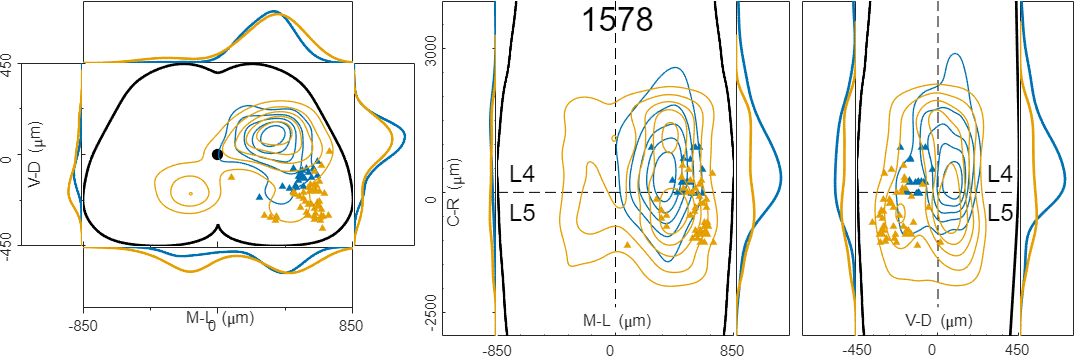



MNON = true; MNONPROJ = false;
qq = 3.1;
dotson = 0;
contlevlong = 5;
contlevtrans = 5;

% figure settings
autoscale = 1; % Set autoscale on Y axis of interneurons densities
ker = [5,5];          % kernel size
res = [100,100];         % kernel resolution

nr1 = 3;               % Number of rows in panel grid
nc1 = 9;               % Number of columns in panel grid
sizex1 = 15;           % Absolute width of figure (in cm)
sizey1 = 5;            % Absolute height of figure (in cm)         
margx = 0.1;           % x-margin between and around panels (normalised units)
margy = 0.1;           % y-margin between and around panels (normalised units)
labelalign = 'sw';     % NESW alignment of labels
labelfsize = 18;       % Label font size
% contlevlong = 5;       % contour levels for xz and yz plots
% contlevtrans = 5;      % contour levels for transverse slice
inmarkersize=2;        % size of Mn marker
mnmarkersize=5;        % size of Mn marker
mnlw = 0.01;            % width of Mn edge marker
contlw =1;             % line width for contours
lwconv = 2;            % line width of convolution plots

% loads tab files with sc profiles
scp = readmatrix('halfcordt.txt'); %transverse
scf = readmatrix('halfcordf.txt');  % frontal
sclv = readmatrix('halfcordf.txt');  % lateral ventral, same as frontal
scld = readmatrix('halfcordld.txt');  % lateral dorsal

if  isempty(mns)
    mns = [0,0,0];
    mnmarkersize=0;
    mnlw = 0;
end

   xl = [-.5,.5]; 
   yl = [-0.5,0.5];

    zl = [-4000,3000];
    plim = [0,0.01]; % these settings are overridden if autoscale is on
    plimz = [0,2e-5];
    plimlong = [0,0.23];
    
% color matrix: creates a matrix of colours scaling the primary colors to
% darker shades for increasing n of experiment. First index is directory,
% second is file

first = [0, 114, 178]/255; %{0, 0.4471, 0.6980}  %blu = 1st directory LG
firstdark = [0, 114, 178]/450; %{0, 0.2533, 0.3956} %dark blu = 2nd directory = MG
second = [230, 159, 0]/255;  %{0.9020, 0.6235,0} orange = TA inhibitory
seconddark = [180/255, 100/255, 0]; %{0.7059, 0.3922, 0} dark orange = TA excitatory
third = [0,0,1];

switch string(firstmuscle)
    case 'lg'
        primarycols{1} = first;
    case 'mg'
        primarycols{1} = firstdark;
    case 'gs'
        primarycols{1} = first;
    case 'ta'
        primarycols{1} = second;
    case 'pl'
        primarycols{1} = seconddark;
end

if yes_second
    switch string(secondmuscle)
        case 'lg'
            primarycols{2} = first;
        case 'mg'
            primarycols{2} = firstdark;
        case 'gs'
            primarycols{2} = first;
        case 'ta'
            primarycols{2} = second;
        case 'pl'
            primarycols{2} = seconddark;
    end
else
    primarycols{2} = second;
end
primarycols{3} = third;

%primarycols = {first,second,third}; % standard list, GS=green, TA=red
scalecol = cell(1,ndir);
cols = cell(1,ndir);

for i = 1:ndir
   
    if nfiles(i) == 1
        scalecol{i} = 1;
    else
        scalecol{i} = linspace(1,0.5,nfiles(i));
    end
    
    for j = 1:nfiles(i)
    cols{i}{j} = primarycols{i}*scalecol{i}(j);

    end
end

for i = 1:ndir
    for j = 1:nfiles(i)
        gckin{i}{j} = gckernel();
        gckmn{i}{j} = gckernel();
        gckinxz{i}{j} = gckernel();
        gckmnxz{i}{j} = gckernel();
        gckinyz{i}{j} = gckernel();
        gckmnyz{i}{j} = gckernel();
      
    end
end
  
for i = 1:ndir
    for j = 1:nfiles(i)
        gckin{i}{j}.setData([ins{i}{j}(:,1)'; ins{i}{j}(:,2)'], [std(ins{i}{j}(:,1))/qq,std(ins{i}{j}(:,1))/qq]);
        gckin{i}{j}.convolve([ins{i}{j}(:,1)'; ins{i}{j}(:,2)']);
        %nomn = ~isempty(mns{i}{j}); %REPLACE NOMN WITH size(mns{i}{j}) for cases with 1 Mn only
        nmn = size(mns{i}{j},1);
        if nmn>1
            gckmn{i}{j}.convolve([mns{i}{j}(:,1)'; mns{i}{j}(:,2)']);
            gckmnxz{i}{j}.convolve([mns{i}{j}(:,1)'; mns{i}{j}(:,3)']);
        else
            
        end
        setKernel(gckin{i}{j},ker);
        setResd(gckin{i}{j},res);
        setKernel(gckinxz{i}{j},ker);
        setResd(gckinxz{i}{j},res);
        setKernel(gckinyz{i}{j},ker);
        setResd(gckinyz{i}{j},res);
        gckinxz{i}{j}.setData([ins{i}{j}(:,1)'; ins{i}{j}(:,3)'],[std(ins{i}{j}(:,1))/qq,std(ins{i}{j}(:,1))/qq]);
        gckinyz{i}{j}.setData([ins{i}{j}(:,2)'; ins{i}{j}(:,3)'],[std(ins{i}{j}(:,1))/qq,std(ins{i}{j}(:,1))/qq]);
        gckinxz{i}{j}.convolve([ins{i}{j}(:,1)'; ins{i}{j}(:,3)']);
        gckinyz{i}{j}.convolve([ins{i}{j}(:,2)'; ins{i}{j}(:,3)']);
        
    end
end

% OUTPUT FIGURE 1
f1 = figure;
%set(f1,'Position',[10 10 f1.Position(3) f1.Position(4)]);
set(f1,'Position',[10 10 1500 500]);
h = 0;
% aa = annotation('line', [0.14,0.25],[0.05,0.05]);
% aa.LineWidth = lwconv;
% annotation('textbox', [0.165,0.11,0.05,0.03],'String','1 mm','LineStyle','none','FontSize',15,'FitBoxToText','on');
% annotation('doublearrow', [0.805,0.935],[0.05,0.05]);
% annotation('textbox', [0.815,0.1,0.03,0.03],'String','V','LineStyle','none','FontSize',15,'FitBoxToText','on');
% annotation('textbox', [0.895,0.1,0.03,0.03],'String','D','LineStyle','none','FontSize',15,'FitBoxToText','on');
Panels = panels([nr1, nc1], [sizex1, sizey1], 1, [margx, margy]); % Initialise panel class instance
Panels.setLabels(Panels.lbl, labelalign, labelfsize);  

Panels.tweak(2,[-0.4,0.42],[2.5,0.5682]);
Panels.tweak(20,[-0.4,0.37],[2.5,0.5682]);
Panels.tweak(10,[0.14,-0.17],[0.5682,1.7]);
Panels.tweak(12,[1.0,-0.17],[0.5682,1.7]);
Panels.tweak(11,[-0.4,-0.17],[2.5,1.7]);
Panels.tweak(14,[0.1,-1.],[2.2,3.1]);
Panels.tweak(13,[0.7,-1.],[0.5,3.1]);
Panels.tweak(15,[1.2,-1.],[0.5,3.1]);
Panels.tweak(17,[0.1,-1.0],[1.5,3.1]);
Panels.tweak(16,[0.7,-1.0],[0.5,3.1]);
Panels.tweak(18,[0.5,-1.0],[0.5,3.1]);


h = 11;
dotxy = Panels.setPanel(h);
cc = plot (0,0,'ko');
    set(cc,'MarkerFaceColor',[0,0,0],'MarkerSize',8)
    hold on
plot(2*xl(2)*scp(:,1),2*yl(2)*scp(:,2),'LineWidth',lwconv,'Color','k'); %right halfcord
plot(-2*xl(2)*scp(:,1),2*yl(2)*scp(:,2),'LineWidth',lwconv,'Color','k'); %left halfcord
 for i = 1:ndir
    for j = 1:nfiles(i)
         x = gckin{i}{j}.x;
         y = gckin{i}{j}.y;
         P = gckin{i}{j}.P;
         
         if dotson
             inpl = plot(ins{i}{j}(:,1),ins{i}{j}(:,2),'.','MarkerEdgeColor',...
                 cols{i}{j},'MarkerSize',inmarkersize);
         else
             [MM,contu] = contour(x,y,P,contlevtrans);
             set(contu,'LineColor',cols{i}{j},'LineWidth',contlw );
         end
         
         nomn = ~isempty(mns{i}{j});
         if nomn && MNON
             mnpl = plot(mns{i}{j}(:,1),mns{i}{j}(:,2),'r^', 'MarkerSize',mnmarkersize,...
                 'MarkerFaceColor',cols{i}{j},'MarkerEdgeColor','k','LineWidth',mnlw);
         else
             
         end
            ax = gca;
         set (ax, 'xlim',xl, 'ylim',yl,'Visible','off','XTick',[],'YTick',[])
 box off
    end
 end

h = 2;
top = Panels.setPanel(h);
for i = 1:ndir
    for j = 1:nfiles(i)
         x = gckin{i}{j}.x;
         y = gckin{i}{j}.y;
         P = gckin{i}{j}.P;
         pt = sum( P(y>=0,:),1);
         ptpeak(i,j) = max(max(pt));
         topplot = plot(x,pt);
         %sum(pt)
         hold on
         set(topplot,'color',cols{i}{j}, 'LineWidth',lwconv);
         ax = gca;
         set(ax,'xlim', xl,'ylim',plim,'XTick',[],'YTick',[])         
 
    end
end

h = 12;
right = Panels.setPanel(h);
for i = 1:ndir
    for j = 1:nfiles(i)
         x = gckin{i}{j}.x;
         y = gckin{i}{j}.y;
         P = gckin{i}{j}.P;
         pr = sum( P(:,x>=0),2);
         prpeak(i,j) = max(max(pr));
         rightplot = plot(pr,y);
         hold on
         if MNONPROJ
             xmn = gckmn{i}{j}.x;
             ymn = gckmn{i}{j}.y;
             Pmn = gckmn{i}{j}.P;
             prmn = sum( Pmn(:,:),2);
             rightplotmn = plot(prmn,ymn);
             set(rightplotmn,'color',cols{i}{j}, 'LineStyle',':','LineWidth',lwconv);
         else
         end
         set(rightplot,'color',cols{i}{j}, 'LineWidth',lwconv);
         ax = gca;
         set(ax,'xlim',plim,'ylim', yl,'XTick',[],'YTick',[])   ;     

    end
end

h = 10;
left = Panels.setPanel(h);
for i = 1:ndir
    for j = 1:nfiles(i)   
         x = gckin{i}{j}.x;
         y = gckin{i}{j}.y;
         P = gckin{i}{j}.P;
         pl = sum( P(:,x<0),2);
         plpeak(i,j) = max(max(pl));
         leftplot = plot(pl,y);
         hold on
         set(leftplot,'color',cols{i}{j}, 'LineWidth',lwconv);
         ax = gca;
         set(ax,'ylim', yl,'xlim',plim,'xdir','reverse','XTick',[],...
             'YTick',[-0.5,0, 0.5],'YTickLabel',[-450,0,450],'YTickLabelRotation',90,...
         'TickLabelInterpreter','tex')   ;
         set(ax.YLabel,'Interpreter','tex');
         ax.YLabel.String = 'V-D (\mum)';
         ax.YLabel.Position = [0.0065 4.7684e-07];
         ax.YAxis.FontSize = 11;
         ax.YAxis.FontName = 'arial';
         ax.YAxis.MinorTick = 'on';
         ax.YAxis.MinorTickValues = [-0.5,-0.25,0,0.25,0.5]; 
         ax.YAxis.TickDirection = 'out';
         ax.YAxis.TickLength = [0.0200 0.0250];
    end
end

h = 20;
bot = Panels.setPanel(h);
for i = 1:ndir
    for j = 1:nfiles(i)   
         x = gckin{i}{j}.x;
         y = gckin{i}{j}.y;
         P = gckin{i}{j}.P;
         pb = sum( P(y<0,:),1);
         pbpeak(i,j) = max(max(pb));
         botplot = plot(x,pb);
         %sum(pb)
         hold on
        
         if MNONPROJ
             x = gckmn{i}{j}.x;
             y = gckmn{i}{j}.y;
             P = gckmn{i}{j}.P;
             pb = sum( P(:,:),1);
             botplotmn = plot(x,pb);
             set(botplotmn,'color',cols{i}{j}, 'LineStyle',':','LineWidth',lwconv);
         else
         end
         
         set(botplot,'color',cols{i}{j}, 'LineWidth',lwconv);
         ax = gca;
         set(ax,'xlim', xl,'ylim',plim,'ydir','reverse',...
             'XTick',[-0.5,0, 0.5],'XTickLabel',[-850,0,850],'YTick',[])   ; 
         set(ax.XLabel,'Interpreter','tex');
         ax.XLabel.String = 'M-L (\mum)';
         ax.XLabel.Position = [0.0065 0.006];
         ax.XAxis.FontSize = 11;
         ax.XAxis.FontName = 'arial';
         ax.XAxis.MinorTick = 'on';
         ax.XAxis.MinorTickValues = [-0.5,-0.25,0,0.25,0.5]; 
         ax.XAxis.TickDirection = 'out';
         ax.XAxis.TickLength = [0.0200 0.0250];

    end
end

% longitudinal xz

h = 13;
 contraxz = Panels.setPanel(h);
 for i = 1:ndir
    for j = 1:nfiles(i)
         x = gckinxz{i}{j}.x;
         y = gckinxz{i}{j}.y;
         P = gckinxz{i}{j}.P;
         pcontraxz = sum( P(:,x<0),2);
         plotcontra = plot(pcontraxz,y);
         peakcontraxz(i,j) = max(max(pcontraxz));
         hold on
         set (plotcontra,'color',cols{i}{j}, 'LineWidth',lwconv)
         ax  = gca;
         set (ax, 'ylim',zl,'xlim',plimlong,'xdir','reverse','ydir','reverse',...
             'XTick',[],'YTick',[-3000,0,2500],'YTickLabel',[3000,0,-2500],...
             'YTickLabelRotation',90)
         set(ax.YLabel,'Interpreter','tex');
         ax.YLabel.String = 'C-R (\mum)';
          ax.YLabel.Position = [-0.0015 4.7684e-07];
%         ax.YLabel.Position = [0.13 4.7684e-07];
         ax.YAxis.FontSize = 11;
         ax.YAxis.FontName = 'arial';
         ax.YAxis.MinorTick = 'on';

    end
 end
 
 
h=14;
dotxz = Panels.setPanel(h);
cc = plot ([0,0],[zl(1),0.8*zl(2)],'k','LineStyle','--');
        set(cc,'MarkerFaceColor',[0,0,0],'MarkerSize',8)
        hold on
plot(2*xl(2)*scf(:,1),-2*zl(2)*scf(:,2),'LineWidth',lwconv,'Color','k'); %right halfcord
plot(-2*xl(2)*scf(:,1),-2*zl(2)*scf(:,2),'LineWidth',lwconv,'Color','k'); %left halfcord 
plot(xl,[0,0],'k','LineStyle','--') 
        text(0.9*xl(1),400,'L5', 'FontSize', 18);
        text(0.9*xl(1),-400,'L4', 'FontSize', 18);
for i = 1:ndir
    for j = 1:nfiles(i)
         x = gckinxz{i}{j}.x;
         y = gckinxz{i}{j}.y;
         P = gckinxz{i}{j}.P;
         if dotson
             dotpl = plot(ins{i}{j}(:,1),ins{i}{j}(:,3),'.','MarkerSize',inmarkersize,...
                 'MarkerEdgeColor',cols{i}{j});
         else
             [MM,contu] = contour(x,y,P,contlevlong);
             set(contu,'LineColor',cols{i}{j},'LineWidth',contlw );
         end
        
         nomn = ~isempty(mns{i}{j});
         if nomn && MNON
             mnpl = plot(mns{i}{j}(:,1),mns{i}{j}(:,3),'r^', 'MarkerSize',mnmarkersize,...
                 'MarkerFaceColor',cols{i}{j},'MarkerEdgeColor','k','LineWidth',mnlw);
         else
         end
         
        ax = gca;
        set (ax, 'xlim',yl, 'ylim',zl,'XTick',[-0.5,0,0.5],'XTickLabels',[-850,0,850],...
            'YTick',[], 'ydir','reverse','YColor', [1 1 1])
         set(ax.XLabel,'Interpreter','tex');
         ax.XLabel.String = 'M-L (\mum)';
         ax.XLabel.Position = [0.0065 2500];
         ax.XAxis.FontSize = 11;
         ax.XAxis.FontName = 'arial';
         ax.XAxis.MinorTick = 'on';
  box off
    end
end

% put file name label on top of plot
if nfiles_(1)==1 && (size(nfiles_,2)==1 || nfiles_(2)==1) 
    labelfile = extractAfter(fnfirst,3);
    labelfile = extractBefore(labelfile,'_');
    text(xl(1)+labpos*(xl(2)-xl(1)),0.91*zl(1),labelfile, 'FontSize', 25,'FontName','Arial');
end

h = 15;
 ipsixz = Panels.setPanel(h);
 for i = 1:ndir
    for j = 1:nfiles(i)  
         x = gckinxz{i}{j}.x;
         y = gckinxz{i}{j}.y;
         P = gckinxz{i}{j}.P;
         pipsixz = sum( P(:,x>=0),2);
         peakipsixz(i,j) = max(max(pipsixz));         
         plotipsi = plot(pipsixz,y);
         hold on
         set (plotipsi,'color',cols{i}{j}, 'LineWidth',lwconv)
         ax  = gca;
         set (ax, 'ylim',zl,'xlim',plimlong,'ydir','reverse','XTick',[],'YTick',[])
    
    end
 end

% longitudinal yz

h = 16;
 contrayz = Panels.setPanel(h);
 for i = 1:ndir
    for j = 1:nfiles(i)
         x = gckinyz{i}{j}.x;
         y = gckinyz{i}{j}.y;
         P = gckinyz{i}{j}.P;
         pcontrayz = sum( P(:,x<0),2);
         peakcontrayz(i,j) = max(max(pcontrayz));
         plotcontra = plot(pcontrayz,y);
         hold on
         set (plotcontra,'color',cols{i}{j}, 'LineWidth',lwconv)
         ax  = gca;
         set (ax, 'ylim',zl,'xlim',plimlong,'xdir','reverse','ydir','reverse','XTick',[],'YTick',[])

    end
 end
 
 
h=17;
dotxz = Panels.setPanel(h);
cc = plot ([0,0],[zl(1),0.8*zl(2)],'k','LineStyle','--');
        set(cc,'MarkerFaceColor',[0,0,0],'MarkerSize',8)
        hold on
plot(-2*yl(2)*sclv(:,1),-2*zl(2)*sclv(:,2),'LineWidth',lwconv,'Color','k'); %ventral halfcord
plot(2*yl(2)*scld(:,1),-2*zl(2)*scld(:,2),'LineWidth',lwconv,'Color','k'); %dorsal halfcord
plot(xl,[0,0],'k','LineStyle','--') 
        text(0.6*yl(2),400,'L5', 'FontSize', 18);
        text(0.6*yl(2),-400,'L4', 'FontSize', 18);
for i = 1:ndir
    for j = 1:nfiles(i)   
         x = gckinyz{i}{j}.x;
         y = gckinyz{i}{j}.y;
         P = gckinyz{i}{j}.P;
         if dotson
             dotpl = plot(ins{i}{j}(:,2),ins{i}{j}(:,3),'.','MarkerSize',inmarkersize,...
                 'MarkerEdgeColor',cols{i}{j});
         else
             [MM,contu] = contour(x,y,P,contlevlong);
             set(contu,'LineColor',cols{i}{j},'LineWidth',contlw );
         end
        
         nomn = ~isempty(mns{i}{j});
         if nomn && MNON
             mnpl = plot(mns{i}{j}(:,2),mns{i}{j}(:,3),'r^', 'MarkerSize',mnmarkersize,...
                 'MarkerFaceColor',cols{i}{j},'MarkerEdgeColor','k','LineWidth',mnlw);
         else
         end
         
        ax = gca;
        set (ax, 'xlim',yl, 'ylim',zl,'XTick',[-0.5,0,0.5],'XTickLabels',[-450,0,450],...
            'YTick',[], 'ydir','reverse','YColor', [1 1 1])
         set(ax.XLabel,'Interpreter','tex');
         ax.XLabel.String = 'V-D (\mum)';
         ax.XLabel.Position = [0.0065 2500];
         ax.XAxis.FontSize = 11;
         ax.XAxis.FontName = 'arial';
         ax.XAxis.MinorTick = 'on';
  box off
    end
end


h = 18;
 ipsiyz = Panels.setPanel(h);
 for i = 1:ndir
    for j = 1:nfiles(i)   
         x = gckinyz{i}{j}.x;
         y = gckinyz{i}{j}.y;
         P = gckinyz{i}{j}.P;
         pipsiyz = sum( P(:,x>=0),2);
         peakipsiyz(i,j) = max(max(pipsiyz));
         plotipsi = plot(pipsiyz,y);
         hold on
         set (plotipsi,'color',cols{i}{j}, 'LineWidth',lwconv)
         ax  = gca;
         set (ax, 'ylim',zl,'xlim',plimlong,'ydir','reverse','XTick',[],'YTick',[])
    
    end
 end

 %%%%%%%%%% final assignment of axes limits to allow autoscale following
%%%%%%%%%% changes in kernel resolution

if autoscale
    %% transverse projection
    set(top, 'YLim',[0,1.2*max(max(max(ptpeak,pbpeak)))]); % pt and pb are row vectors
    set(bot, 'YLim',[0,1.2*max(max(max(ptpeak,pbpeak)))]);
    set(left, 'XLim',[0,1.2*max(max(max(plpeak,prpeak)))]); %pl and pr are column vector
   
    left.YLabel.Position = [0.7*max(max(max(plpeak,prpeak))),0];
    set(right, 'XLim',[0,1.2*max(max(max(plpeak,prpeak)))]);
    %% xz projection
    set(contraxz, 'XLim',[0,1.2*max(max(max(peakcontraxz,peakipsixz)))]);
    set(ipsixz, 'XLim',[0,1.2*max(max(max(peakcontraxz,peakipsixz)))]);
    contraxz.YLabel.Position = [0.7*max(max(max(peakcontraxz,peakipsixz))),0];
    %% yz projection
    set(contrayz, 'XLim',[0,1.2*max(max(max(peakcontrayz,peakipsiyz)))]);
    set(ipsiyz, 'XLim',[0,1.2*max(max(max(peakcontrayz,peakipsiyz)))]);
else
end

Panels.addPanels();

# Figure 13-figure supplement 1

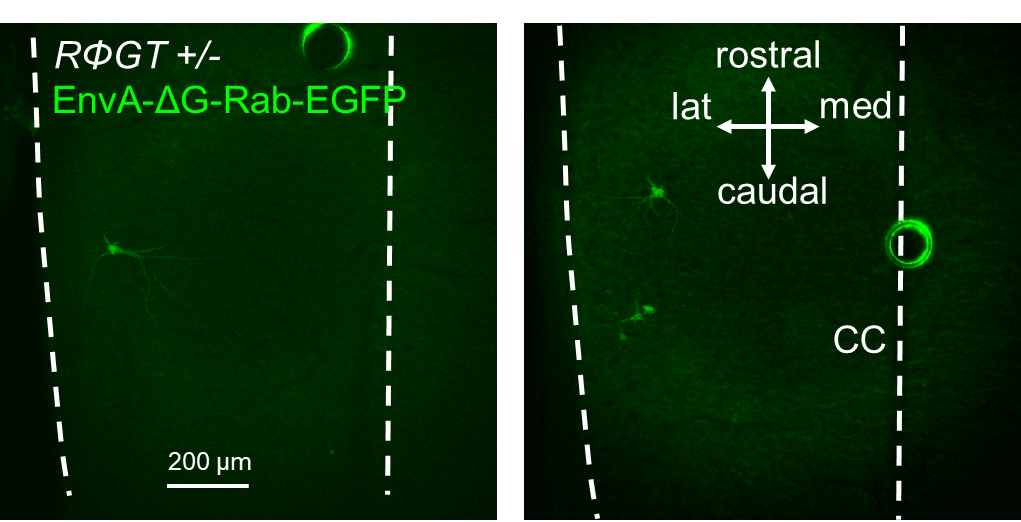

***Figure 13 figure supplement 1****: Two examples of a longitudinal section of two different spinal cords from a heterozygous RFGT mouse injected in the LG with EnvA-ΔG-Rab-EGFP, showing a small number of infected motor neurons, but no evidence of transsynaptic jumps, indicating ectopic expression of the TVA receptor, but not of the rabies glycoprotein.*

# Figure 13-figure supplement 2

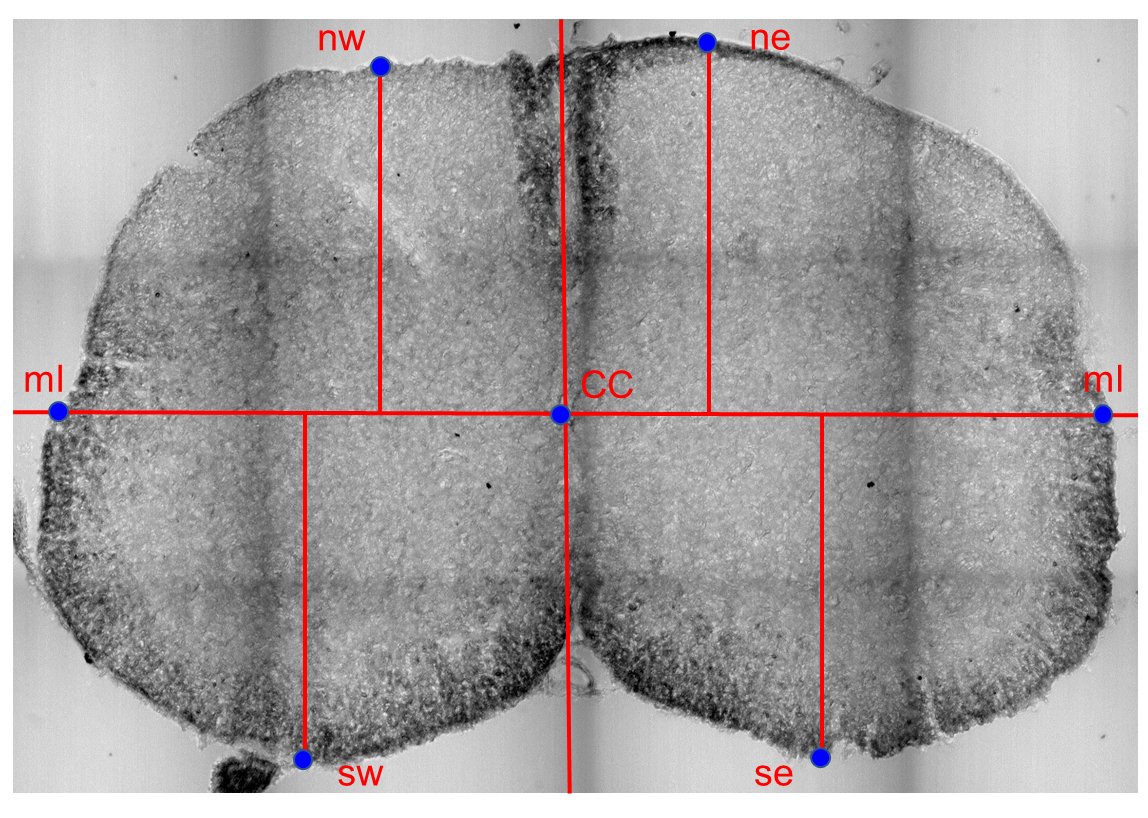

***Figure 13 figure supplement 2**** Schematic of a section of the spinal cord, indicating the reference points used for normalization. Each section was translated to have the origin of a Cartesian set of axes centered on the central canal (CC). A line passing through the central canal and perpendicular to the dorso-ventral axis was used to identify the edge of the white matter in the mediolateral direction (ml) and the ml-CC distance was used to normalize the x-coordinates. Along the dorso-ventral axes, the 4 edges of the white matter (ne, nw, se, sw) were identified and their distance from the horizontal line passing through the central canal were used to normalize the y-coordinates independently in each of the 4 quadrants.*